# Overview & Motivation

## Background

Your team is working on an autonomous quadcopter mission. As a lead software engineer, your current priority is to ensure that the mission mode logic is robust and is compliant with the DO-178C standard, which is a key requirement for airborne software in commercial aerospace systems. Your project centers around building and certifying a system where the quadcopter tracks a moving ball and operates across different flight modes including:

- Establish Communications (WaitForComms)

- Initialization (Init) 

- Calibration (Calibration)

- Ready for Flight (ReadyForTO)

- Tracking Altitude (TrackAlt)

- Tracking Altitude & Position (Track3D)

- Lost Ball (LostBall)

- Land (Land)

- Crash (Crash)

These operating modes are governed by detailed high-level requirements that specify entry criteria and state transitions. The requirements then need to be linked to the implementation artifacts which enables traceability and forms the basis for rigorous verification and validation tasks that are crucial for demonstrating compliance and functional coverage in model-based design workflows.

## Project Directory Structure

The project folder structure mirrors the DO-178C software lifecycle processes, organizing artifacts according to when they are produced and their role in the certification process. They are included here primarily for reference. The sequential numbering (01 through 06) reflects the typical progression through Stage of Involvement (SOI) reviews with certification authorities:

*DO_01_Planning* is a placeholder for the planning documents and standards required before any development begins. This includes the Plan for Software Aspects of Certification (PSAC), Software Development Plan (SDP), Software Verification Plan (SVP), Software Configuration Management Plan (SCMP), and Software Quality Assurance Plan (SQAP).

*DO_02_Requirements* houses the software requirements data, including both high-level requirements (HLR) derived from system requirements and potentially low-level requirements (LLR) depending on the model usage approach. This folder maintains requirements specifications, derived requirements, and requirements traceability data that links back to system-level requirements. For model-based development, this may include textual requirements that will be implemented in design models.

*DO_03_Design* contains the design artifacts including software architecture, design models, and associated test cases. In a model-based workflow, this folder houses Simulink models representing the software design and low-level requirements, along with test harnesses and model-level verification test cases. The co-location of design models with their test cases facilitates early verification through desktop simulation before code generation.

*DO_04_Code* is a placeholder for the source code artifacts, which in a model-based development workflow includes automatically generated code from Simulink models along with any hand-written code. This folder maintains the implementation-level artifacts including source code, parameter data files, and potentially the executable object code. The code is directly traceable to the low-level requirements or design models from DO_03_Design.

*DO_05_Artifacts* contains the verification evidence and certification data required to demonstrate compliance. This includes verification results, test procedures and results, coverage analysis reports (statement, decision, MC/DC as applicable to the DAL), traceability reports, problem reports, and reviews records. These artifacts provide the objective evidence that all DO-178C objectives have been satisfied.

*DO_06_ToolQualification* typically contains the tool qualification data required per DO-330 for any software tools whose output is part of the certification package without independent verification. This includes tool qualification plans, tool operational requirements (TORs), tool verification cases and procedures, and tool verification results. MathWorks provides the DO Qualification Kit with pre-built artifacts that can be tailored for project-specific use.

In this example, we will be using the following MathWorks products:

[**Simulink Check™**](https://www.mathworks.com/products/simulink-check.html) to analyze your models, requirements, and tests to assess design quality and compliance with standards

[**Simulink Design Verifier™**](https://www.mathworks.com/products/simulink-design-verifier.html) to check for dead logic and run-time errors

[**Requirements Toolbox™**](https://www.mathworks.com/products/requirements-toolbox.html) to manage requirements in the Simulink environment

[**Simulink® Test™**](https://www.mathworks.com/products/simulink-test.html) to develop, manage, and execute simulation-based tests

[**Simulink® Coverage™**](https://www.mathworks.com/products/simulink-coverage.html) to measure model test completeness

[](https://www.mathworks.com/products/simulink-design-verifier.html)

This example assumes that you have a basic knowledge of [**Simulink®**](https://www.mathworks.com/products/simulink.html) and [**Stateflow®**](https://www.mathworks.com/products/stateflow.html). You do not need to be familiar with DO-178C, and the workflows described are best practices which can be used to comply with similar standards.

### A Quick Note on File Permissions

Many MATLAB® users work in directories which are automatically synchronized with tools such as OneDrive. This can cause write permissions issues when creating test harnesses and other artifacts.

Here are a few options to consider before proceeding. Note that you will likely not need to do all of these.

- Use a working directory which is not automatically synchronized (best practice)

- Run MATLAB as Administrator

- If necessary, set directory permissions programmatically (see example code below)

currentProject = matlab.project.currentProject;
projectRoot = currentProject.RootFolder;
HLRTestDir = fullfile(projectRoot,"DO_03_Design","ModeLogic","test_cases","HLR");
perms = filePermissions(HLRTestDir);
try
    setPermissions(perms,"Writable",true);
catch
    try
        setPermissions(perms,"UserWrite",true,"GroupWrite",true,"OtherWrite",true);
    catch ME
        error("Could not change permissions: %s", ME.message);
    end
end

# Part 1: Check Model Compliance

The goal for this part is to check the model against standards for high-integrity systems.

**Simulink Check™** provides a mechanism to check a model for its conformance to standards, its accuracy and consistency, its verifiability, and other characteristics.

**Simulink Design Verifier™** provides the capability to check a model for the following potential design errors using formal methods:

- Dead logic

- Integer overflow

- Division by zero

- Violation of specified intermediate minimum and maximum values

- Out of bound array access

You can run checks from both Simulink Check™ and Simulink Design Verifier™ via Model Advisor.

For this part, we will use a subset of Model Advisor checks, which includes [checks for High-Integrity Systems](https://www.mathworks.com/help/simulink/high-integrity-systems.html) as well as specific checks for library links, model referencing, and requirements consistency. The subset is included in a Model Advisor configuration set stored in **modelAdvisorQualifiableChecks.json**. You can view the list of checks using the Configuration Editor.

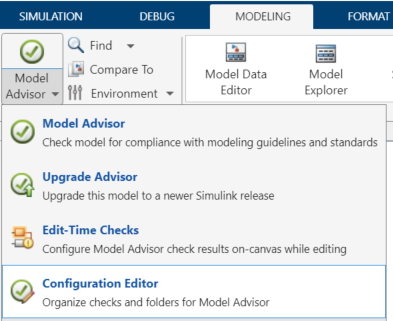

We can run these checks using the [ModelAdvisor.run() function](http://modeladvisor.run()%20functionhttps//www.mathworks.com/help/slcheck/ref/modeladvisor.run.html) and view the Model Advisor report.

load_system("ModeLogic");
modelAdvisorHIResults = ModelAdvisor.run("ModeLogic",Configuration="modelAdvisorQualifiableChecks.json");
viewReport(modelAdvisorHIResults{1});
bdclose all

### A Quick Note On Qualifying Model Advisor Checks

The [DO Qualification Kit™](https://www.mathworks.com/products/do-178.html) provides tool qualification support for a subset of Model Advisor checks (e.g., checks for High-Integrity Systems). Most teams will run additional Model Advisor checks, such as those which verify internal modeling standards are being met or to check for any potential downstream issues (e.g., incompatibility with Simulink® Code Inspector™). Though we will not cover tool qualification in this workshop, it is important to note that these checks should be qualified. Make sure you account for this during program planning (e.g., Tool Operational Requirements and Tool Qualification Plan). Reach out to your contact in MathWorks Sales for help. You can also refer to [our documentation](https://www.mathworks.com/help/qualkitdo/tool-qualification.html) for more information on tool qualification.

### Bonus Task

Try running the Model Advisor checks as configured in [modelAdvisorSLCIChecks.json](matlab:open('.\tools\modelchecks\modelAdvisorSLCIChecks.json')) using ModelAdvisor.run().

# Part 2: Create Test Case and Link to Requirements

The goals for this part are:

- Create test harness for your algorithm (component under test)

- Create test sequence to verify the control of landing sequence

- Link test case to requirements

- Execute the test case to see pass/fail results

Here are the products we will use:

**Requirements Toolbox™ **is used to view and author requirements within MATLAB® and Simulink®, as well as to establish traceability between requirements, Simulink® models, MATLAB® code, and test cases to understand the impact of a change in requirements.

**Simulink® Test™** is used to create, manage, and execute test cases for simulation-based testing in Simulink®. You can use Simulink® Test™ to create test harnesses, create test vectors using a variety of methods such as a test sequence, create test assessments to determine pass/fail criteria, and link test cases to requirements.

We will use other features of Simulink® Test™ in Part 3 of the workflow.

**Note on Independence****: **Most standards (e.g., DO-178C) require independence between design and verification activities. In other words, "you should not test your own design." We recommend you follow this best practice in your own teams. The rest of this workshop will cover verification workflows.

## Step 1: View Requirements to Verify 

**Requirements Toolbox™ ** includes the Requirements Editor, which is a stand-alone tool (separate from a model) which can be used to import, author, and manage requirements as well as manage requirements traceability. Requirements can be imported from tools such as Microsoft Word, Microsoft Excel, IBM Rational DOORS, ReqIF files, and more.

In this part of the example, we will be working with requirements that have already been imported into Requirements Toolbox™.

Requirements are stored as "requirements sets", which have a file extension of **.slreqx**.

Requirements links are stored as "link sets", which have a file extension of **.slmx**.

To open the mission mode logic requirements in the Requirements Editor, run the following code (click **Run Section** in the Live Editor toolstrip or type **CTRL + Enter**):

slreq.open('HLR_ModeLogic');

For this exercise, we will focus on these following requirements for landing sequence:

*Requirement 9.1** Enter Land from Lost Ball: The Land mode shall be entered from the Lost Ball mode when the quadcopter has been in Lost Ball mode for 3 seconds. *

*Requirement 9.2** Enter Land from Track Altitude: The Land mode shall be entered from the Track Altitude mode when commanded by the ground station or if the battery voltage goes below 3.0 volts.*

*Requirement 9.3** Enter Land from Track Altitude and Position: The Land mode shall be entered from the Track Altitude and Position mode when commanded by the ground station or if the battery voltage goes below 3 volts.*

You can use the following commands to open the Requirements Editor directly to these requirements.

reqSetName = "HLR_ModeLogic.slreqx";
reqSet = slreq.open(reqSetName);
landingReqs = find(reqSet,"Type","Requirement", ...
"Summary","~Enter Land"); % Finds three requirements
rmi.navigate('linktype_rmi_slreq', reqSetName, num2str(landingReqs(1).SID)); % Navigate to first requirement

Beginning in R2026a, you can navigate directly to a specific requirement in the Requirements Editor using **slreq.open()**

if ~isMATLABReleaseOlderThan("R2026a")
    slreq.open(reqSet,landingReqs(1).Id);
else
    warning("Your current MATLAB release is " + matlabRelease.Release)
end

To learn more about how to programmatically work with requirements, please refer to [the documentation](https://www.mathworks.com/help/slrequirements/referencelist.html).

## Step 2: Create a Test Harness

Test harnesses are independent Simulink® models used to isolate the component under test to verify design models without modifying the design itself. With Simulink® Test™, you can create test harnesses which are automatically associated with a design model. A design model can have several test harnesses.

For this example, we will save the test harness externally from the design model as a separate file. This is done in order to keep track of the testing files separately from the design files. 

Here are the steps to take:

1) Open the Mode Logic ("ModeLogic") model by running the following code (click **Run Section** in the Live Editor toolstrip or type **CTRL + Enter**):

open_system('ModeLogic');

2) Open the Simulink® Test™ app via the Simulink® Toolstrip. The Simulink® Test™ app is available under the APPS tab.

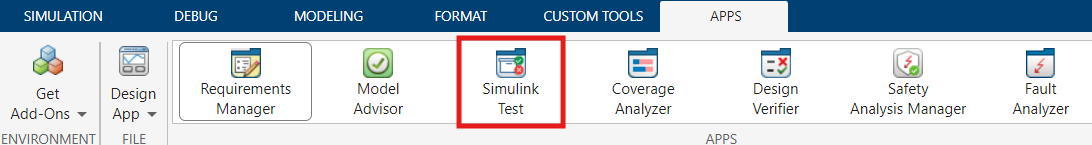

3) Click on the **Add Test Harness **button in the Simulink® Test™ app toolstrip. Make sure "ModeLogic" is shown in the text area for "Create Test Harness for". 

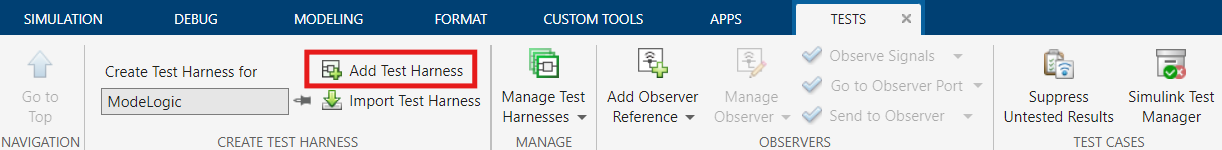

This will open the **Create Test Harness** dialog.

4) Name the harness **"ModeLogic_Harness" **and save the harness in the **DO_03_Design/ModeLogic/test_cases/HLR** directory.

5) Under Sources and Sinks, click on the input dropdown ("Inport" should be selected by default), and select **Test Sequence**. For more information on other options for Sources, please refer to the [Simulink Test Inputs documentation](https://www.mathworks.com/help/sltest/inputs.html).

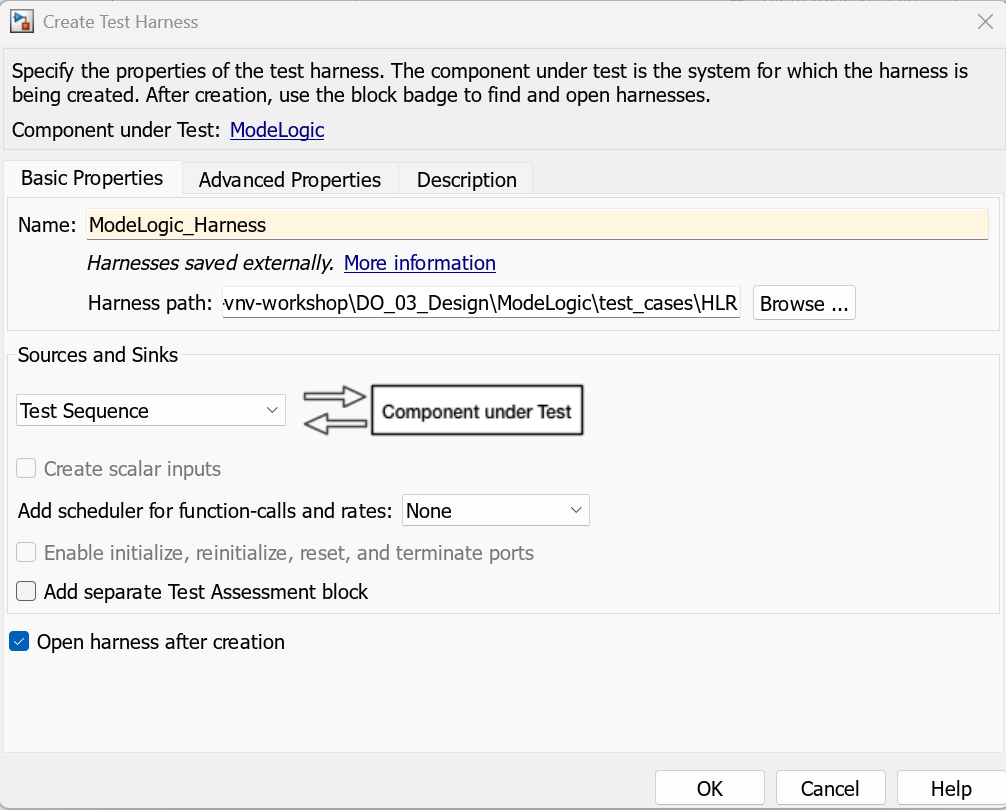

6) Make sure "Open harness after creation" is selected.

7) In the **Advanced Properties** tab, select "Log output signals".

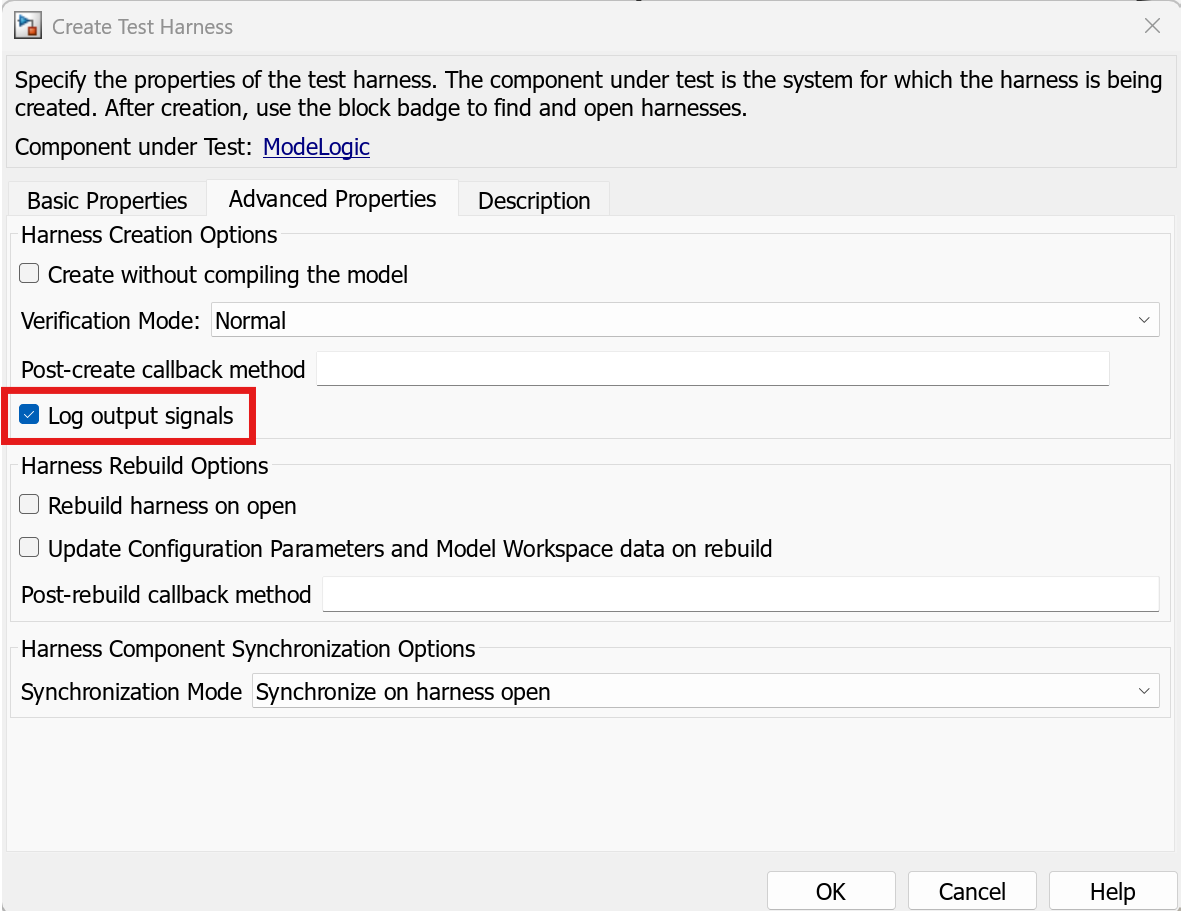

8) Click OK.

Note: if you are running into issues with directory write permissions, see the section "A Quick Note on File Permissions" above.

## Step 3: Author a Test Harness using a Test Sequence

Now, let's simulate and validate the correct operation and transitions of the quadcopter's mission mode through an automated test sequence. For this exercise, we will first focus on: 

*Requirement 9.1** Enter Land from Lost Ball: The Land mode shall be entered from the Lost Ball mode when the quadcopter has been in Lost Ball mode for 3 seconds. *

This test sequence will step through the mission phases:

- Initializing system variables (i.e. GCS commands, quadcopter states etc.) 

- Checking communication links

- Issue calibration commands

- Simulating ball detection/loss

- Verifying mode transitions to "Land"

A Test Sequence is a type of test input block available with Simulink® Test™. It allows you to write tests that follow a given set of steps that do not have to be time-based. For example, you can transition between test steps based on the value of an input signal. Both the test inputs and the pass/fail criteria can be defined in a Test Sequence block. One advantage of a Test Sequence over time-series based test vectors is that Test Sequences can be easier to maintain and understand since they are based on response to simulation. For more information on Test Sequences, please refer to the [Test Sequence Editor documentation](https://www.mathworks.com/help/sltest/ug/test-sequence-editor.html).

1) Open the Test Sequence Editor by double-clicking on the Test Sequence block in **ModeLogic_Harness.slx. **

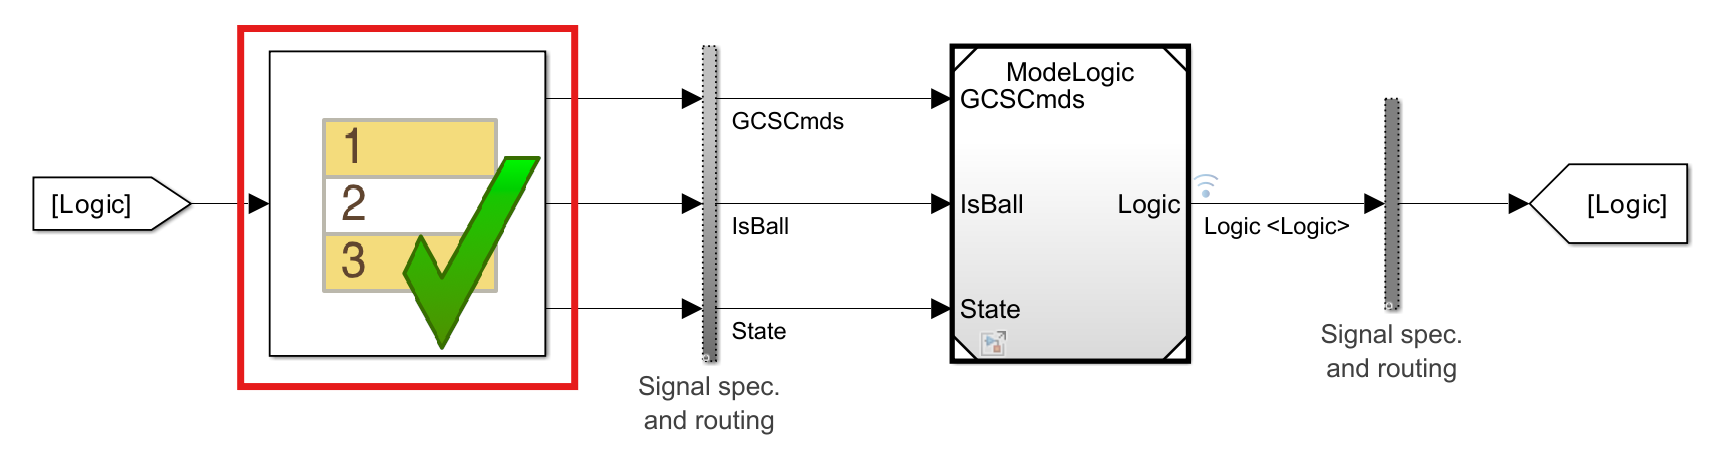

Notes that the first step in the Test Sequence is automatically created. It initializes the variables to zero. Change battery volts initial condition to 3.3V.

2) Next, add a new step to the Test Sequence 

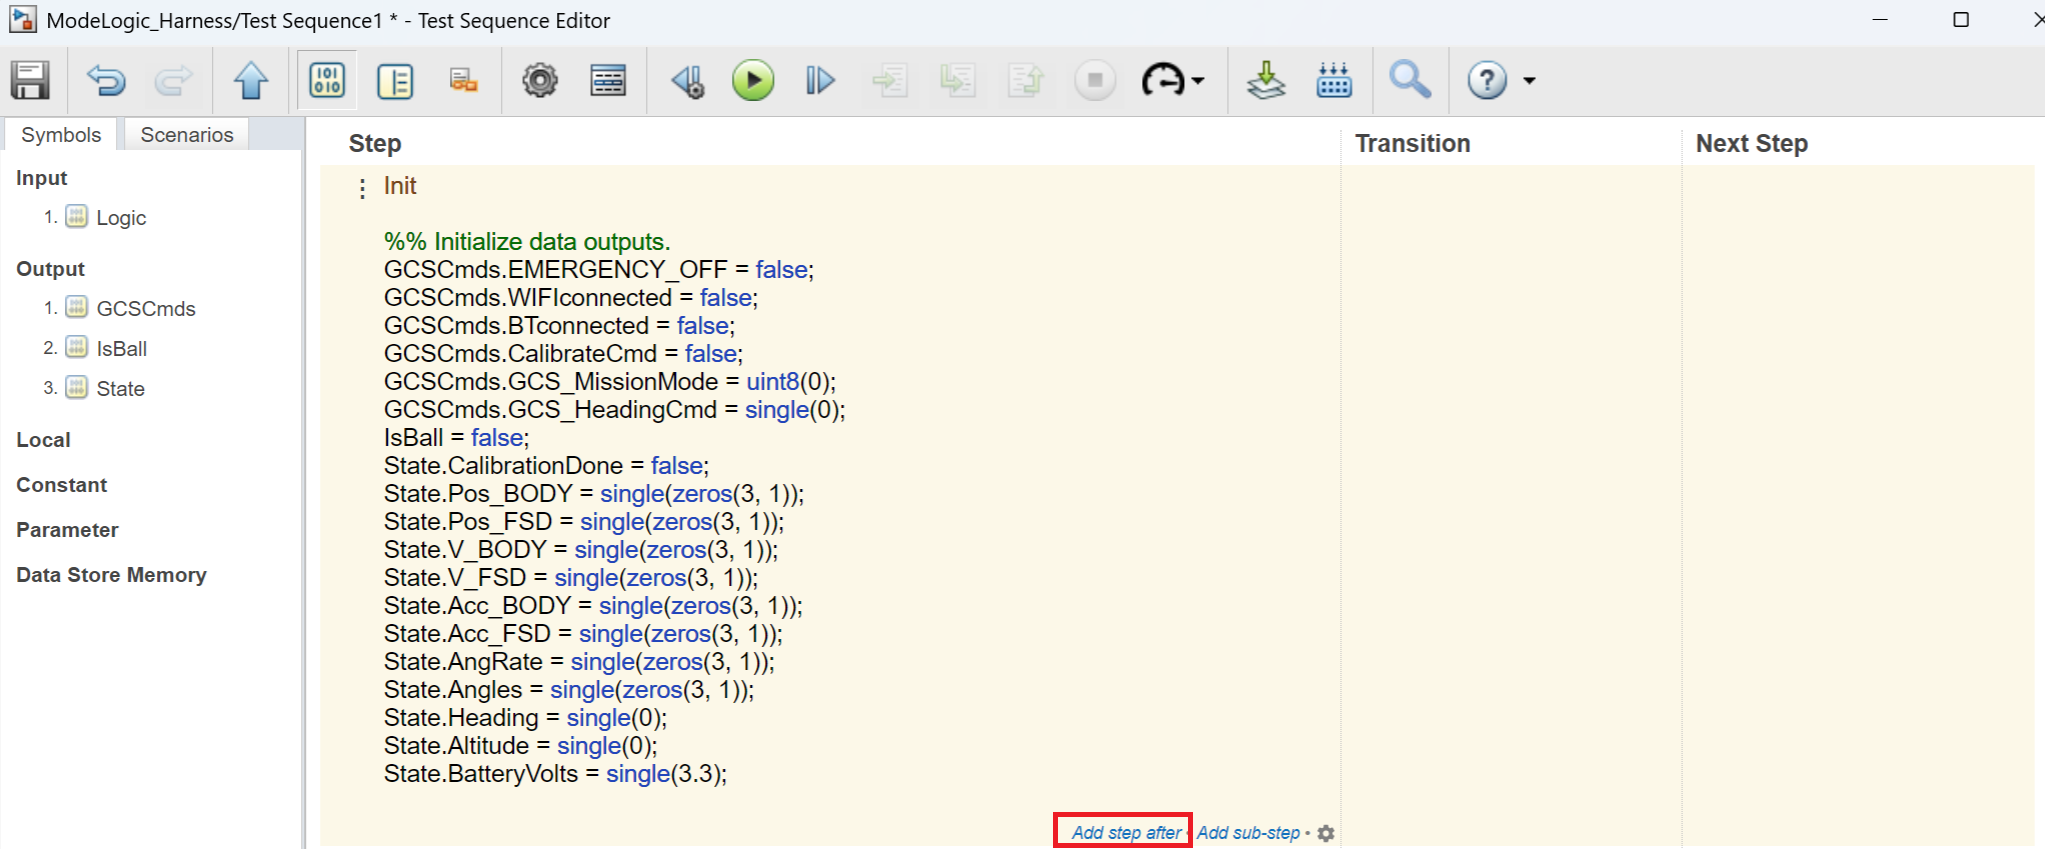

3) Create a new step called "Wifi_andBT_on" to establish Wifi and Bluetooth communication connection. Can you figure out what parameters to set in this step? (Hint: we will be using these parameters: "GCSCmds.WIFIconnected" and "GCSCmds.BTconnected").

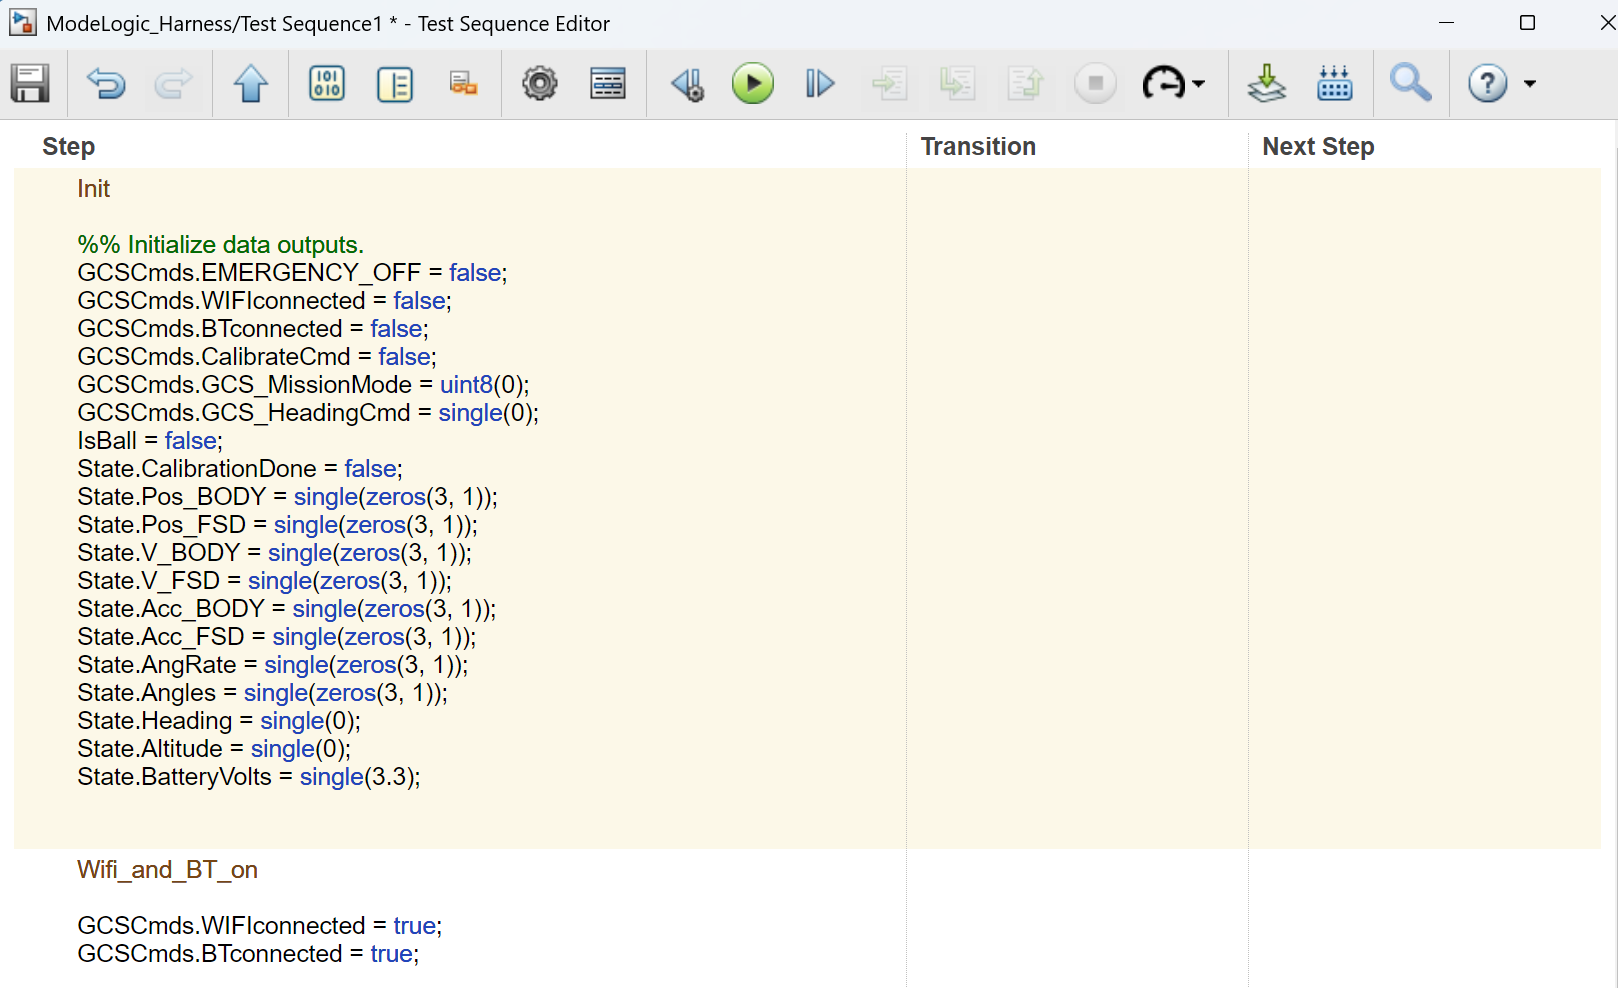

4) Next, we will define the transition between the "Init" step and the "Wifi_andBT_on" step by hovering over the bottom of the Transition cell for step "Init" and click "Add transition". 

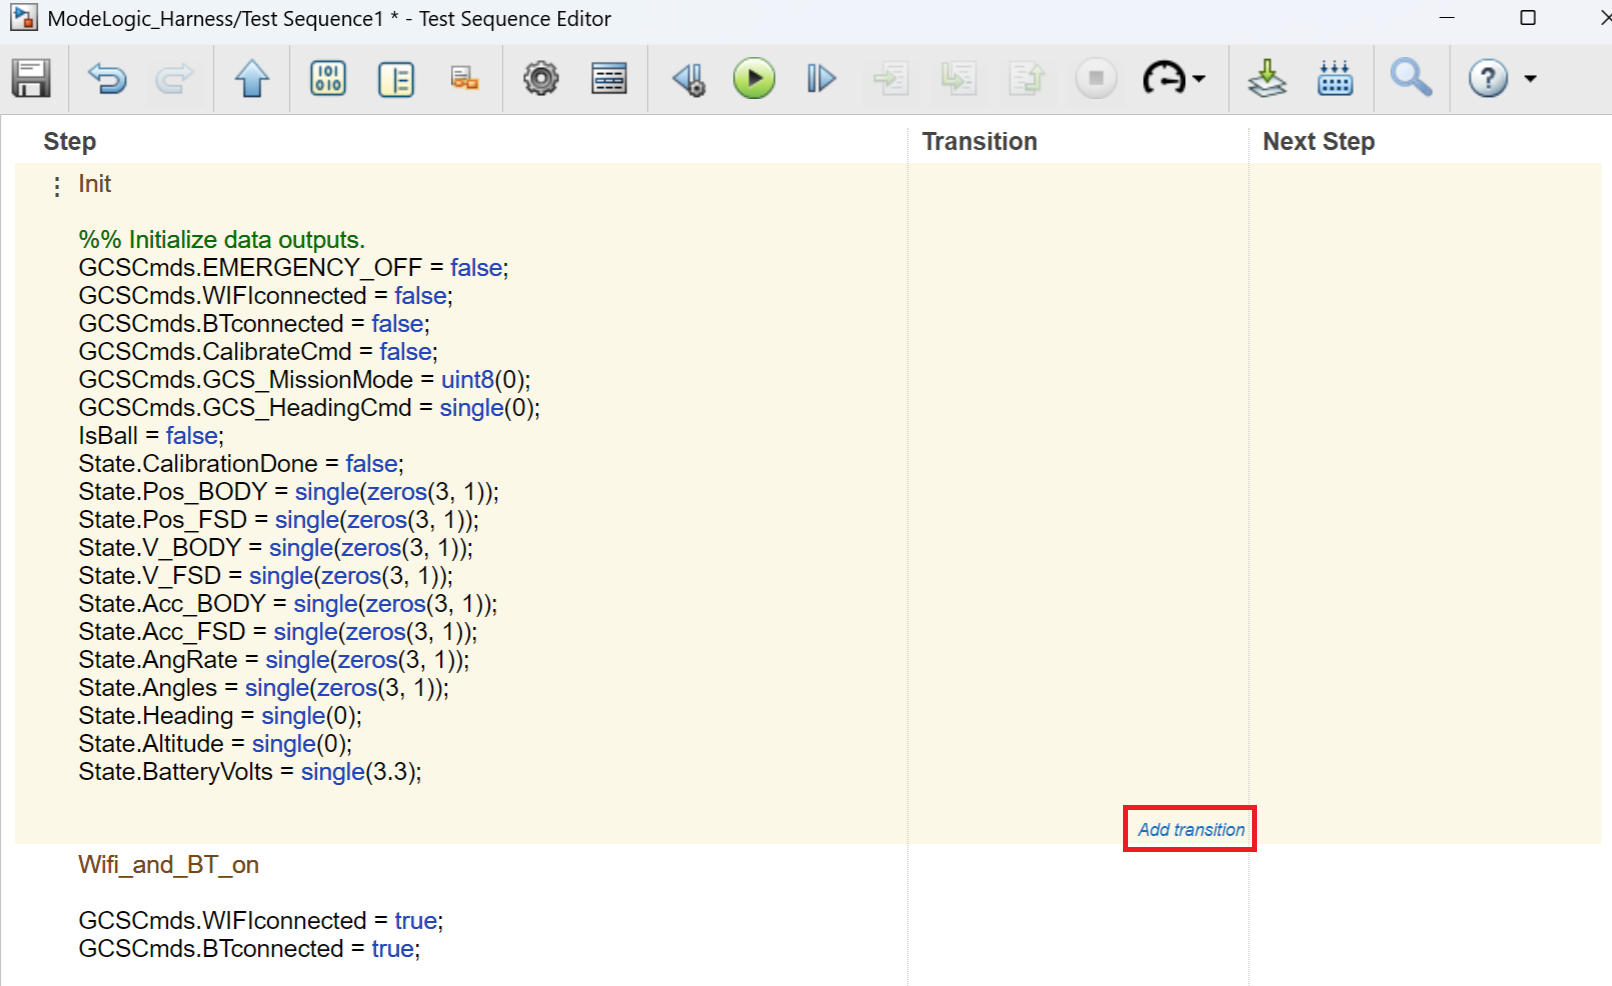

5) We will transition to "Wifi_andBT_on" after 1 time step. This can be achieved using the ["after"](https://www.mathworks.com/help/stateflow/ref/after.html) function. 

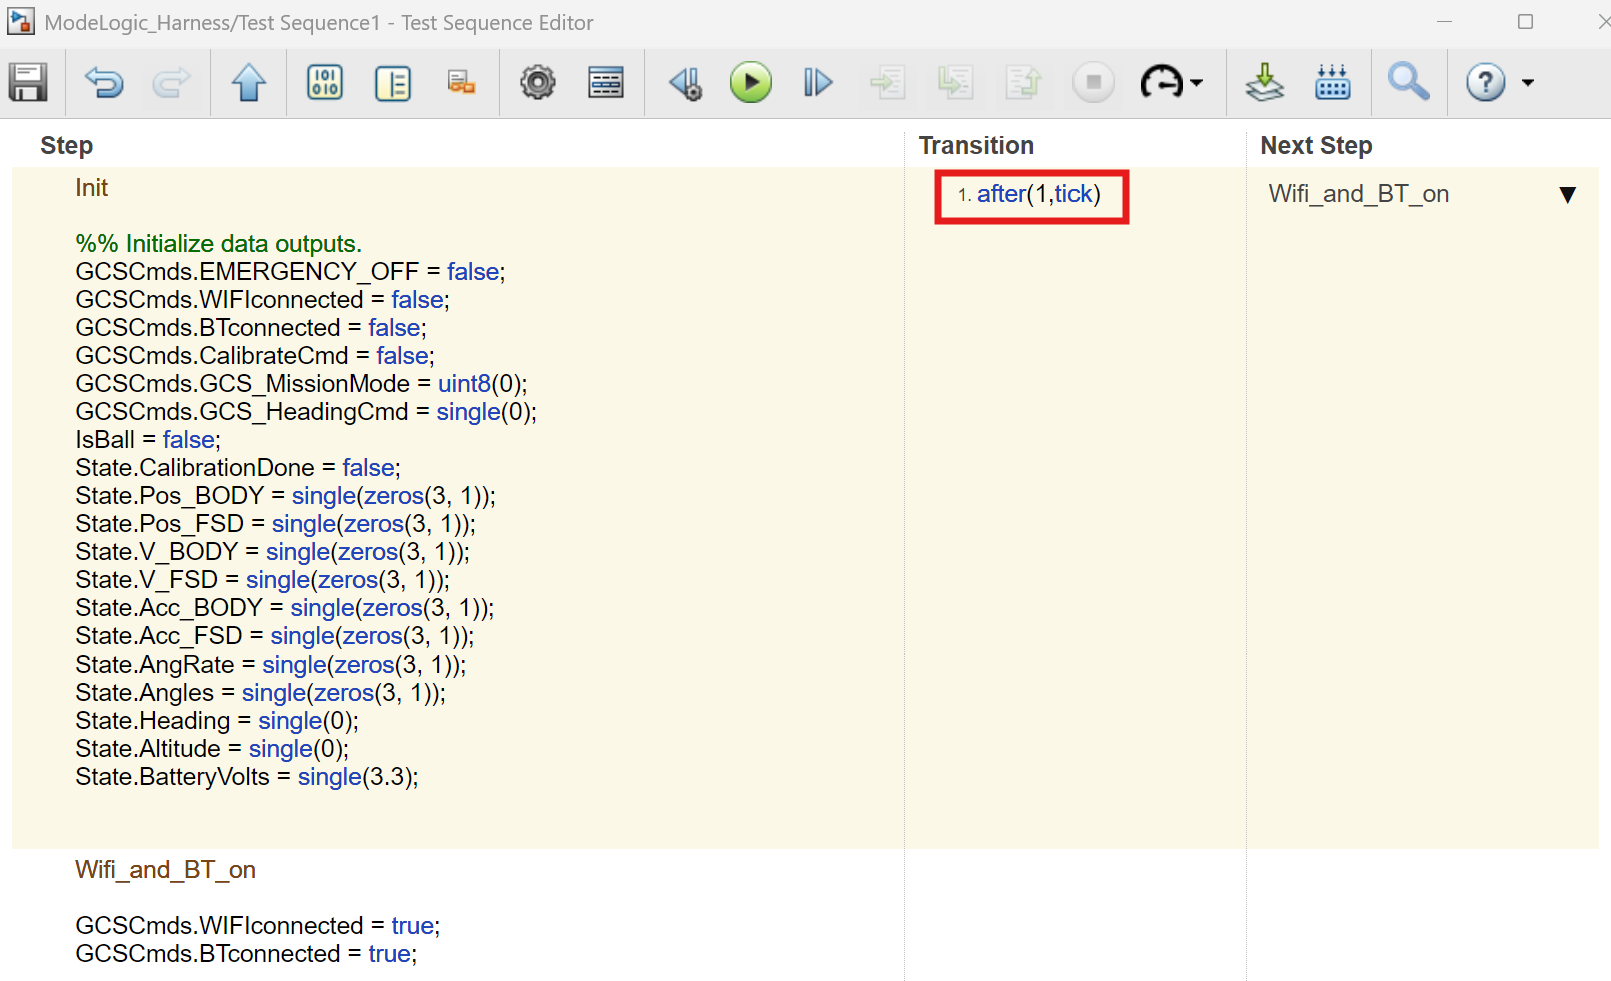

6) Now following the same steps, add the following transitions sequentially to simulate a lost ball scenario:

- 1 time step after communication has been established, start calibration

                Set GCSCmds.CalibrateCmd = true;

- 1 time step after calibration starts, calibration is done, set mission mode to 1

                Set State.CalibrationDone = true;

                Set GCSCmds.GCSMissionMode = 1;

- 1 time step after calibration is done, we detect the ball

                Set IsBall = true;

- 1 time step after detection of the ball, we lost it

                Set IsBall = false;

After adding these steps and transitions, the test sequence should look similar to this: 

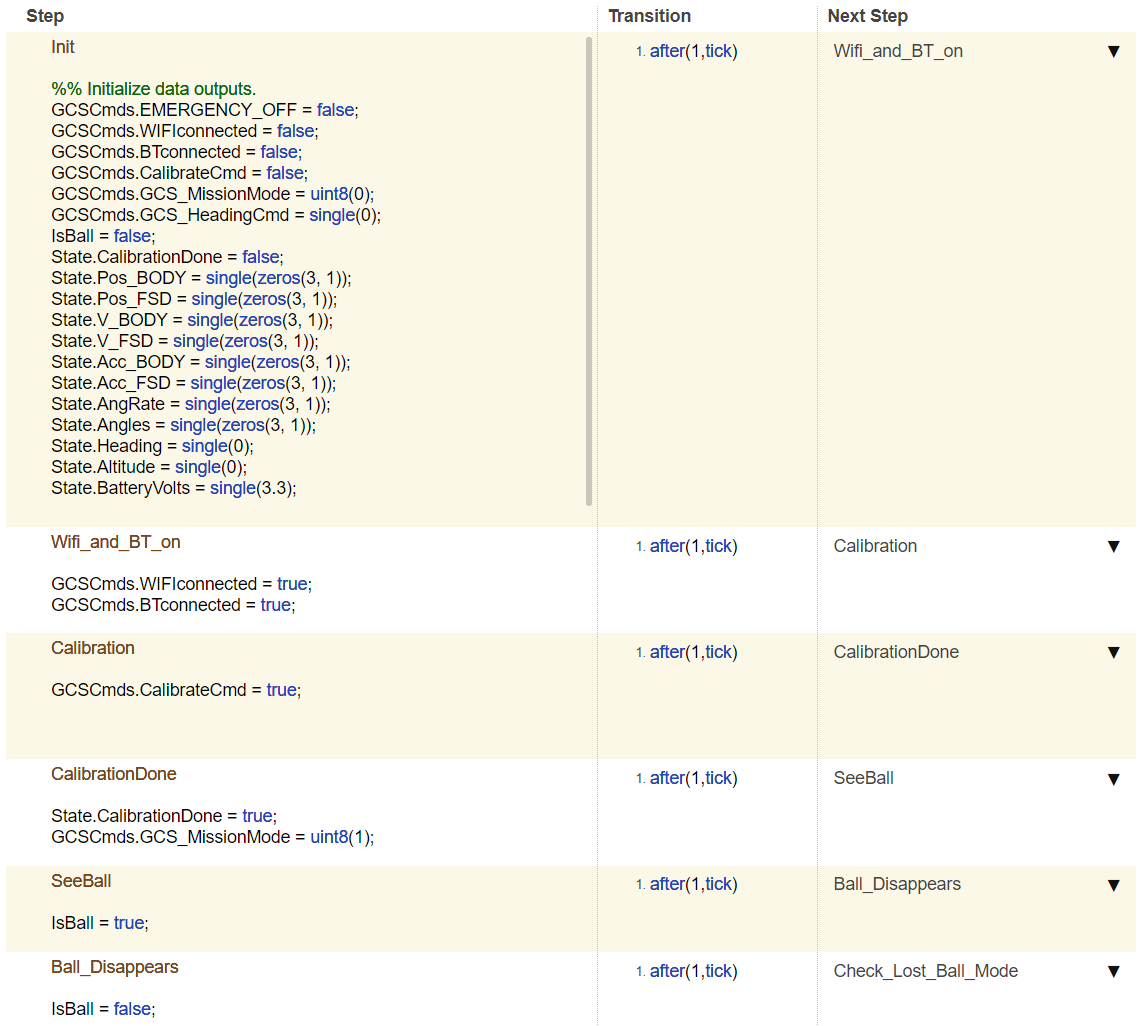

7) Now let's verify the requirement: 

*Requirement 9.1** Enter Land from Lost Ball: The Land mode shall be entered from the Lost Ball mode when the quadcopter has been in Lost Ball mode for 3 seconds. *

To do this, we will be using the ["verify"](https://www.mathworks.com/help/sltest/ref/verify.html) statement. Upon confirming the ball is lost, we shall land the quadcopter after 3 seconds:

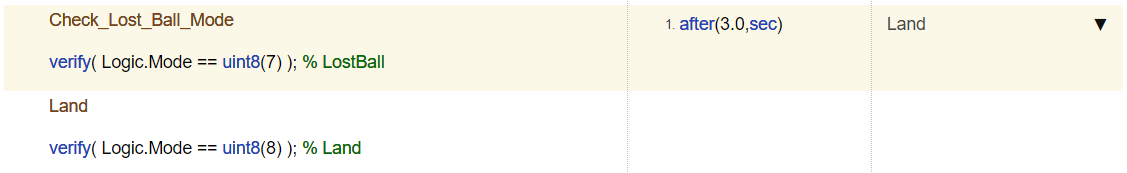

8) Upon entering landing model, we will terminate the simulation and finish this test case simulation. To do this, we will first add an output to signal when to stop the simulation. Make sure to set the data type to boolean.

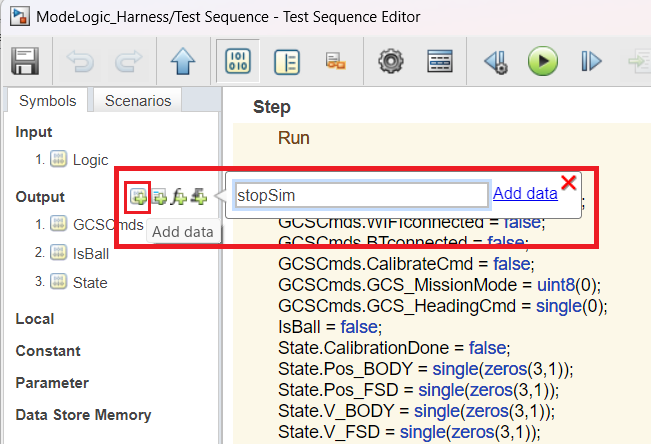

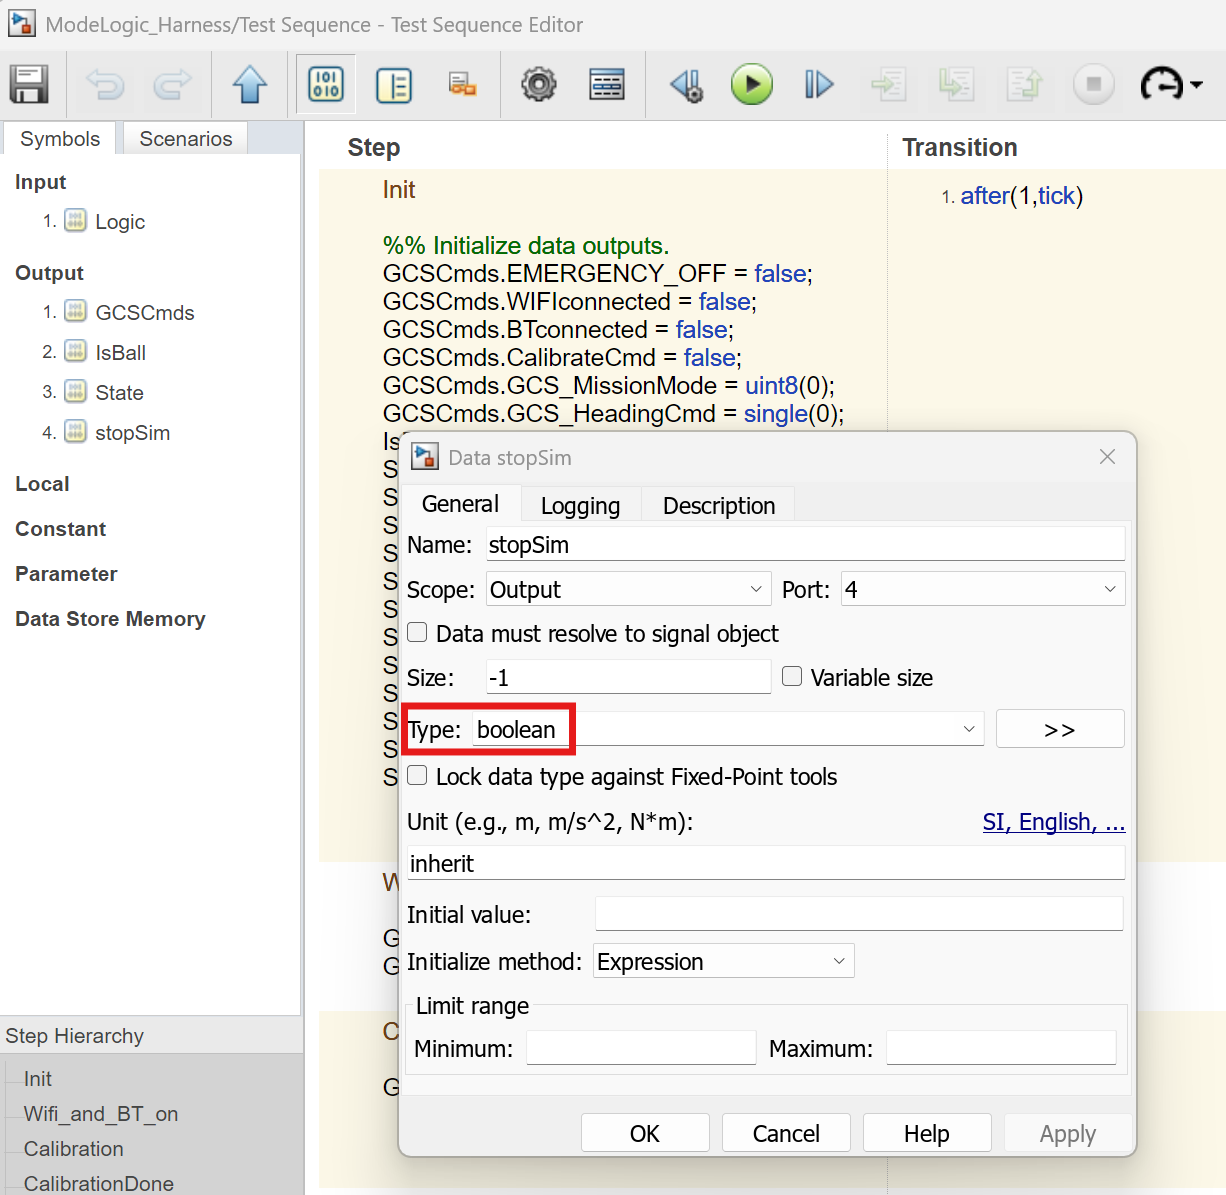

9) At the end of the final step "Land", set stopSim to true;

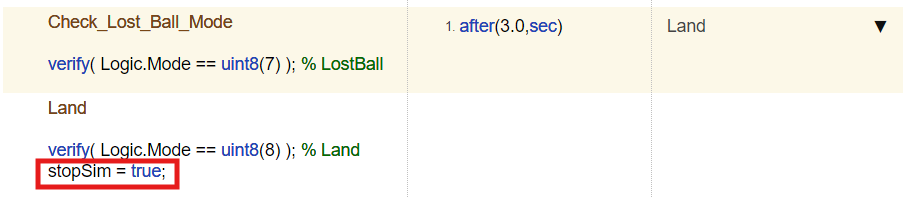

10) Save and close the Test Sequence block

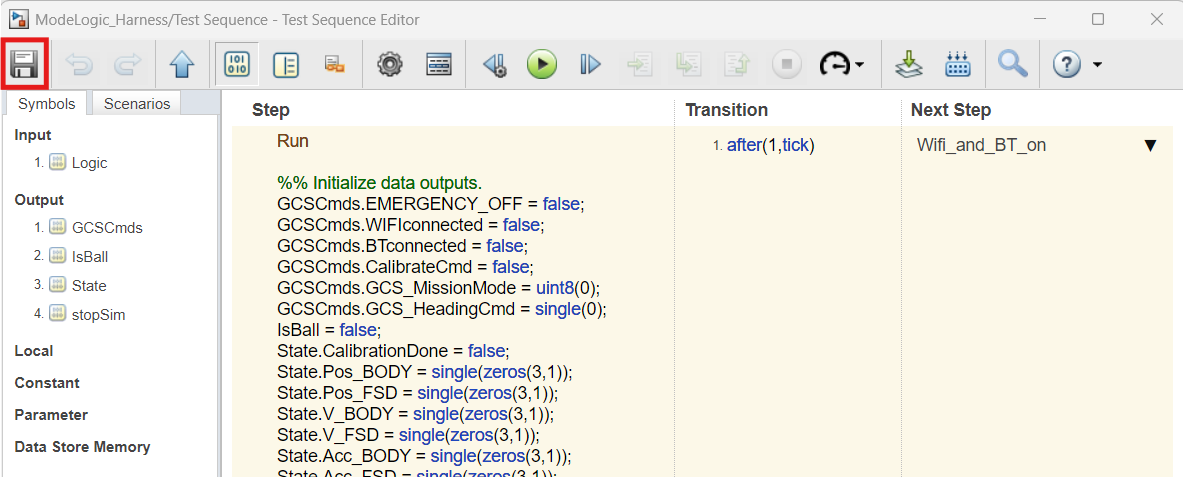

11) Step out to the test harness model and connect the added "stopSim" output to a ["Stop Simulation"](https://www.mathworks.com/help/simulink/slref/stopsimulation.html) block. Then save the model. 

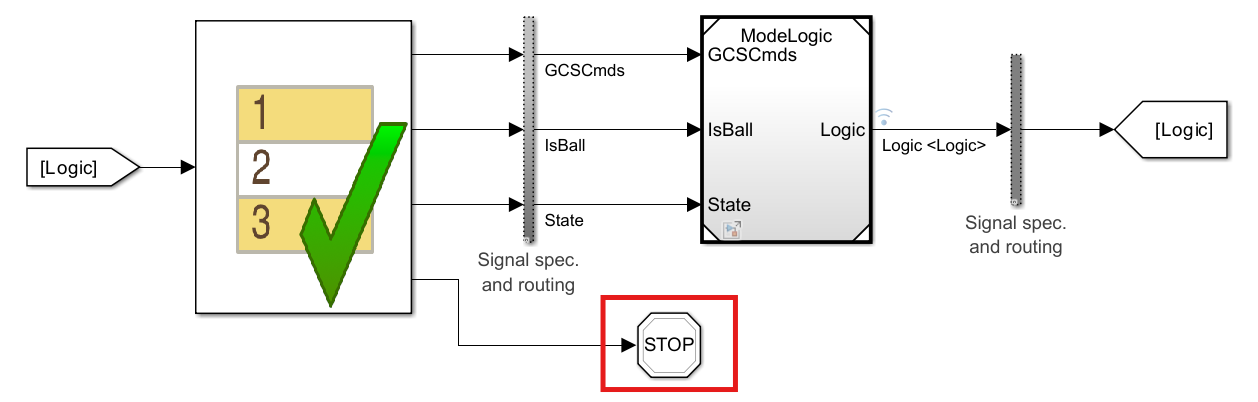

Congratulations! You have just created a Test Harness. For more information, check out [Test Harnesses](https://www.mathworks.com/help/sltest/test-harnesses.html).

12) Test harnesses are executable just like any other Simulink model. Let's simulate the test harness model we just created and look at the results. Run the simulation and open up Simulink Data Inspector, see how the flight mode changes throughout the simulation as it proceeds down the test sequence we just designed and inspect the landing mode entry assessment at the end of the simulation.

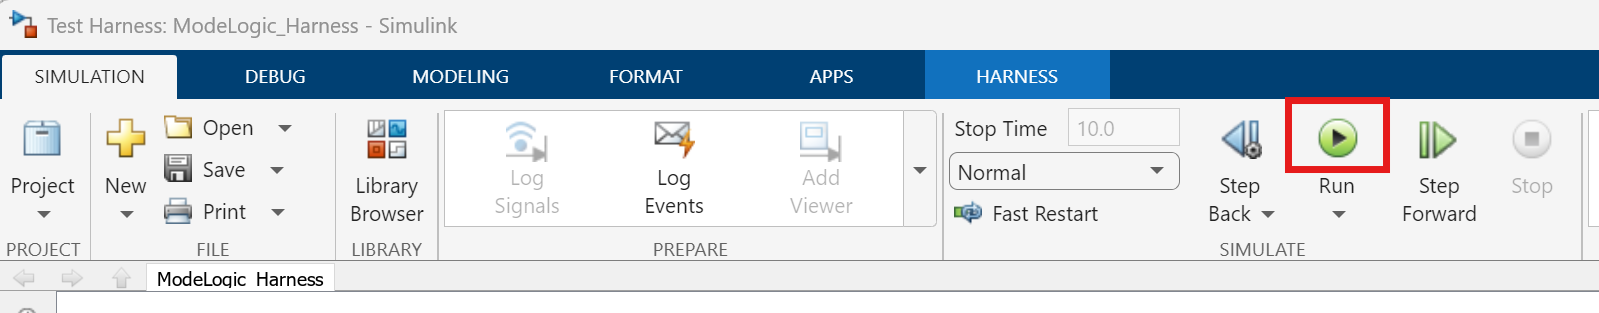

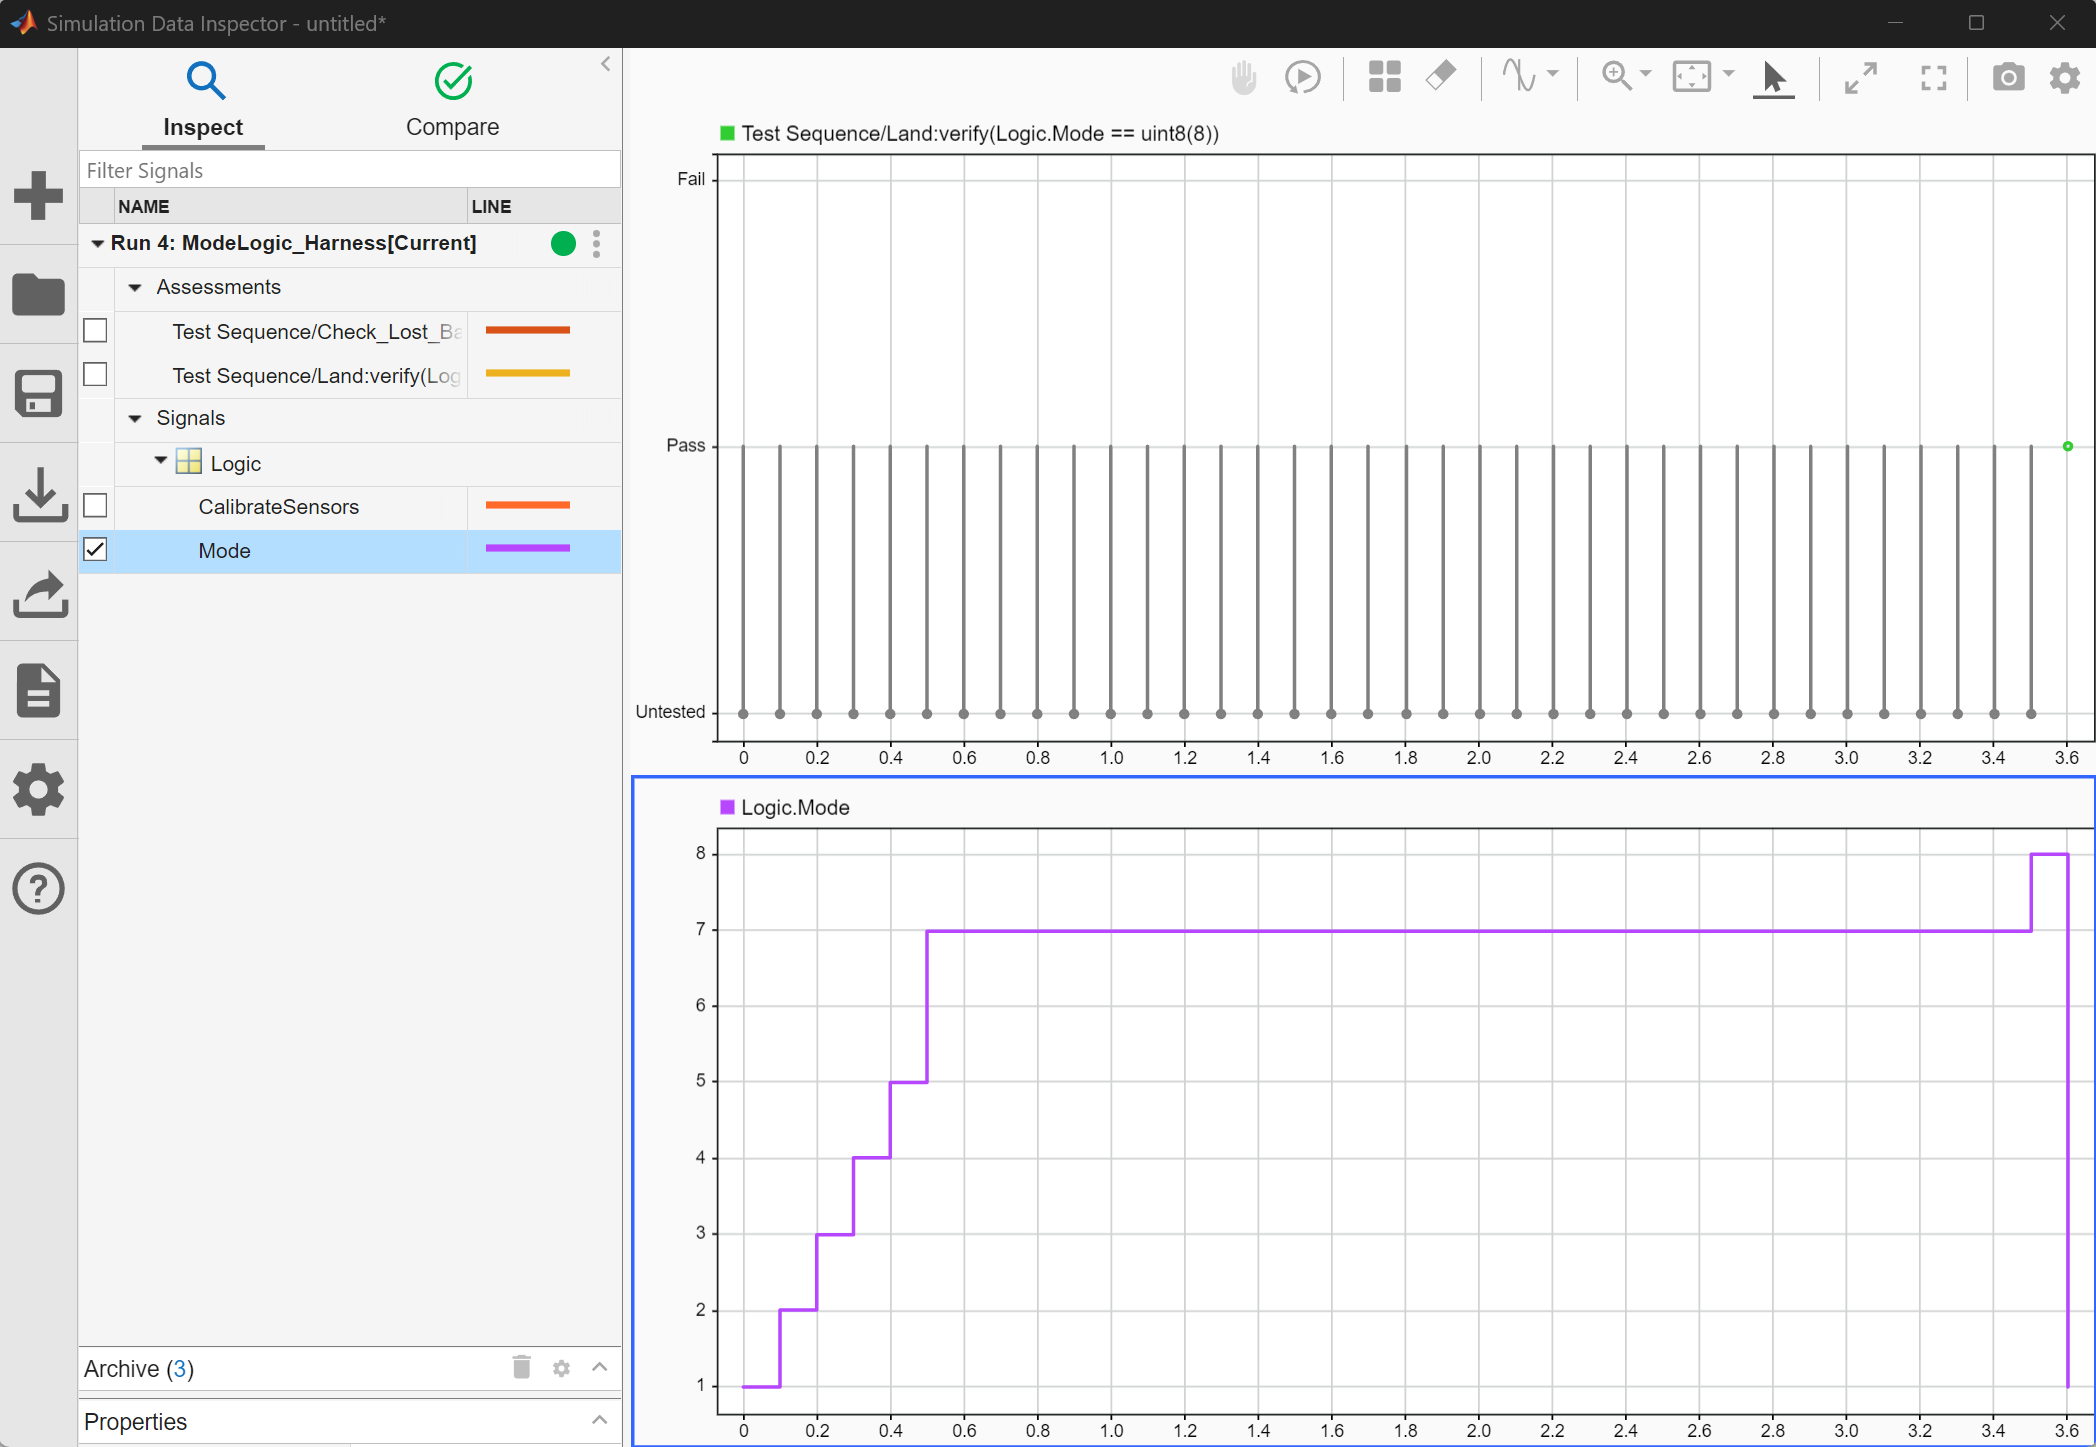

### Bonus Task

Can you modify the Test Sequence for the other two landing sequence requirements?

*Requirement 9.2** Enter Land from Track Altitude: The Land mode shall be entered from the Track Altitude mode when commanded by the ground station or if the battery voltage goes below 3.0 volts.*

*Requirement 9.3** Enter Land from Track Altitude and Position: The Land mode shall be entered from the Track Altitude and Position mode when commanded by the ground station or if the battery voltage goes below 3 volts.*

## Step 4: Create a Test Case Using the Test Manager in Simulink® Test™

Simulink® Test™ includes the Test Manager, which you can use to create and manage test cases. A test case is a part of a test suite, which is a part of a test file. In this step, we will create a test case that will verify whether the model has correctly implemented the requirements. 

Here are the steps to take:

1) Open the Test Manager

Go to "ModeLogic.slx" and open the Simulink Test app from the Apps toolstrip on the top. Then click on "Simulink Test Manager" on the right.

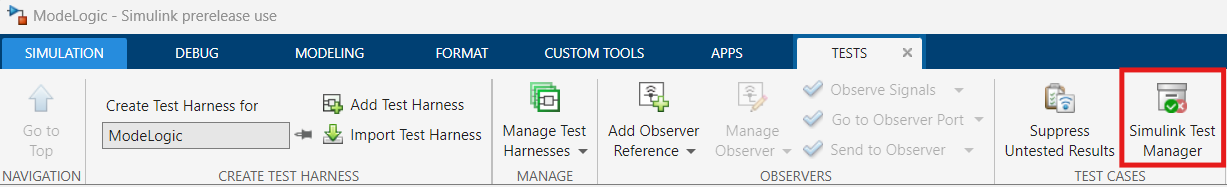

You can also open the Test Manager by running the following command:

sltestmgr

2) Create a new test file from the "ModeLogic.slx" model. In the Test Manager, click New->Test File From Model.

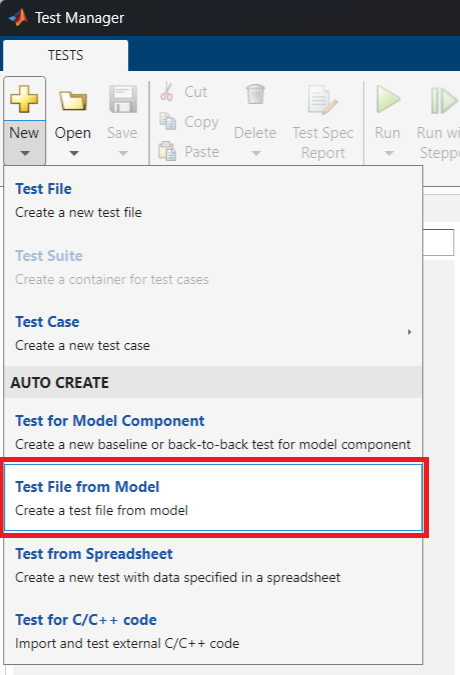

3) In the New Test File window, click the label on the right to select current model - "Use Current Model". You will then see "ModeLogic" pop up. Set the Test Type to "Simulation". In the location field, name the test file "ModeLogicTest.mldatx" and save it to a test folder. 

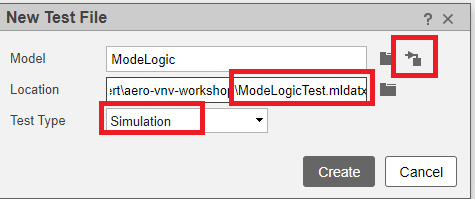

There are three types of tests: Baseline, Equivalence and Simulation. You can find more information from [Test Types](https://www.mathworks.com/help/slcheck/ref/testcasetype.html).

4) Click "Create". You will then see the test file show up in Test Browser on the left side. A test case will be automatically created using the "ModeLogic_Harness.slx" we created earlier. If you have created other test harnesses for the ModeLogic.slx model, they will also show up in the list.

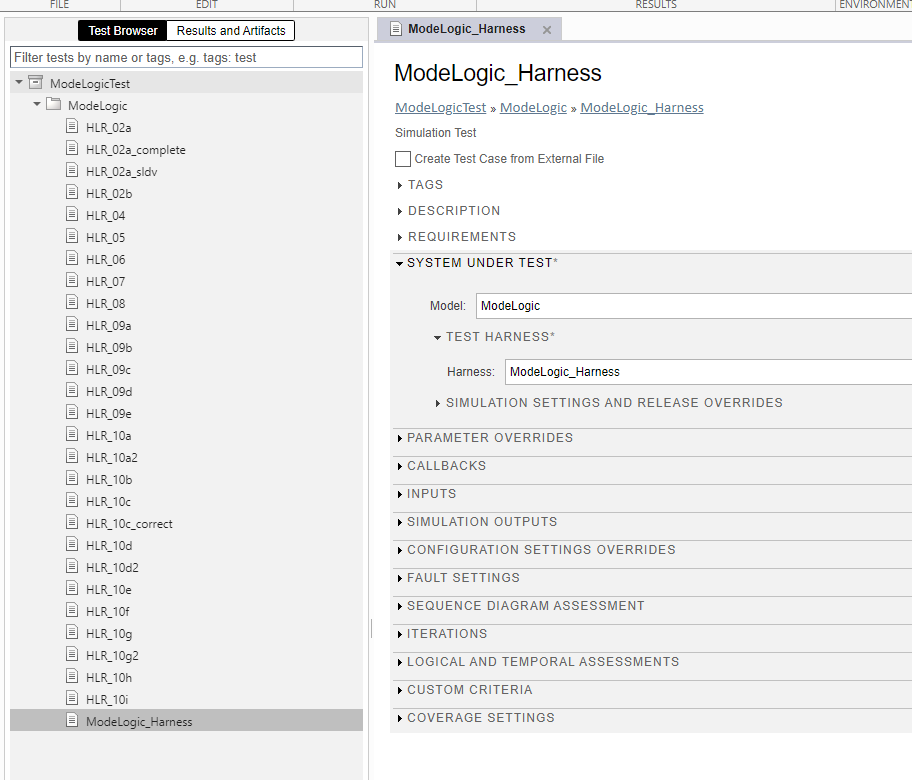

## Step 5: Execute the Test Case and Inspect the Result

1) To execute the test case, right click on the test case "ModeLogic_Harness" and click "Run". 

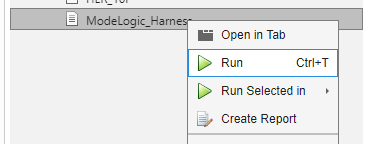

2) After test execution is complete, navigate to "Results and Artifacts" tab to review the result. Click on the "Verify Statement" check box and review the result for landing mode. Can you see why the data point shows up at t=3.6s?

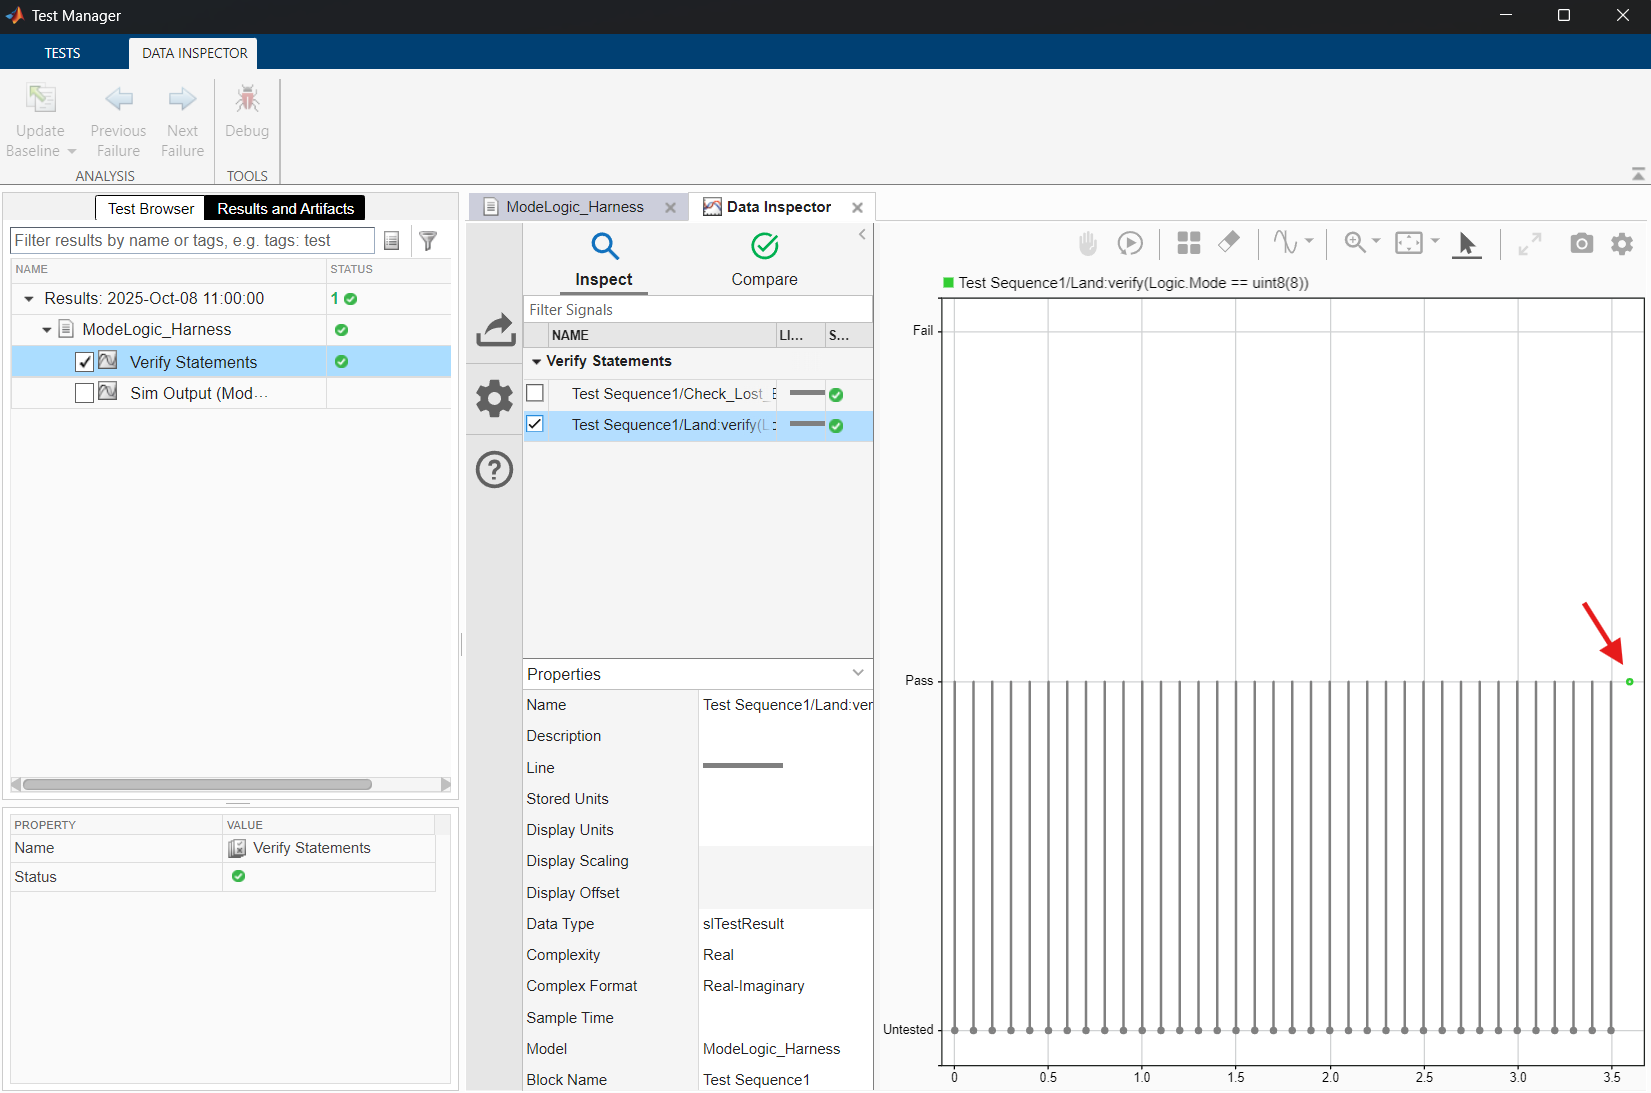

3) You can also review any signals logged during simulation. Click the "Sim Output" check box and select a signal to review (e.g. "Mode" signal representing flight mode transitions throughout the simulation.)

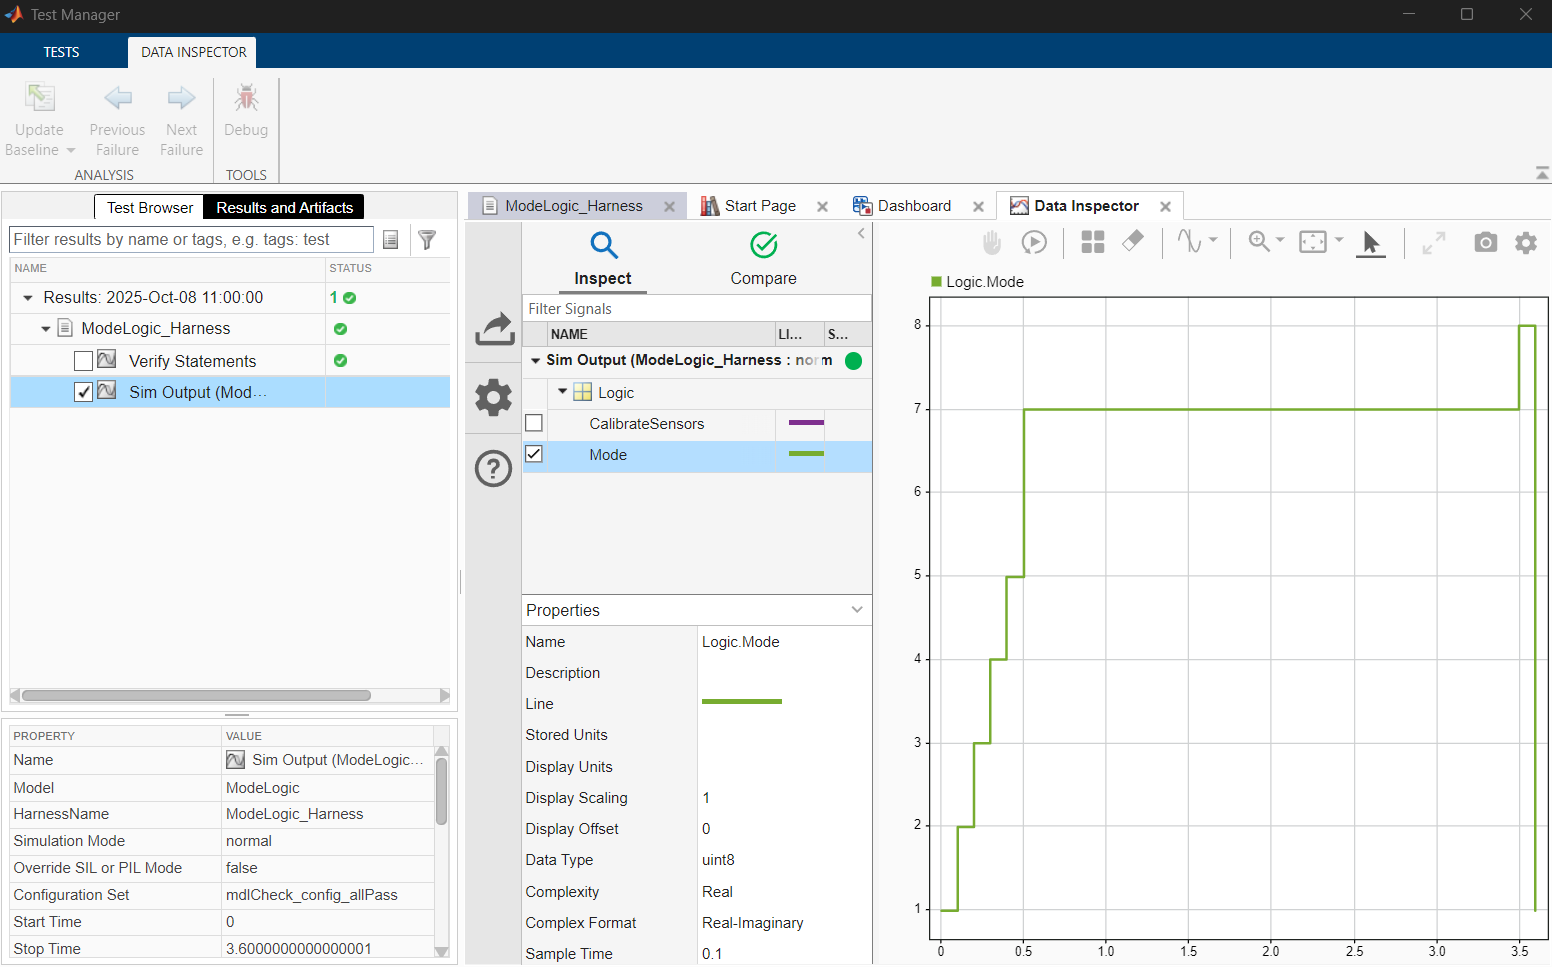

## Step 6: Link Test Case to Requirements

Now that we have a working test case, let's make sure we link the test case to a requirement. This can all be done within Simulink® using Simulink® Test™ and Requirements Toolbox™.

By linking a test case to its associated requirement, we can later execute the test case directly from Requirements Toolbox™.

We will be using a Traceability Matrix to create a link. A Traceability Matrix allows you to create and view requirements and links to several items.

Here are the steps to take:

1) Open the requirement set and test file for ModeLogic, using the following commands:

slreq.open('HLR_ModeLogic');
sltest.testmanager.load('ModeLogicTest.mldatx');
sltest.testmanager.view;

2) In the Requirements Editor, click on the Traceability Matrix button in the Toolstrip:

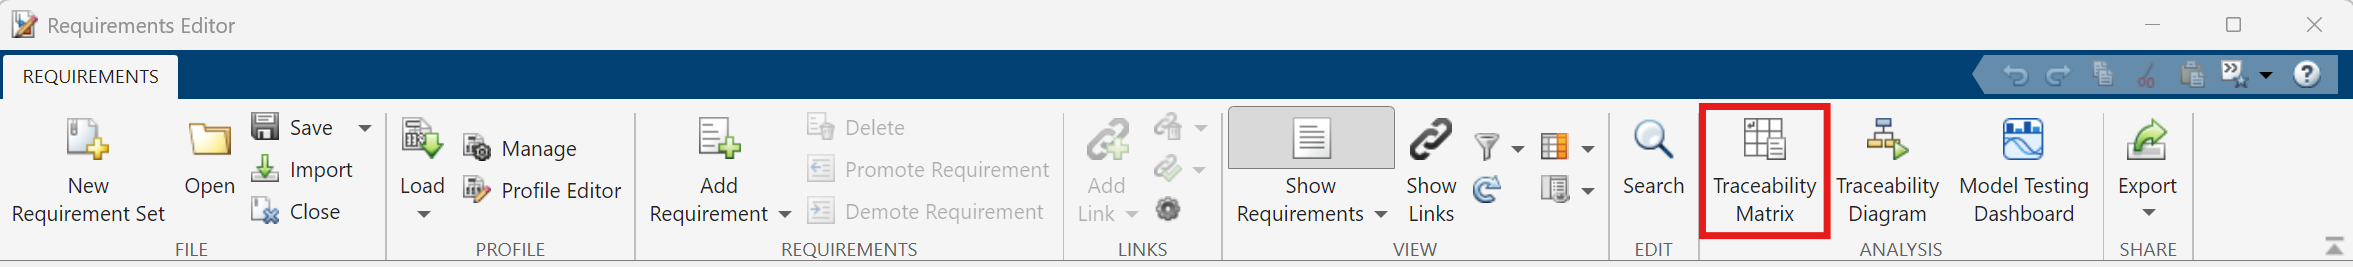

This will open the Traceability Matrix window.

3) In the Traceability Matrix window, click the "Add" button:

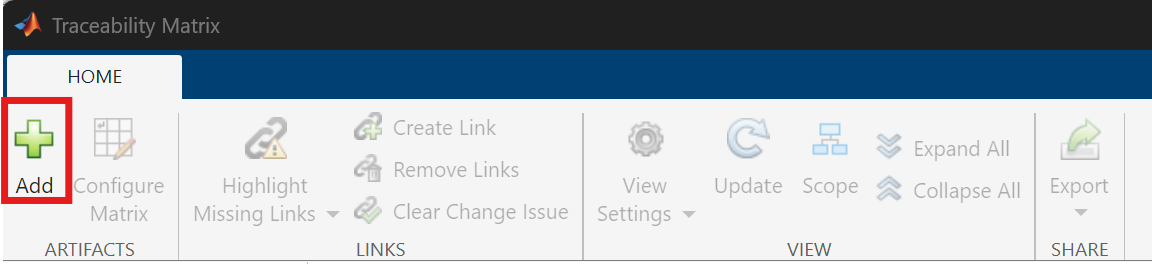

This will launch the Select Artifacts window, which you can use to generate a traceability matrix between two artifacts (e.g., a requirements set and a test suite).

4) In the Select Artifacts window, select **HLR_ModeLogic.slreqx **for the Left artifact and **ModeLogicTest.mldatx** for the Top. Then select "Generate Matrix".

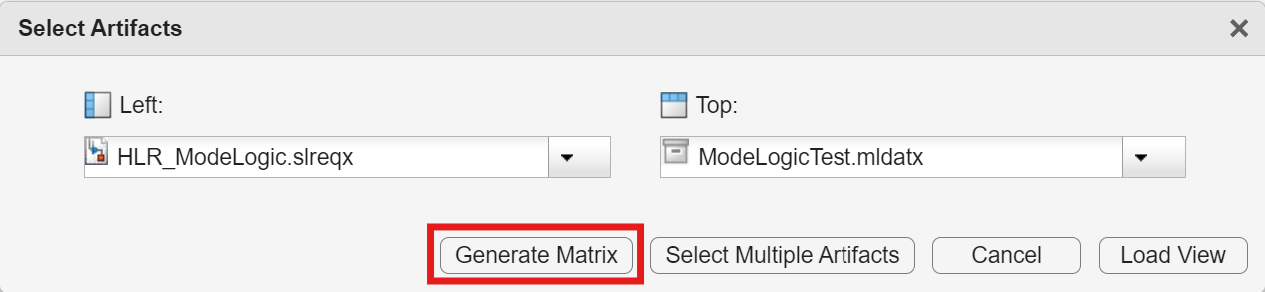

5) In the generated Traceability Matrix, navigate to the requirements section to the row for "Enter Land from Lost Ball". We want to link this requirement to the ModeLogic_Harness test case we just created.

To do this, click on the corresponding cell in the matrix, then click "Create"

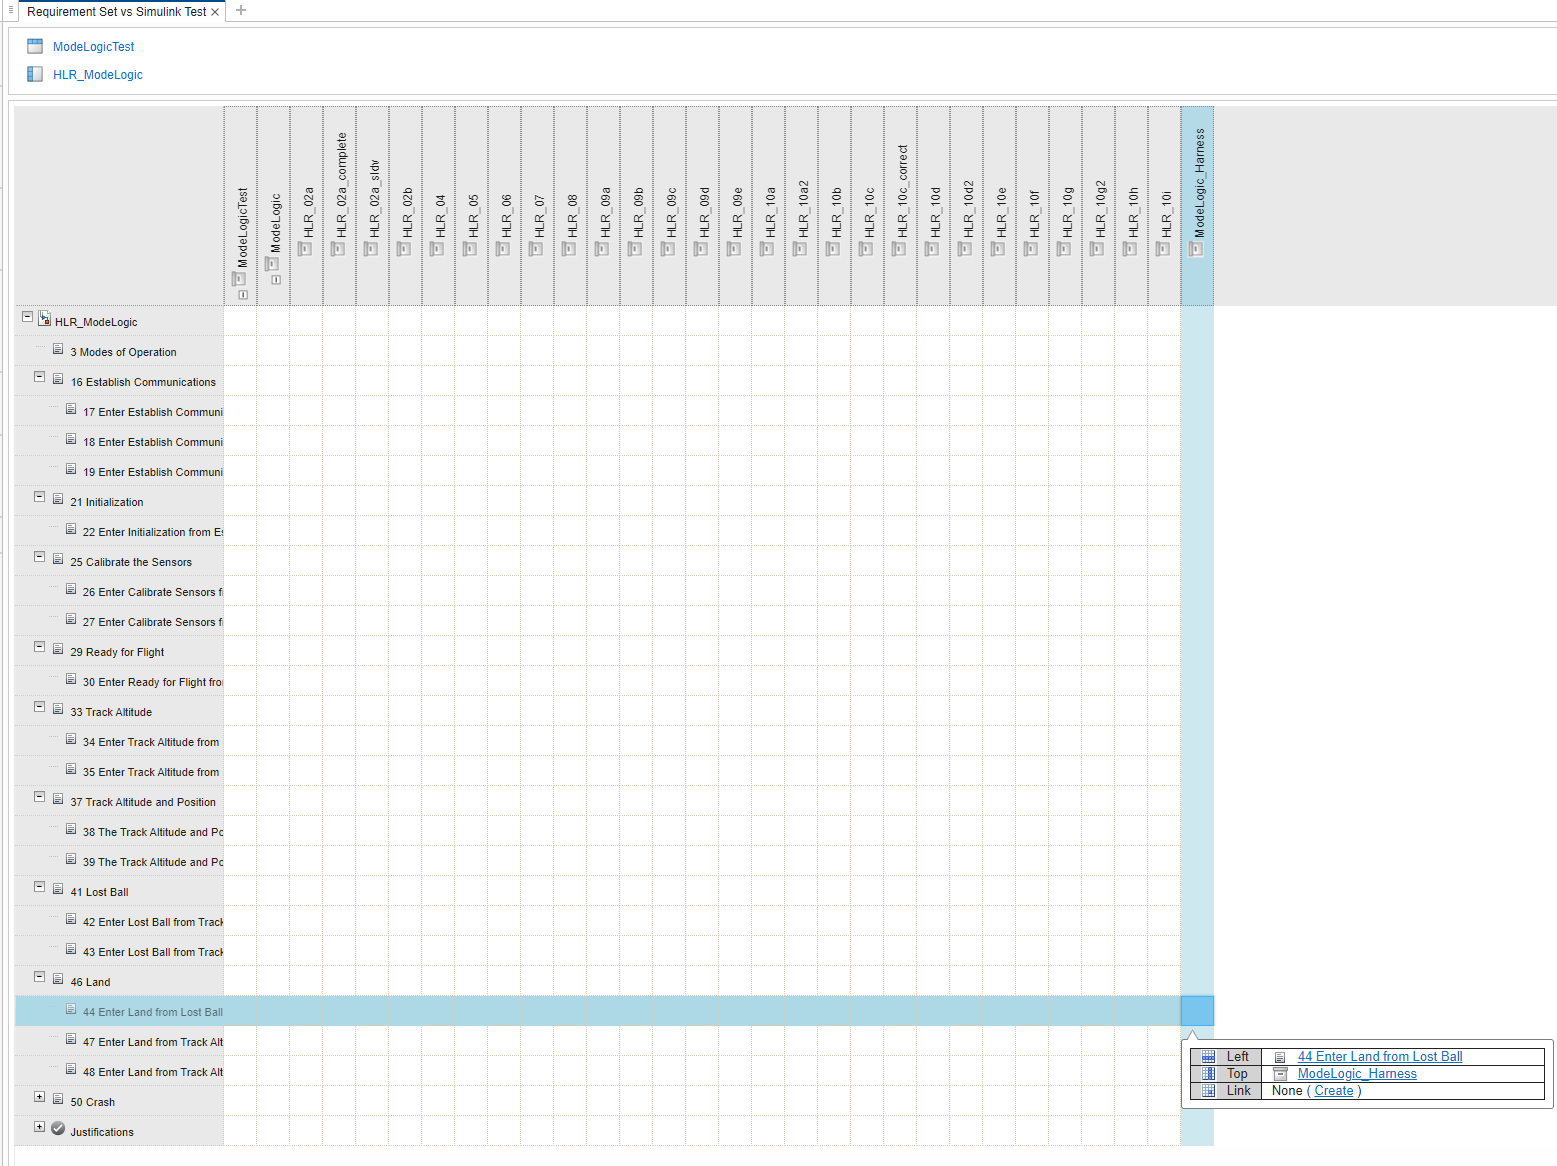

You can create additional links between artifacts within the same Traceability Matrix.

6) In the "Create Link" dialog box, select "Verifies" and click "Create".

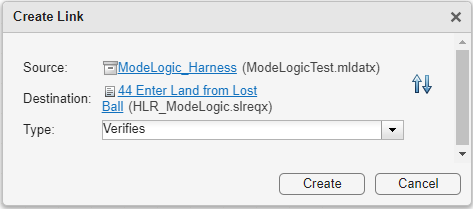

Congrats! You have successfully created a new test case using a Test Sequence as well as linked the test case to its relevant requirement. You can go back to the test case "Requirements" to see that the link has been established.

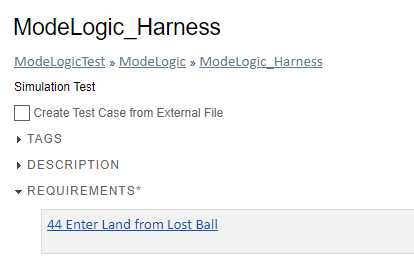

## Step 7: Link Design Implementation to Requirements

Now that we have a link between test and requirement, we also want to link our design implementation to our requirements. Direct links from transitions to requirements help enforce compliance and enable traceability for design reviews and automated reporting.

1) Open the Stateflow chart inside ModeLogic model and navigate the state transition that corresponds to *Requirement 9.1** Enter Land from Lost Ball: The Land mode shall be entered from the Lost Ball mode when the quadcopter has been in Lost Ball mode for 3 seconds. *(Note that the sample time of this model is set to 0.1).

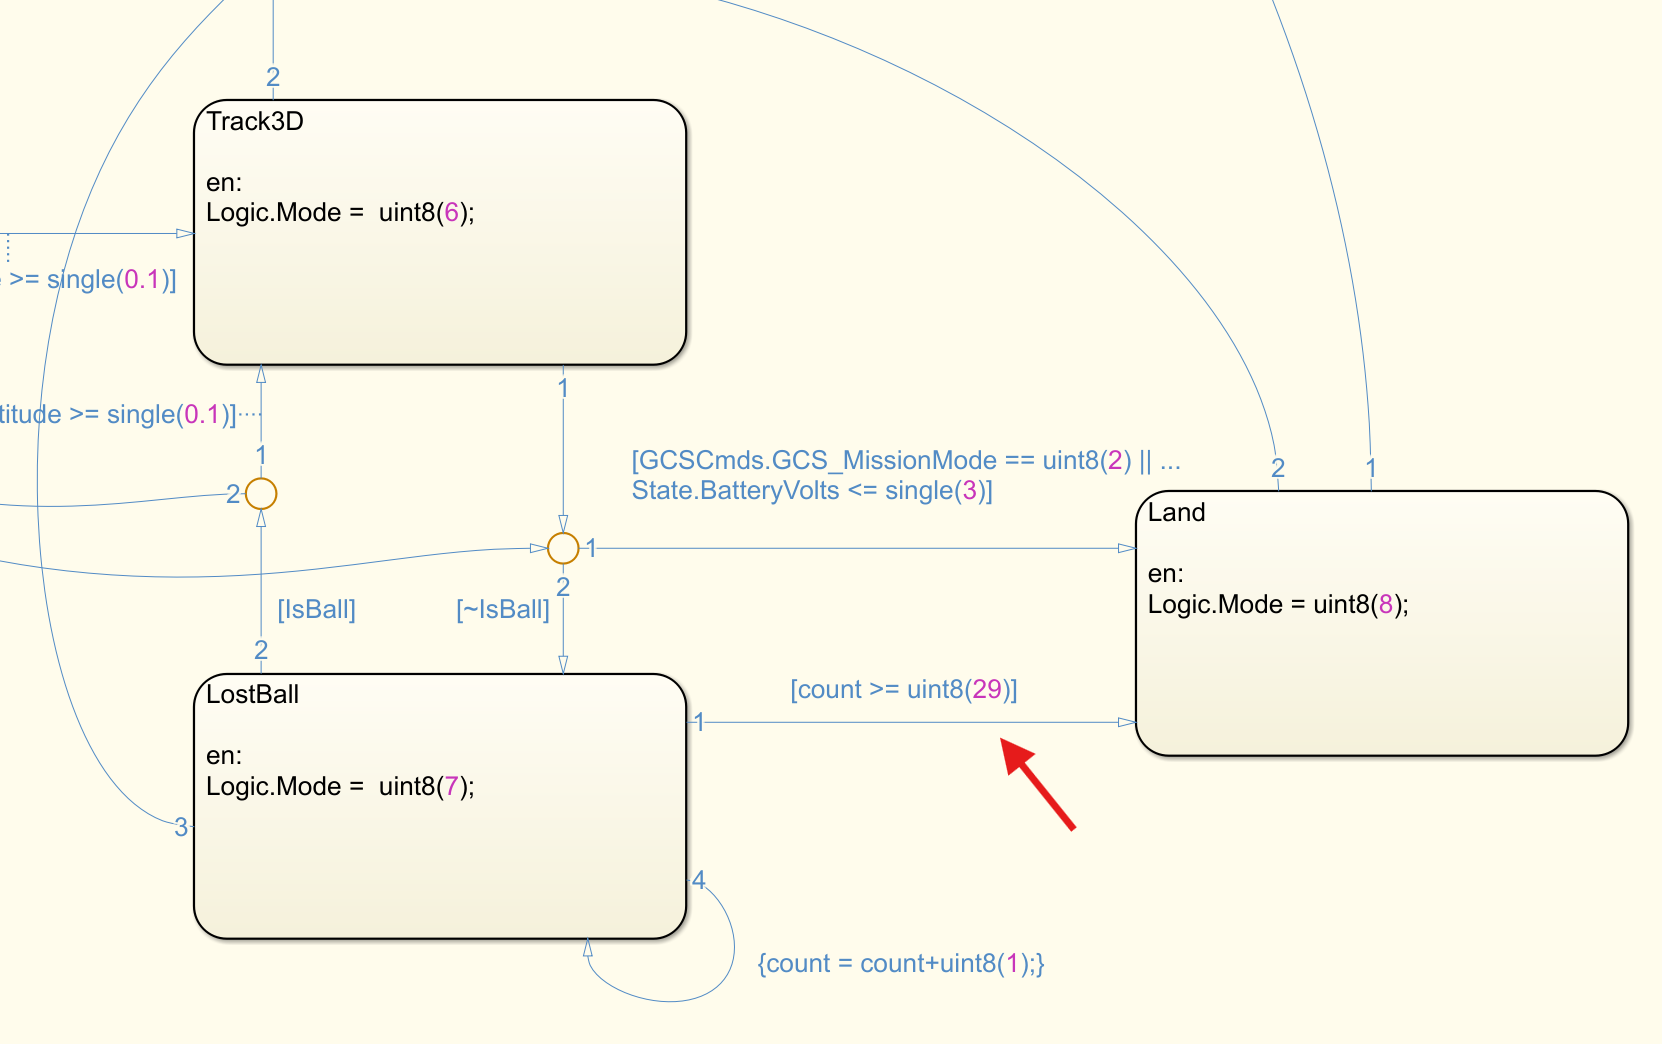

2) Now, let's add the link between this transition to the requirement. First, open the Requirements Editor and select/navigate to Requirement 9.1.

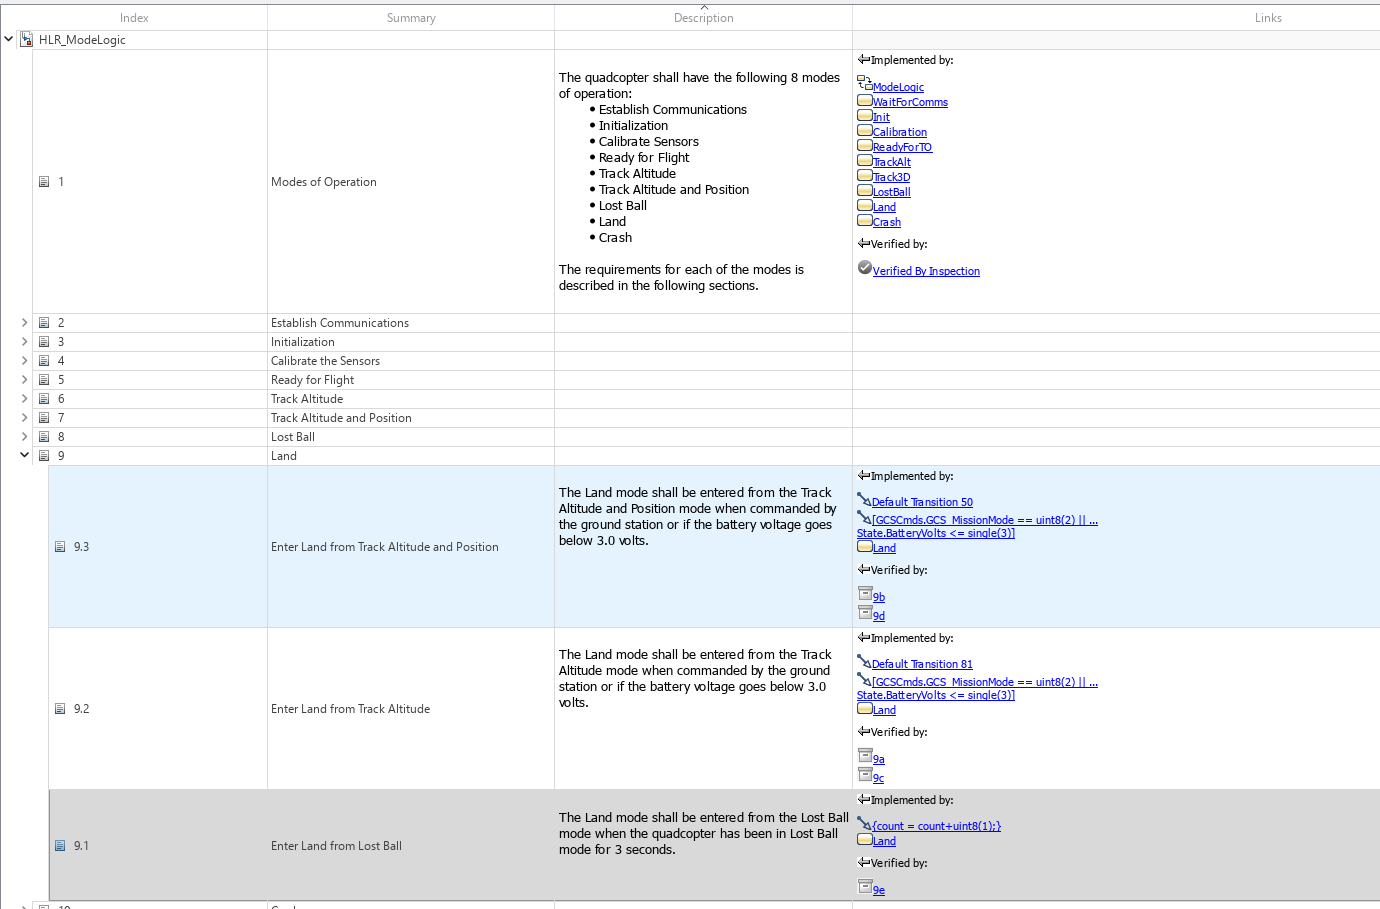

3) Next, go back to the Stateflow chart and right click on the transition, then select Requirements -> Link to Selection in Requirements Browser.

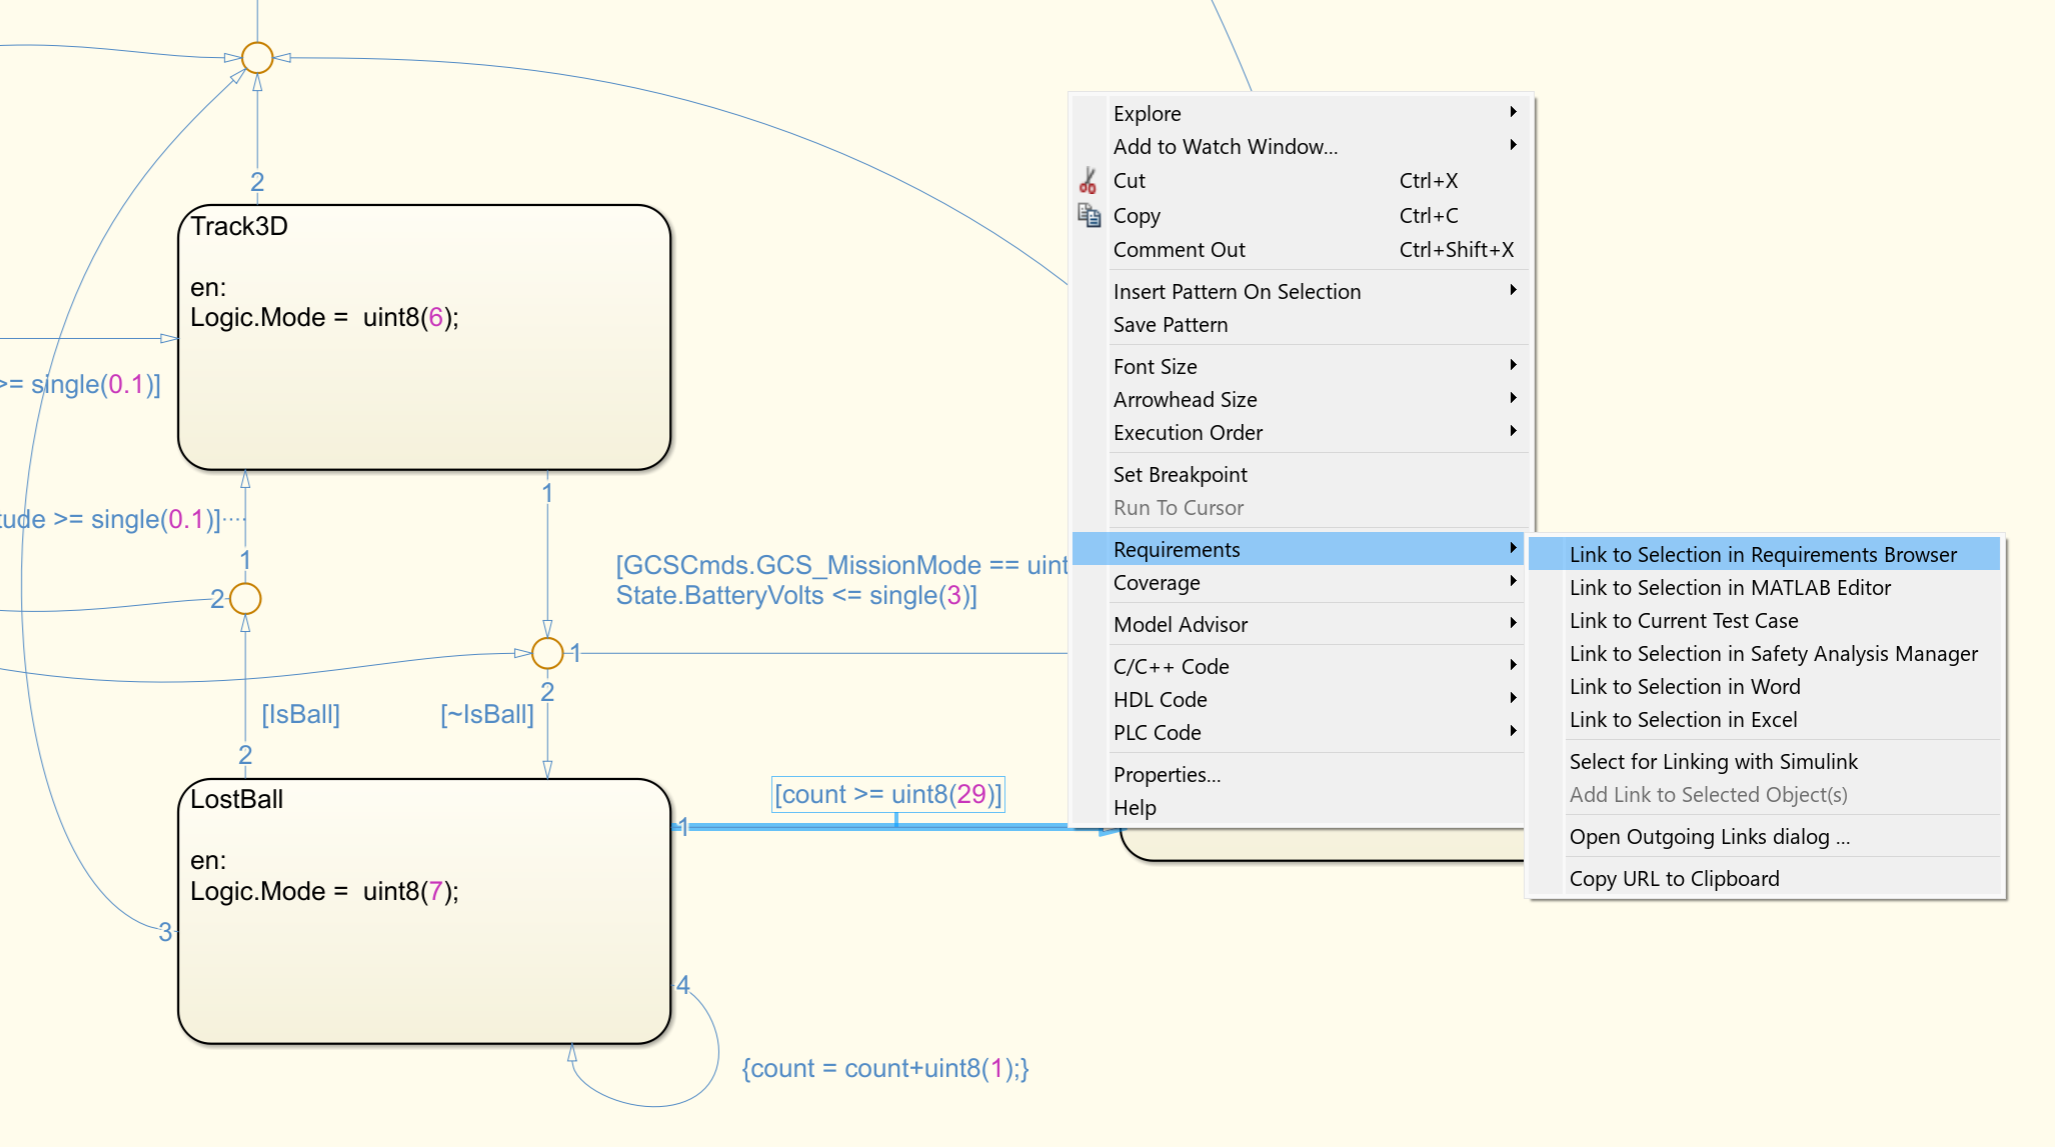

4) Now you have linked this transition to the Requirement 9.1. To view this, open Requirements Perspective from the bottom right corner.

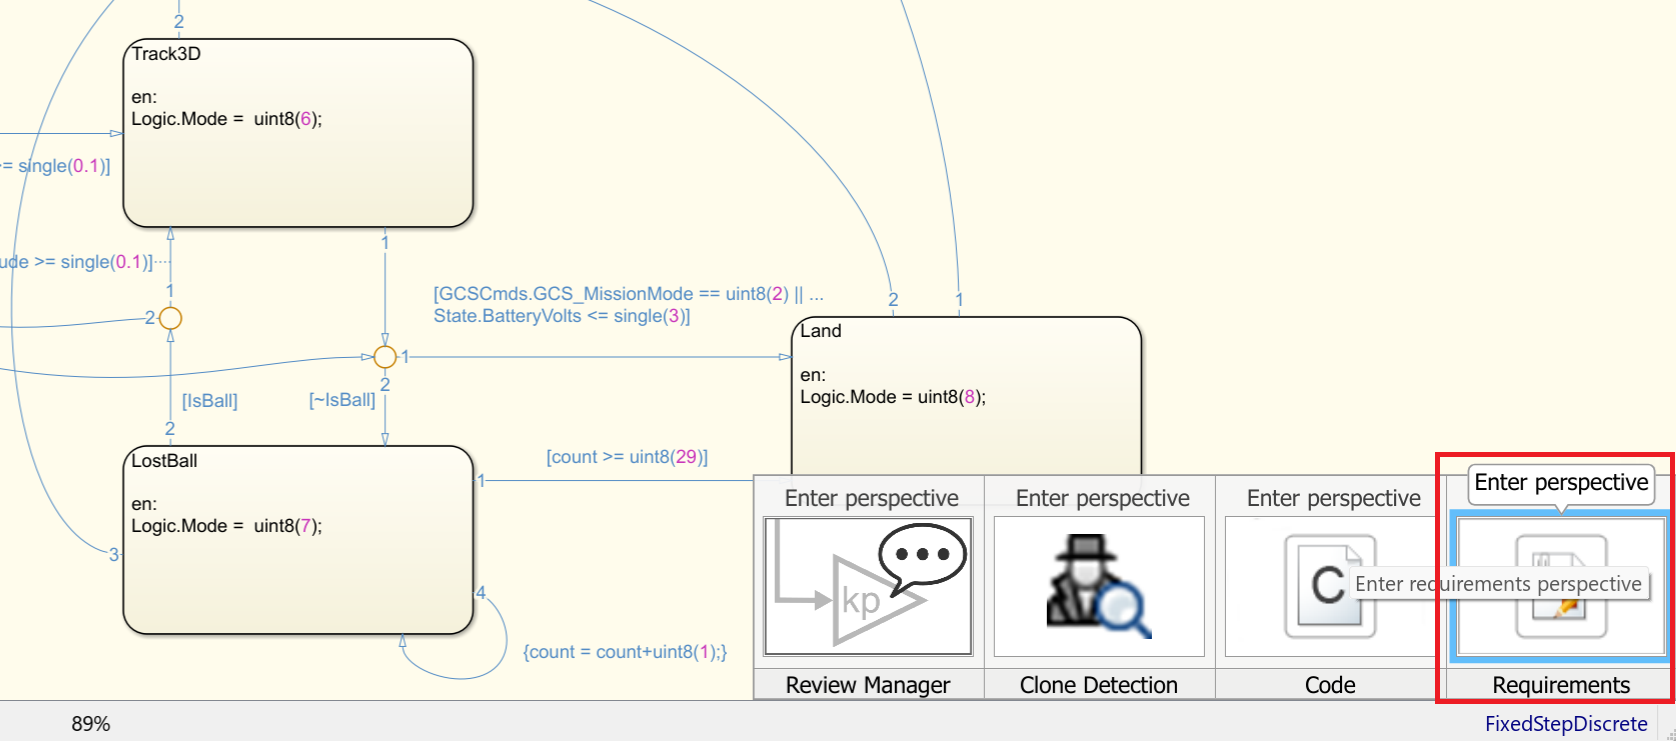

From here, you can view the traceability and description of the linked requirement.

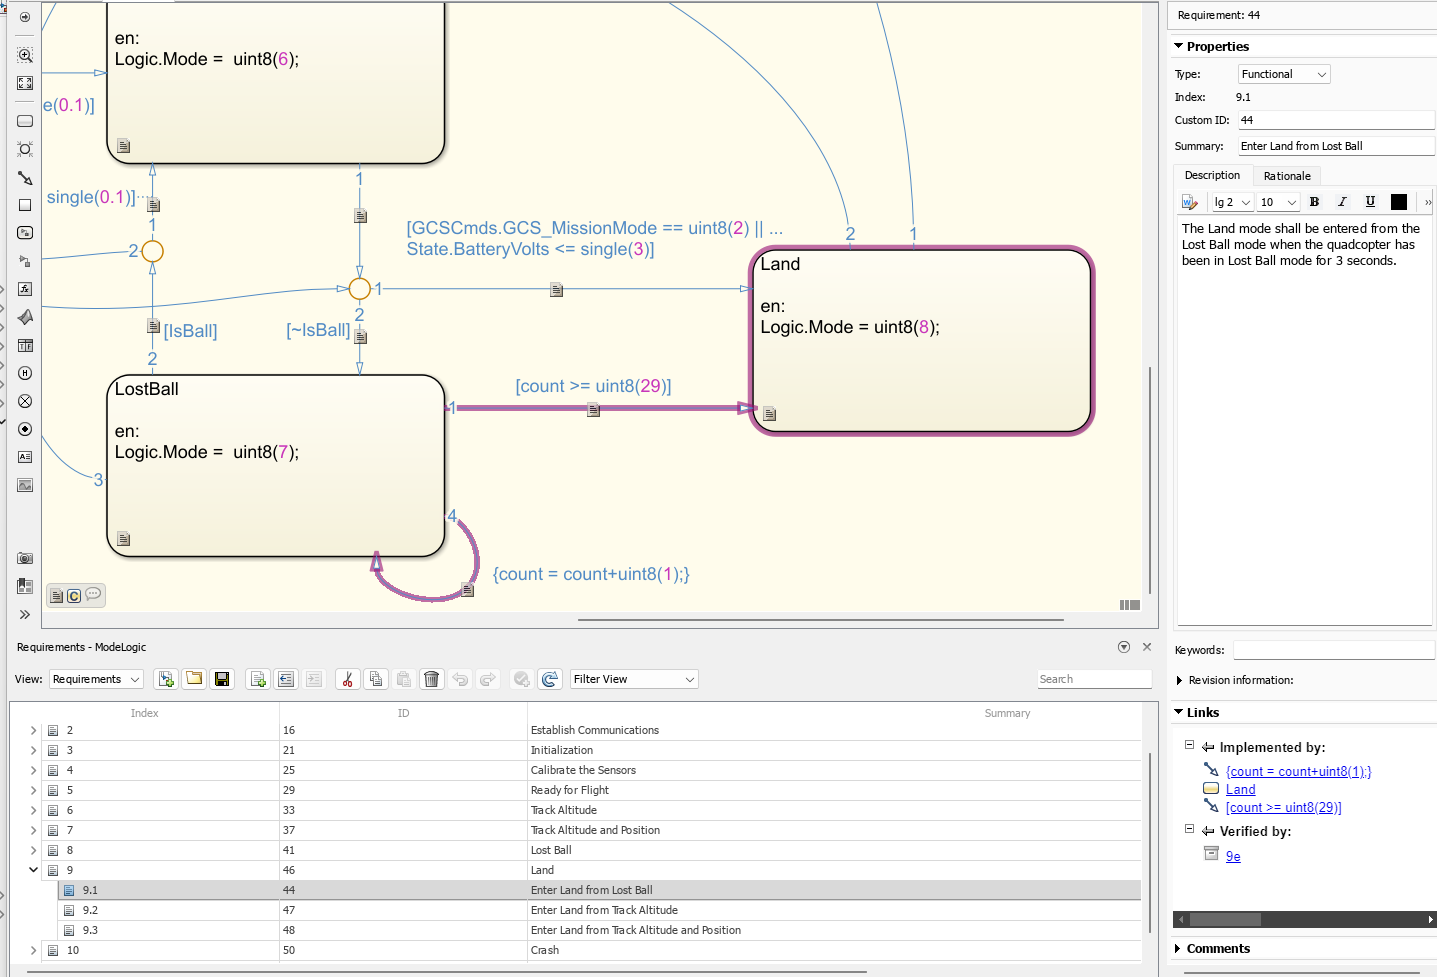

# Part 3: Run a Test File and Resolve Missing Model Test Coverage

In this part, we will be running a full set of test cases to make sure we have fully tested the design.

The goals for this part are to learn how to:

- Execute a test suite using Simulink® Test™

- Measure test coverage using Simulink Coverage™

- Resolve missing test coverage

- Scope coverage results to requirements

Model test coverage, or "model coverage," is a measure of how much of your design has been tested through simulation. Having full model coverage ensures that you have accounted for all behavior in your model. Missing model coverage may be the result of dead logic, incomplete testing, unexpected functionality, or incomplete/missing requirements.

In addition to Requirements Toolbox™ and Simulink® Test™, which you used in Part 1, you will be using **Simulink® Coverage™ **to measure test coverage for Simulink models and generated code.

You will be running a pre-created test suite within Simulink® Test™. This test suite contains several test cases, each of which has been linked to its relevant requirements.

A best practice is to limit the scope of a test to its related requirements. This is done in order to make it easier to analyze why a test failed. A test that addresses many requirements may seem more efficient, but can become burdensome to troubleshoot when the test fails. In addition, as the requirements and design mature, regression testing can be made easier by having more narrowly scoped tests. In short: try to maintain a 1:1 relationship between requirements and tests whenever possible. With this in mind, most of the tests in the pre-created test suite were written to test a single requirement.

## Step 1: Open Test File in Test Manager

Run the following code to open the test file in the Test Manager:

sltest.testmanager.clear; % clears test files from Test Manager
sltest.testmanager.load('ModeLogic_HLR_Tests.mldatx');
sltest.testmanager.view;

The test file contains a set of requirements-based test cases organized by requirement. Each requirement has a test suite which can consist of several test cases. Take some time to look through the test file.

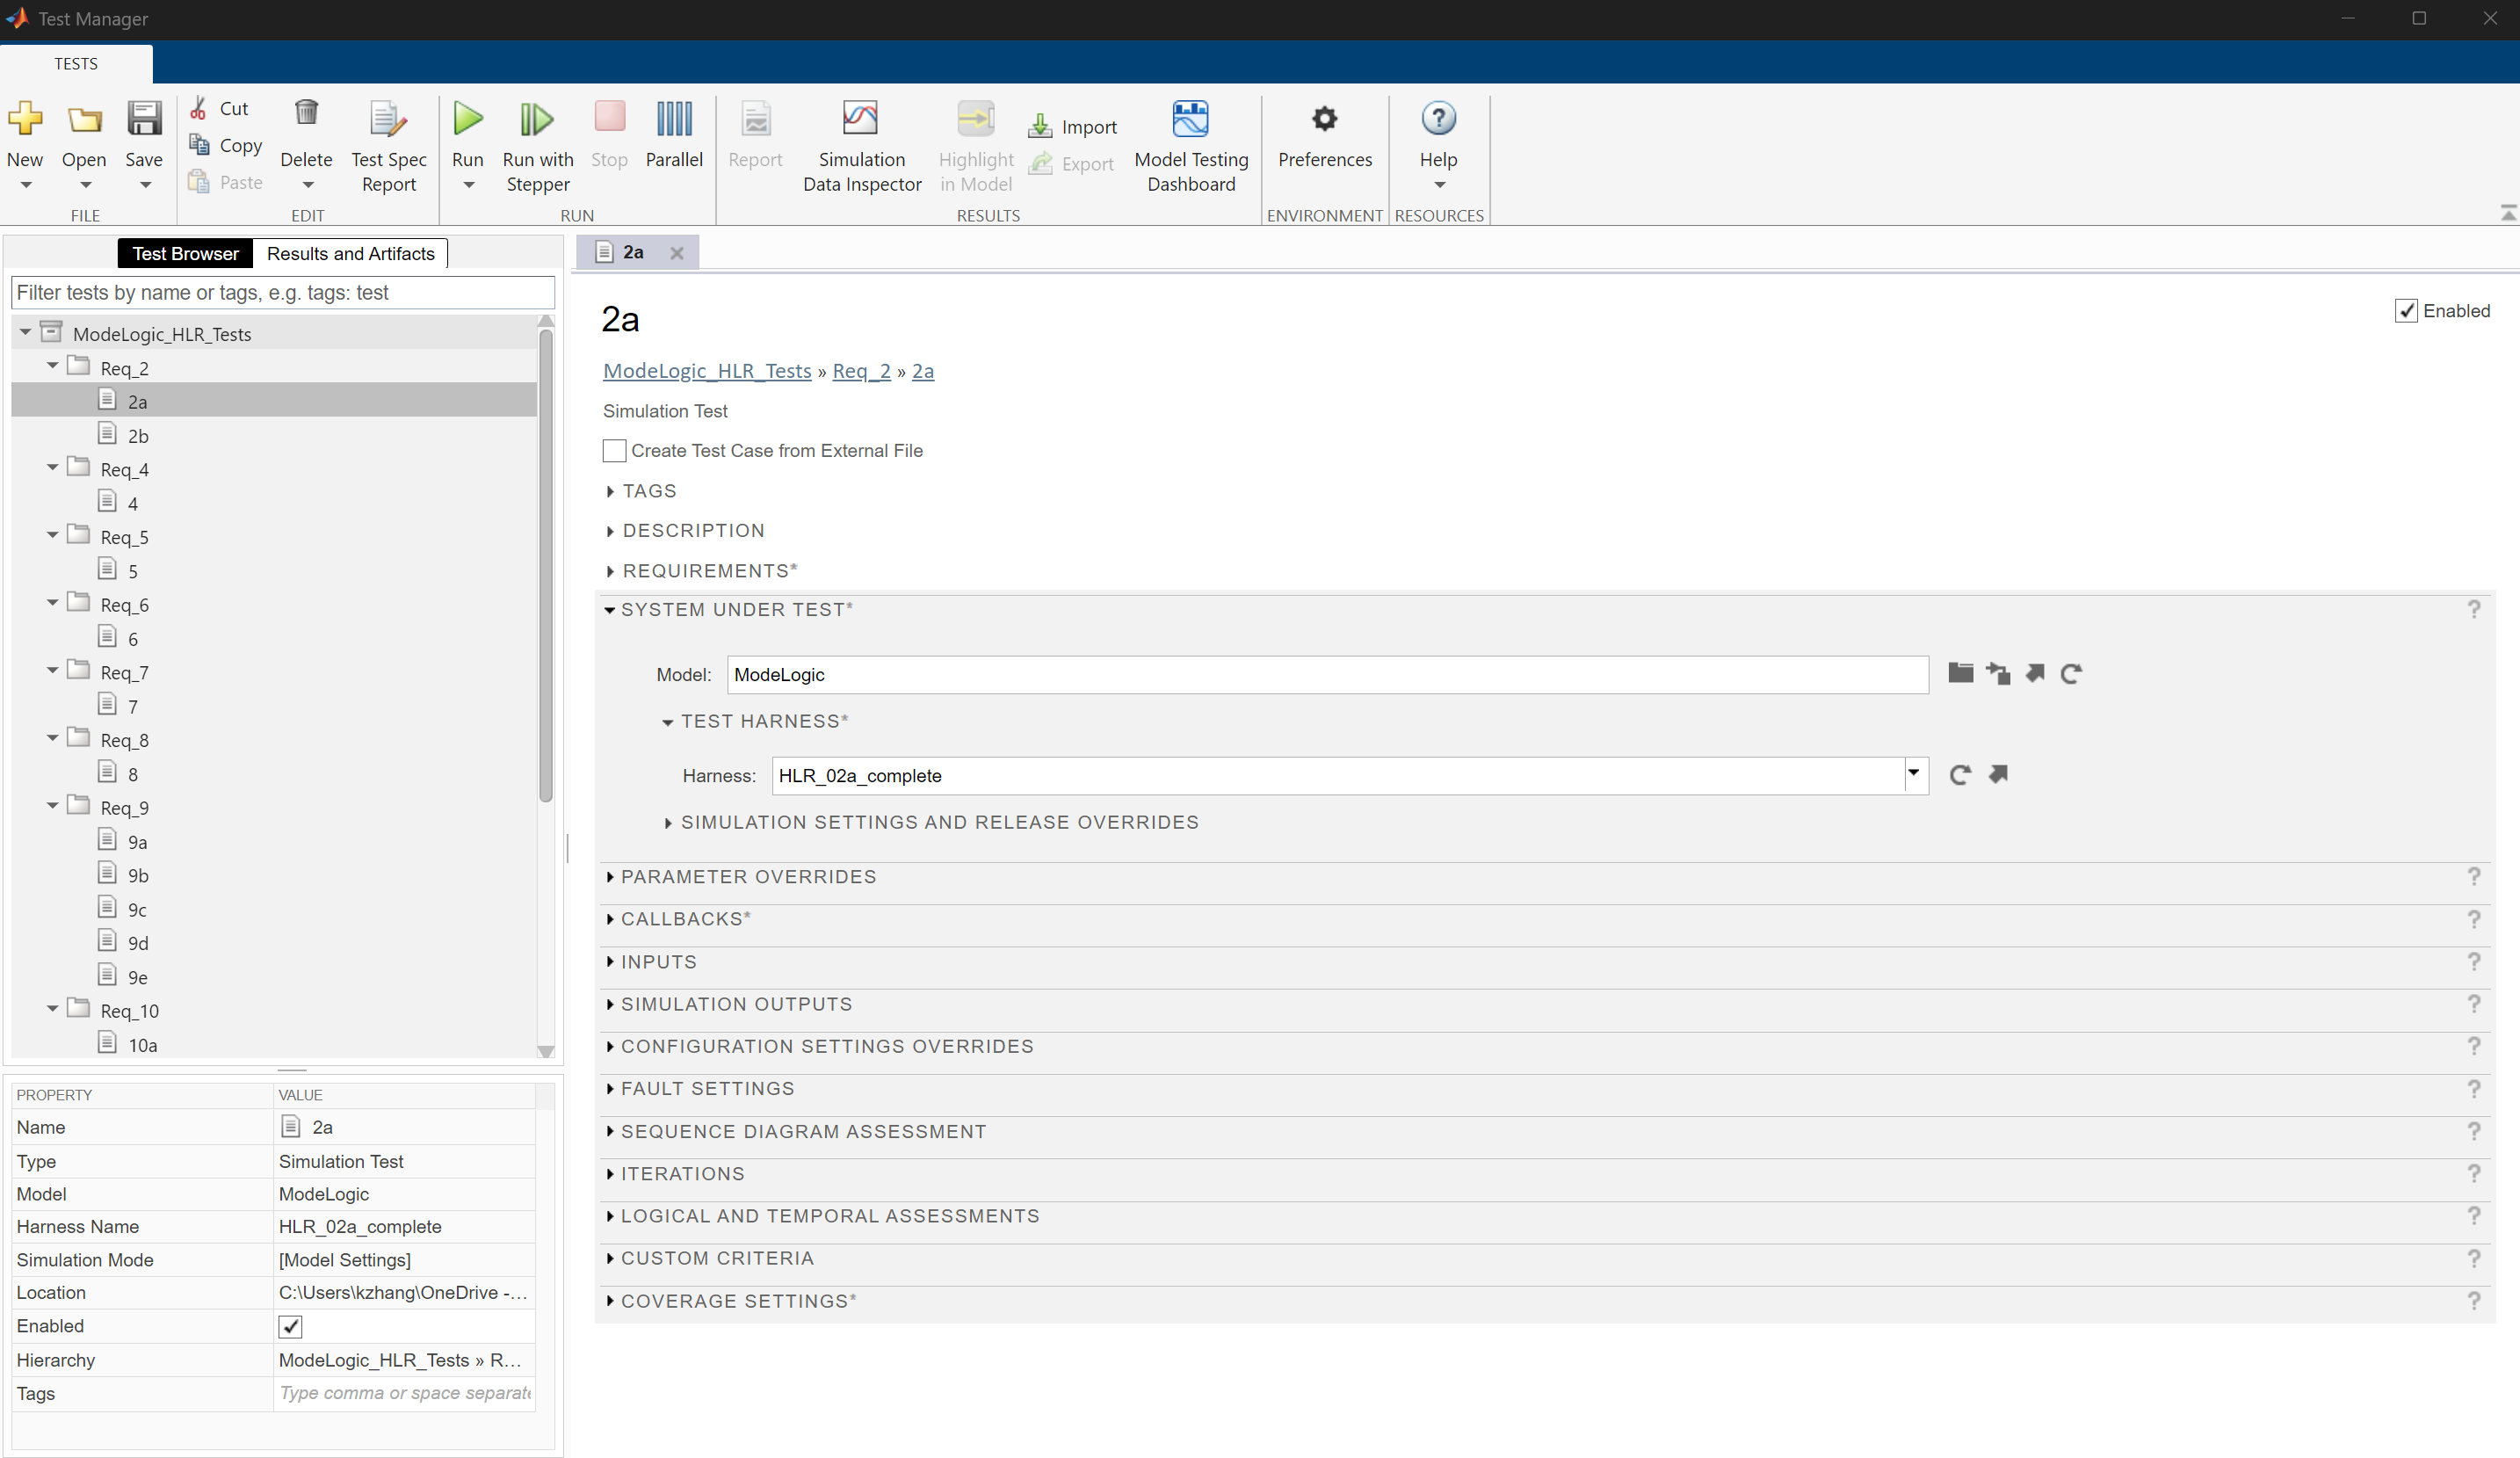

## Step 2: Enable Coverage Collection

We now need to enable model coverage collection for the test file. This is known as "aggregated coverage", because model coverage is collected for each test case and then aggregated across all test cases in the test file. Coverage can also be aggregated by test suite.

Model coverage is collected by **Simulink® Coverage™.**

To enable model coverage collection:

1) Click on the **ModeLogic_HLR_Tests** test suite in the Test Browser in the Test Manager

2) Open the COVERAGE SETTINGS section

3) Select "Record coverage for system under test"

In the COVERAGE METRICS section, the following metrics are already selected: Decision, Condition, MCDC and Signal Range. [**Click here**](https://www.mathworks.com/help/slcoverage/ug/types-of-model-coverage.html) to learn more about these coverage metrics.

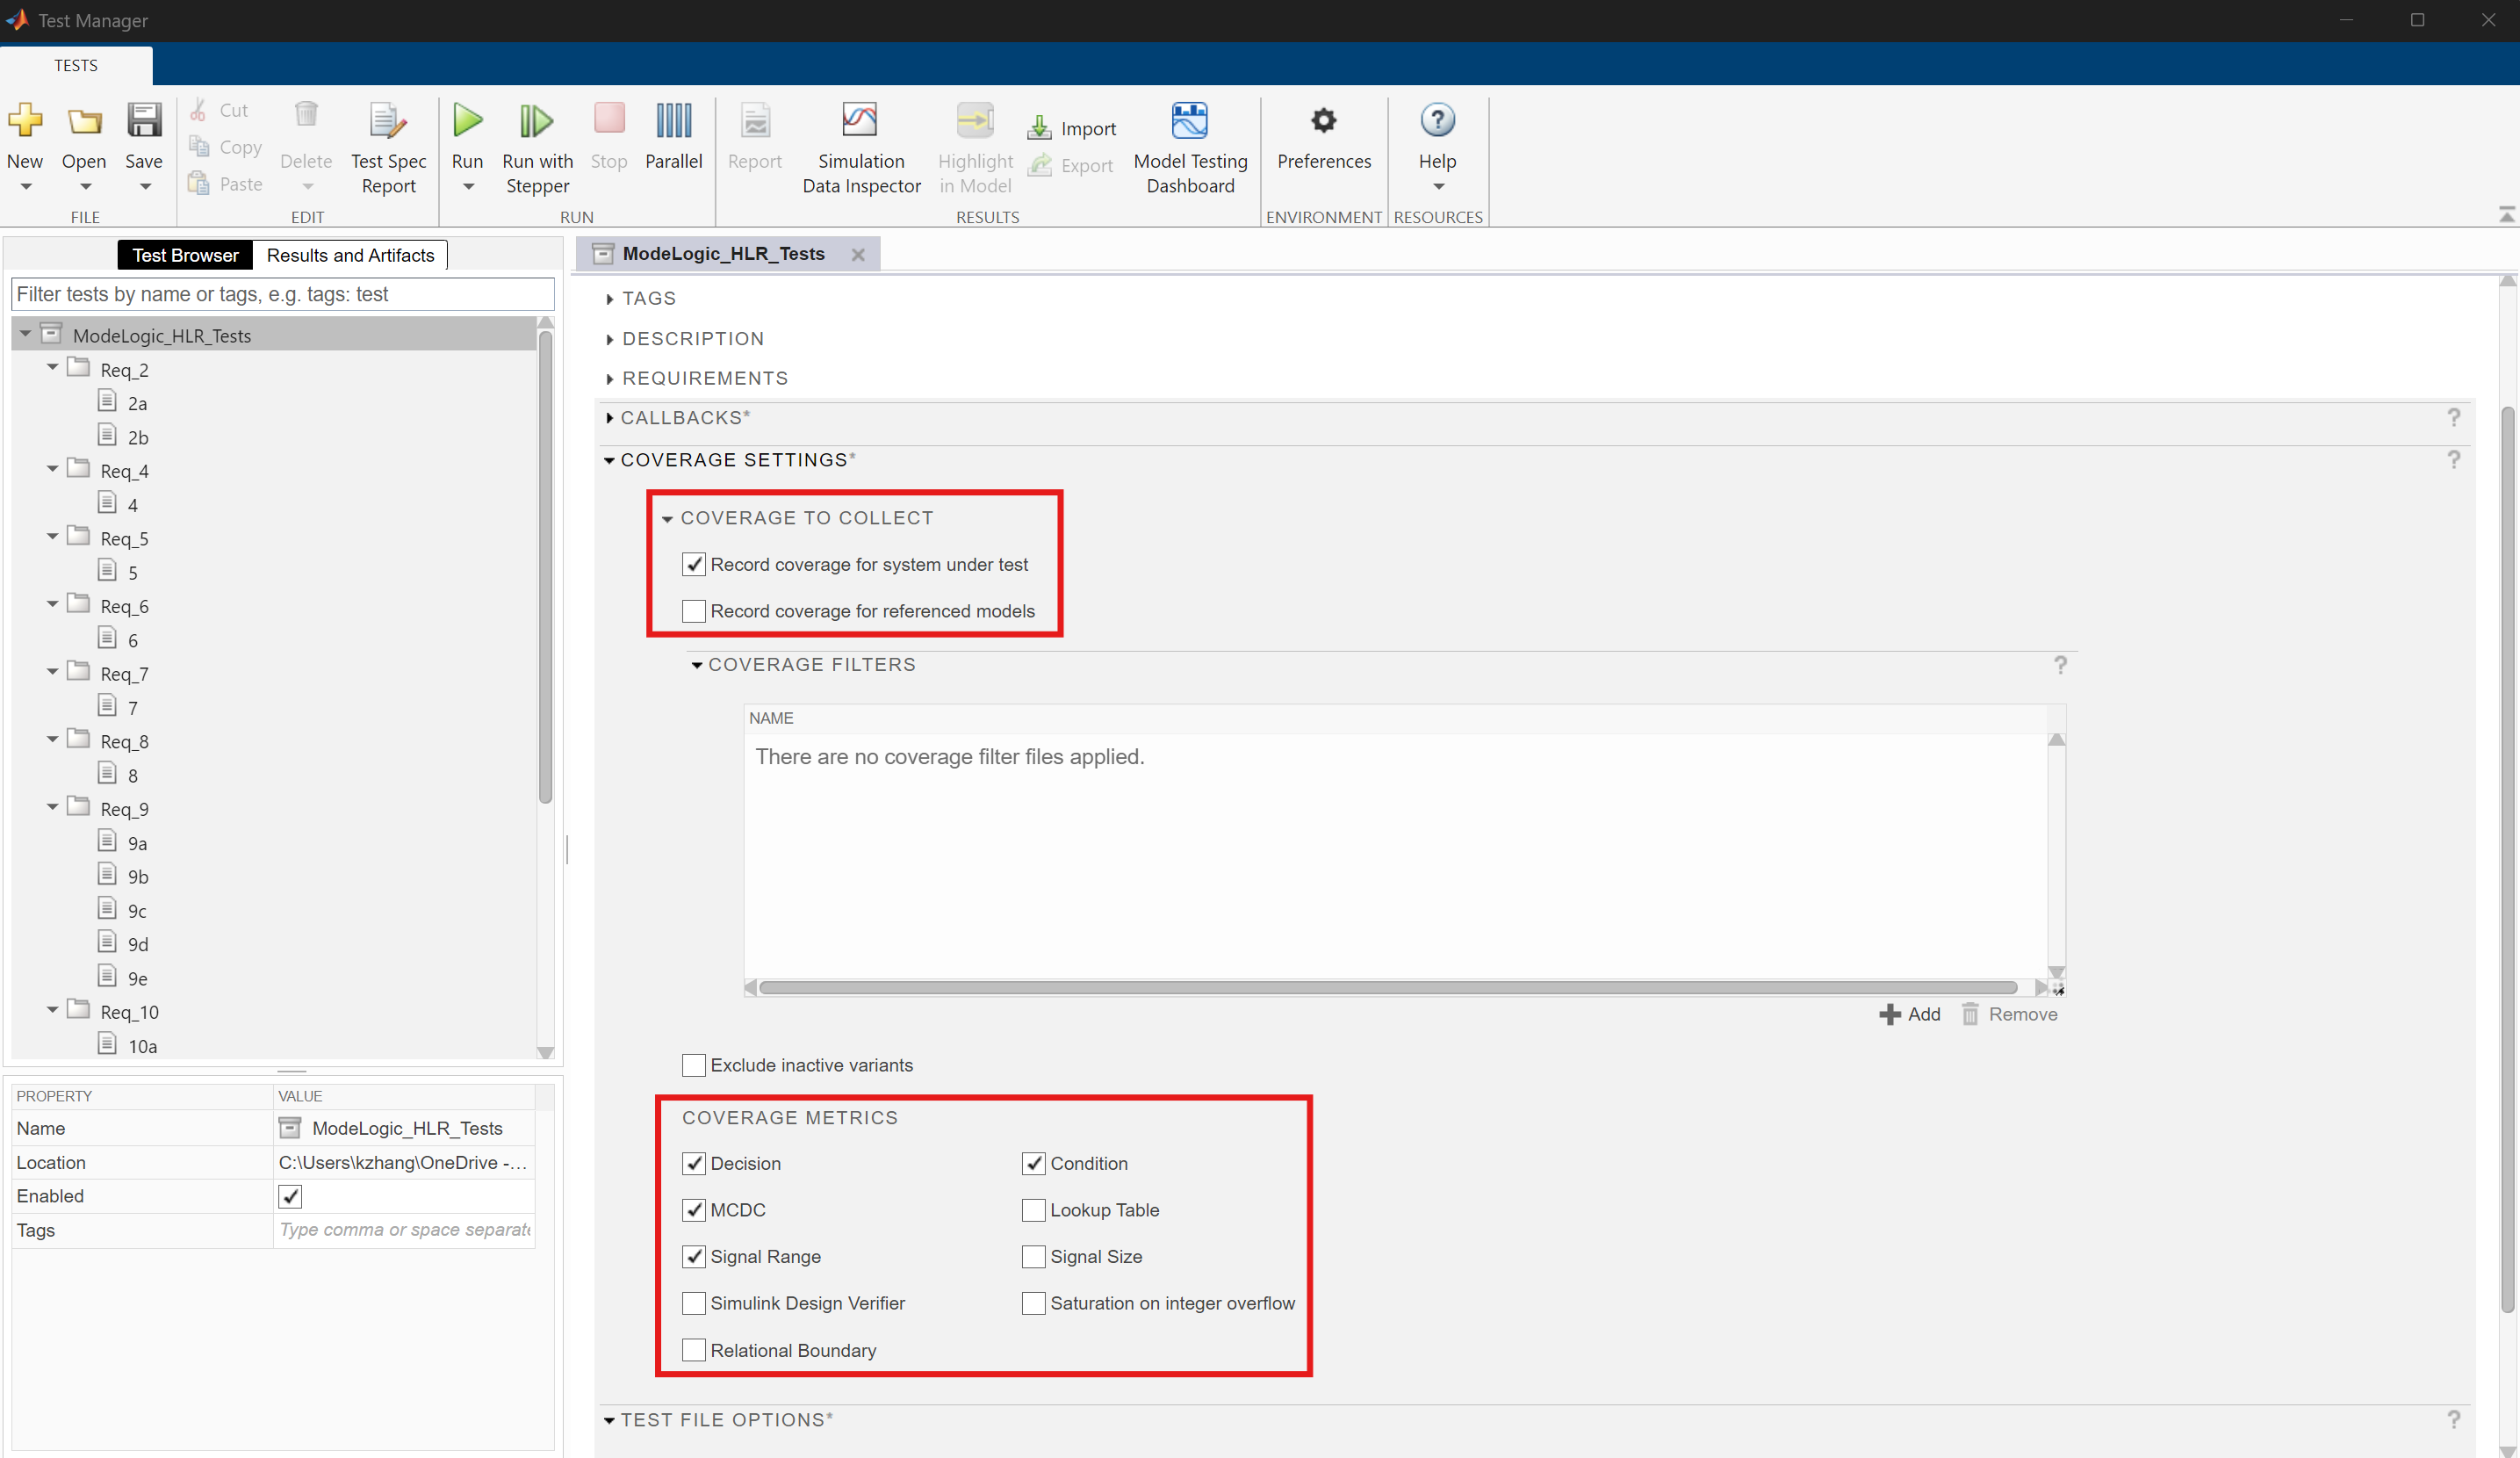

## Step 3: Execute Test File 

To execute the test file:

1) Select the test file **ModeLogic_HLR_Tests** in the Test Browser 

2) Click **Run** in the toolstrip or by using the keyboard shortcut **CTRL + T**

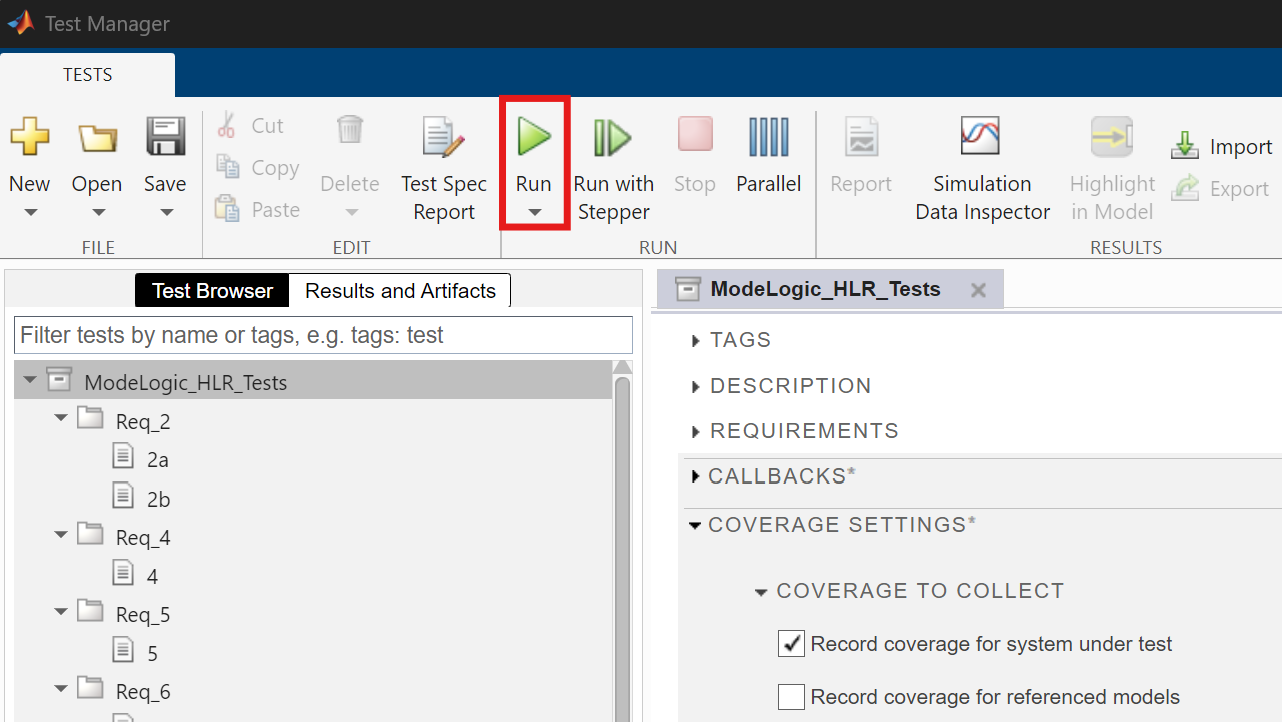

The Test Manager will automatically switch to the **Results and Artifacts** tab to show the test execution progress. This test suite currently has 24 test cases.

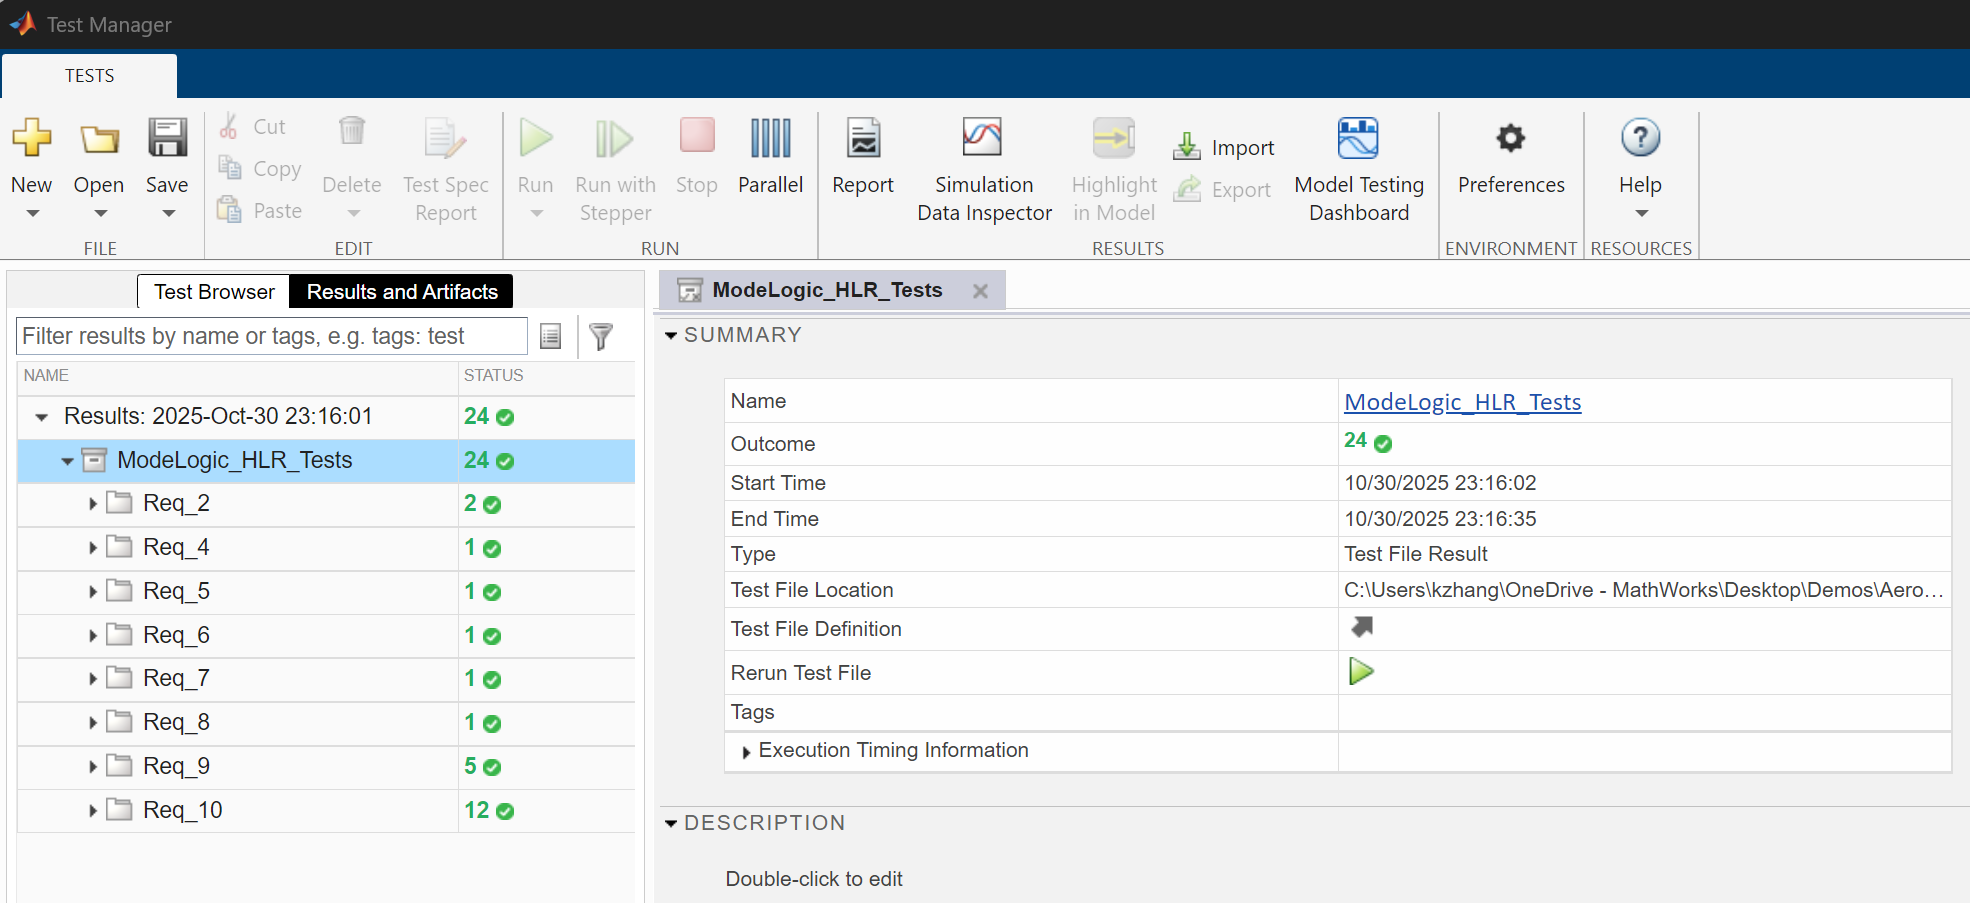

## Step 4: View Model Coverage Results 

1) To view model coverage results, click on the most recent test run in the **Results and Artifacts** tab in the Test Manager, then look under AGGREGATED COVERAGE RESULTS.

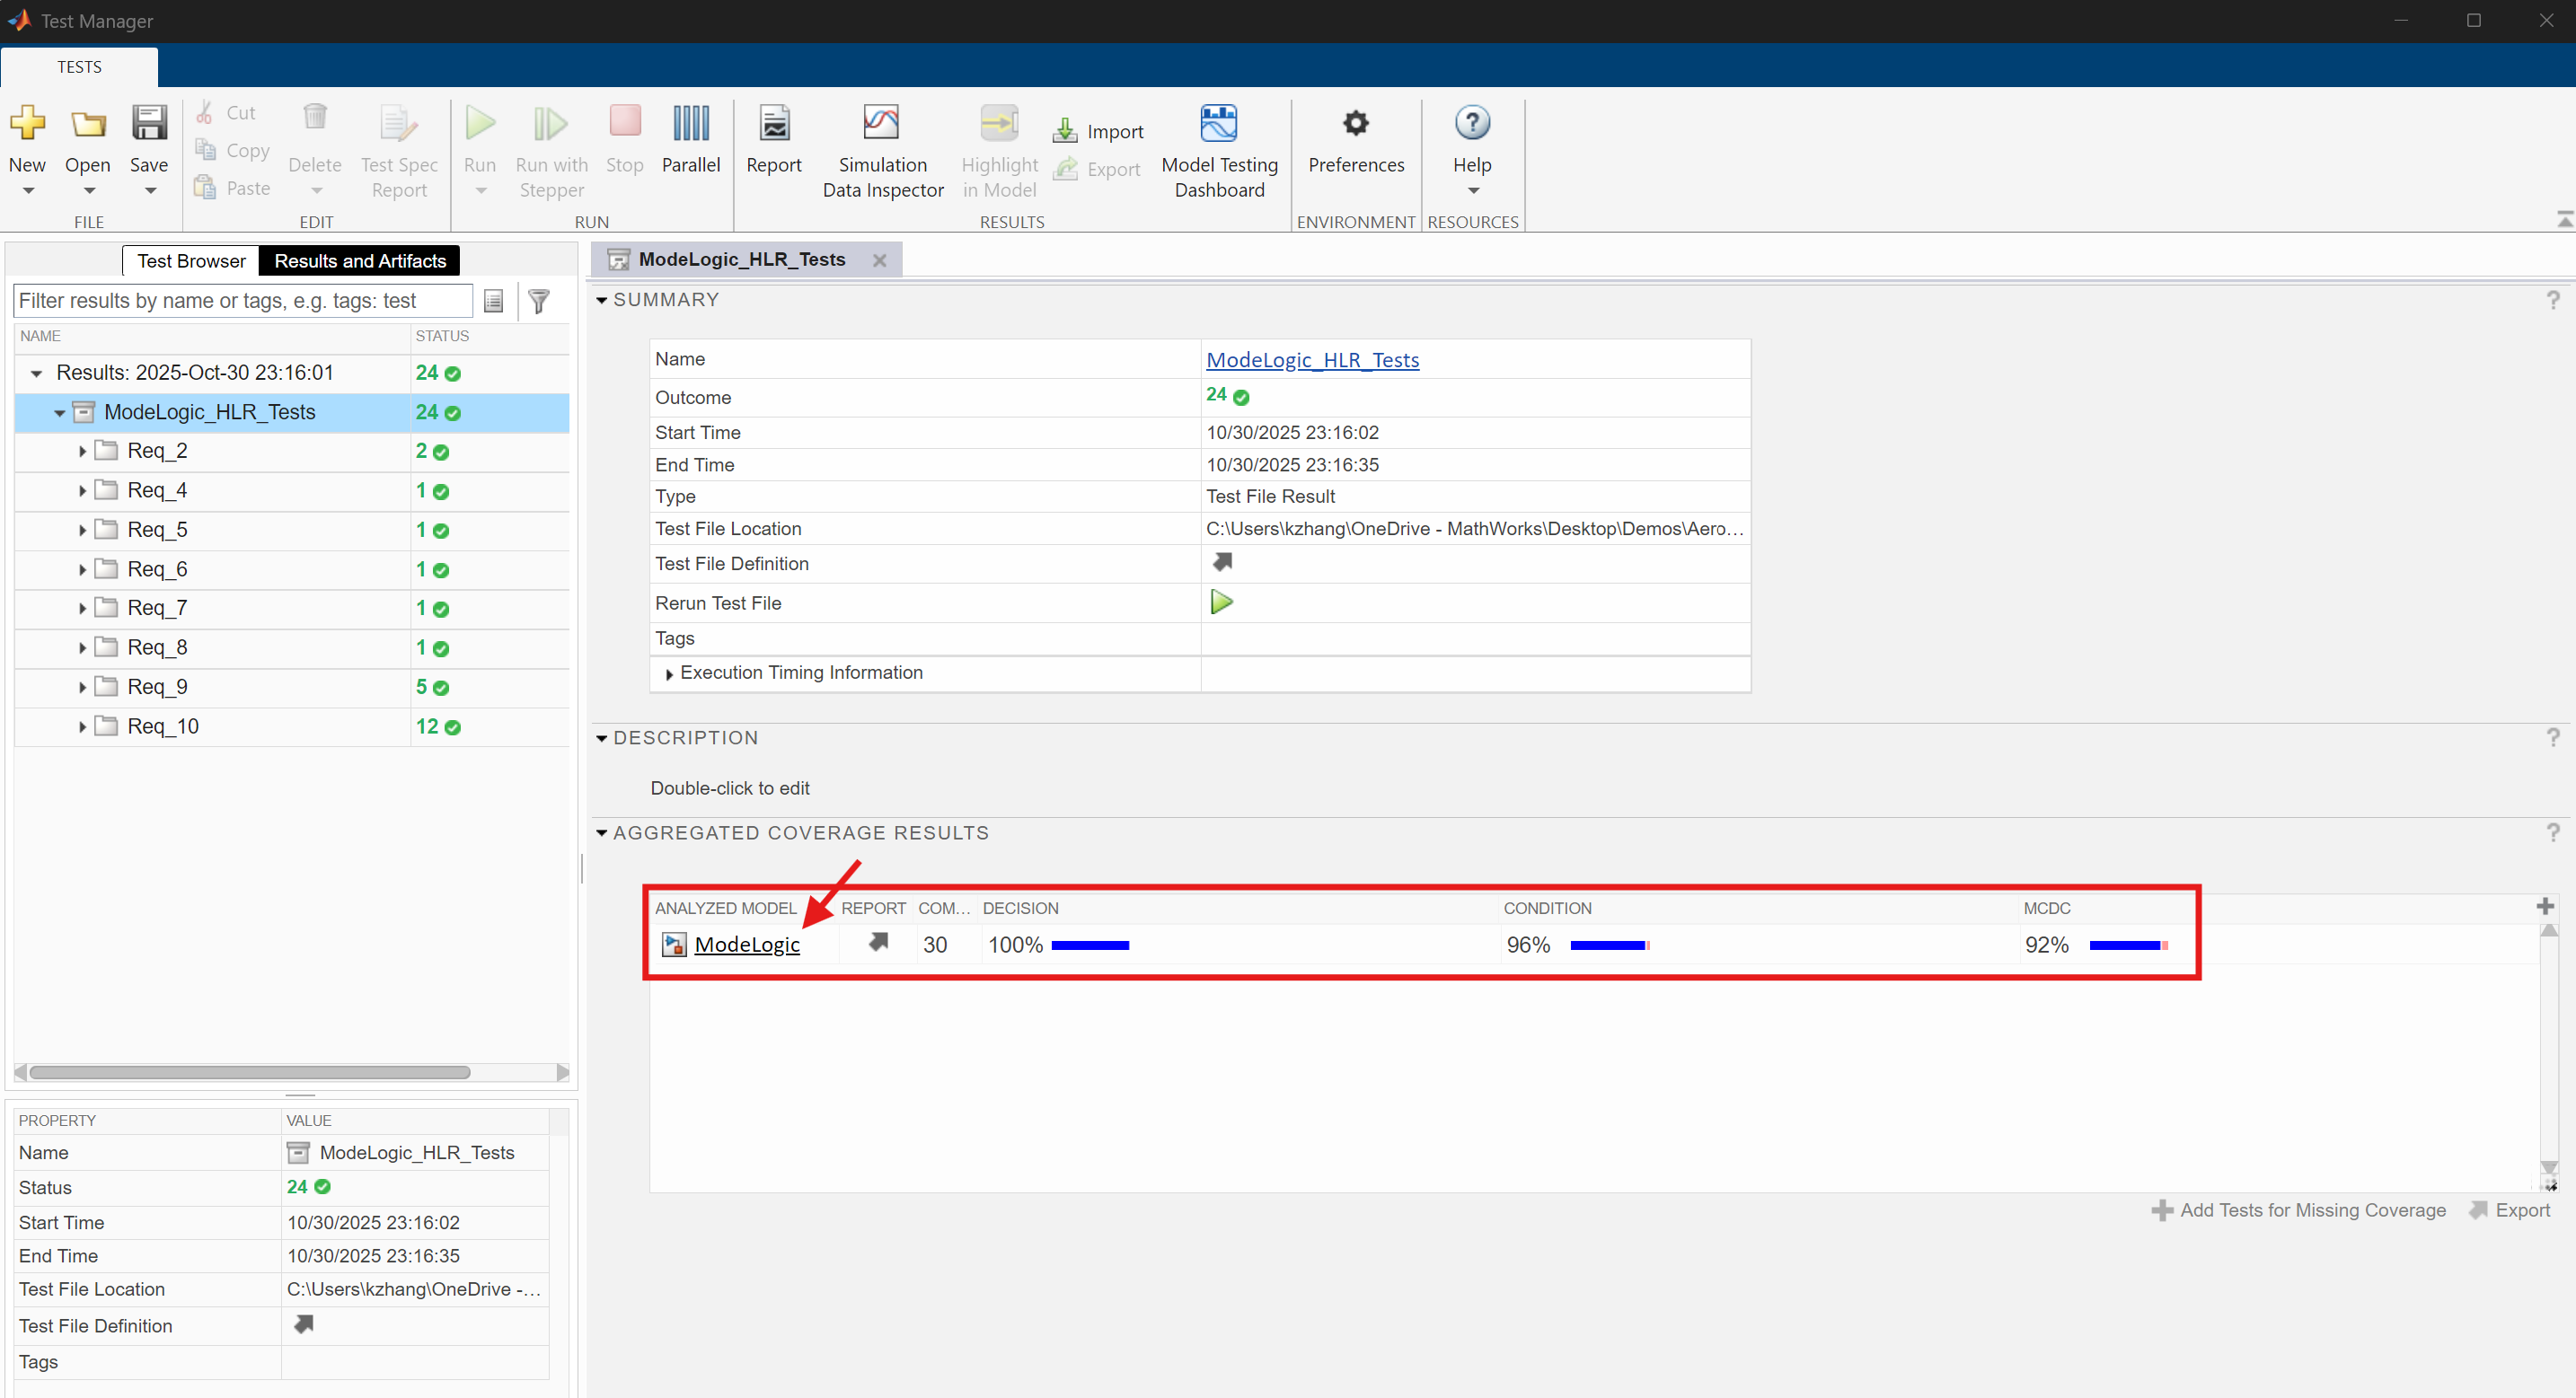

2) Click on **ModeLogic** link to open up the model. You can review coverage result both from the model and view the report generated on the right panel. 

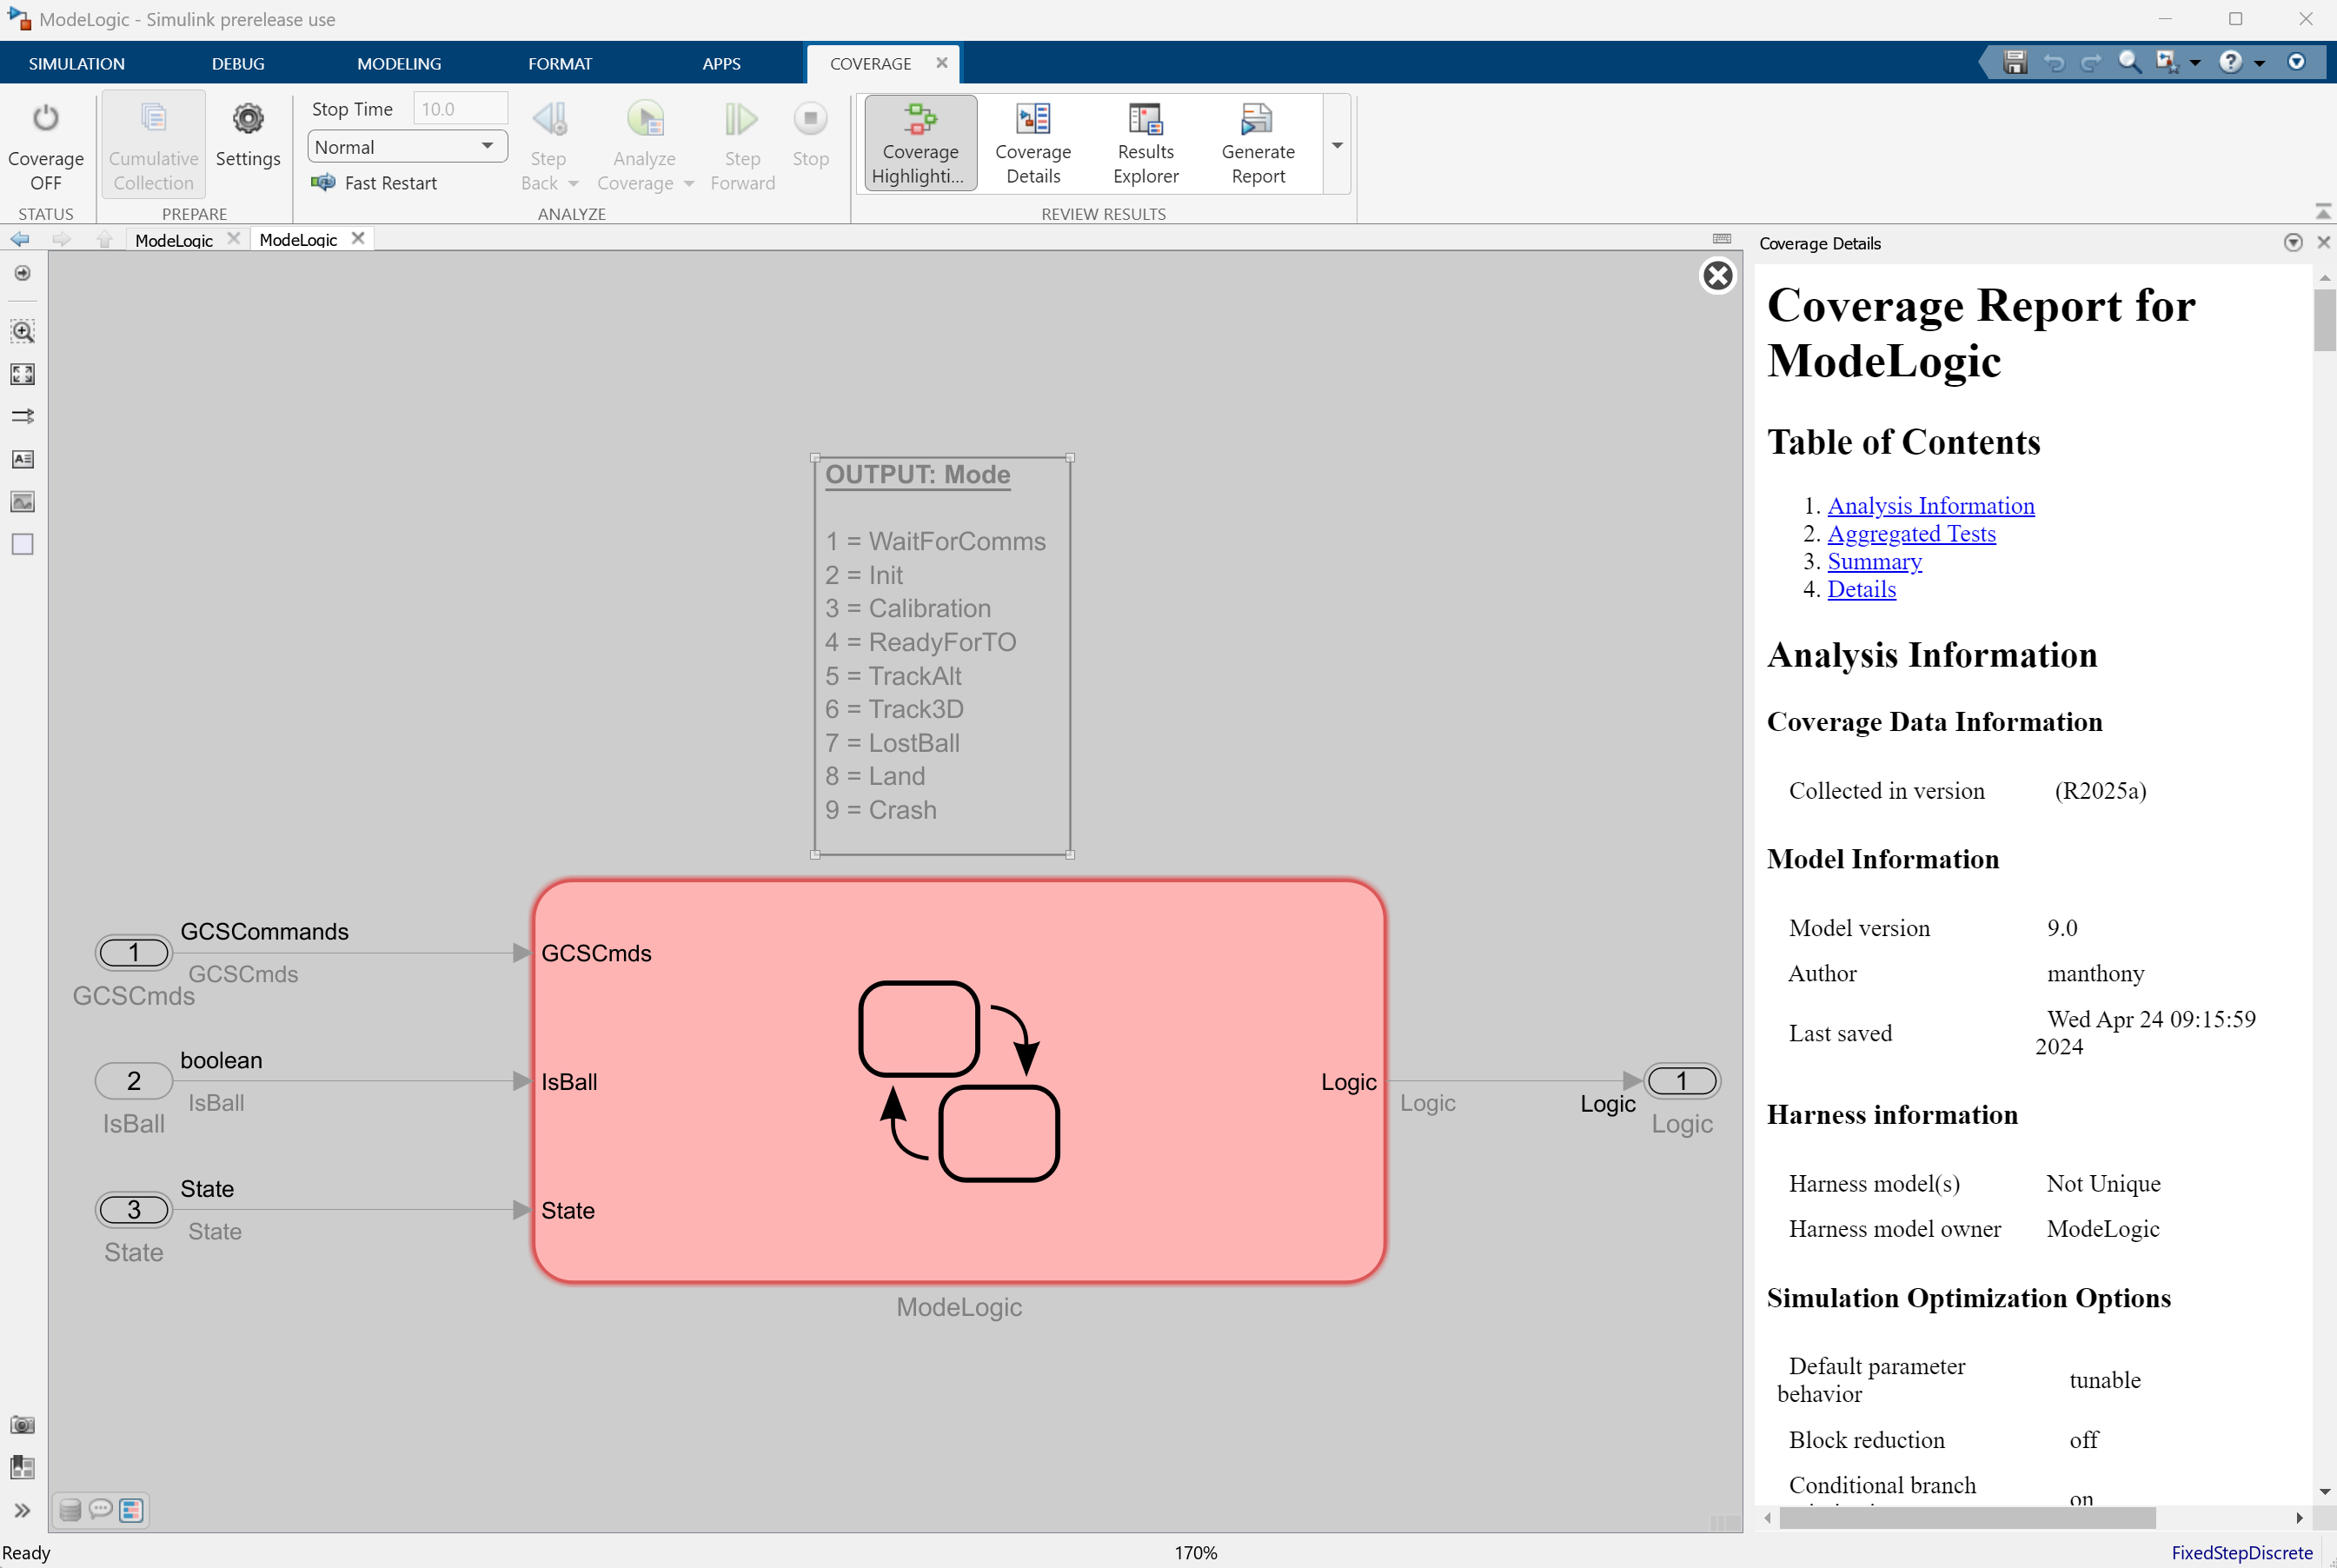 

3) The result shows that we do not currently have 100% test coverage. Click into the Stateflow chart, can you see what is missing?

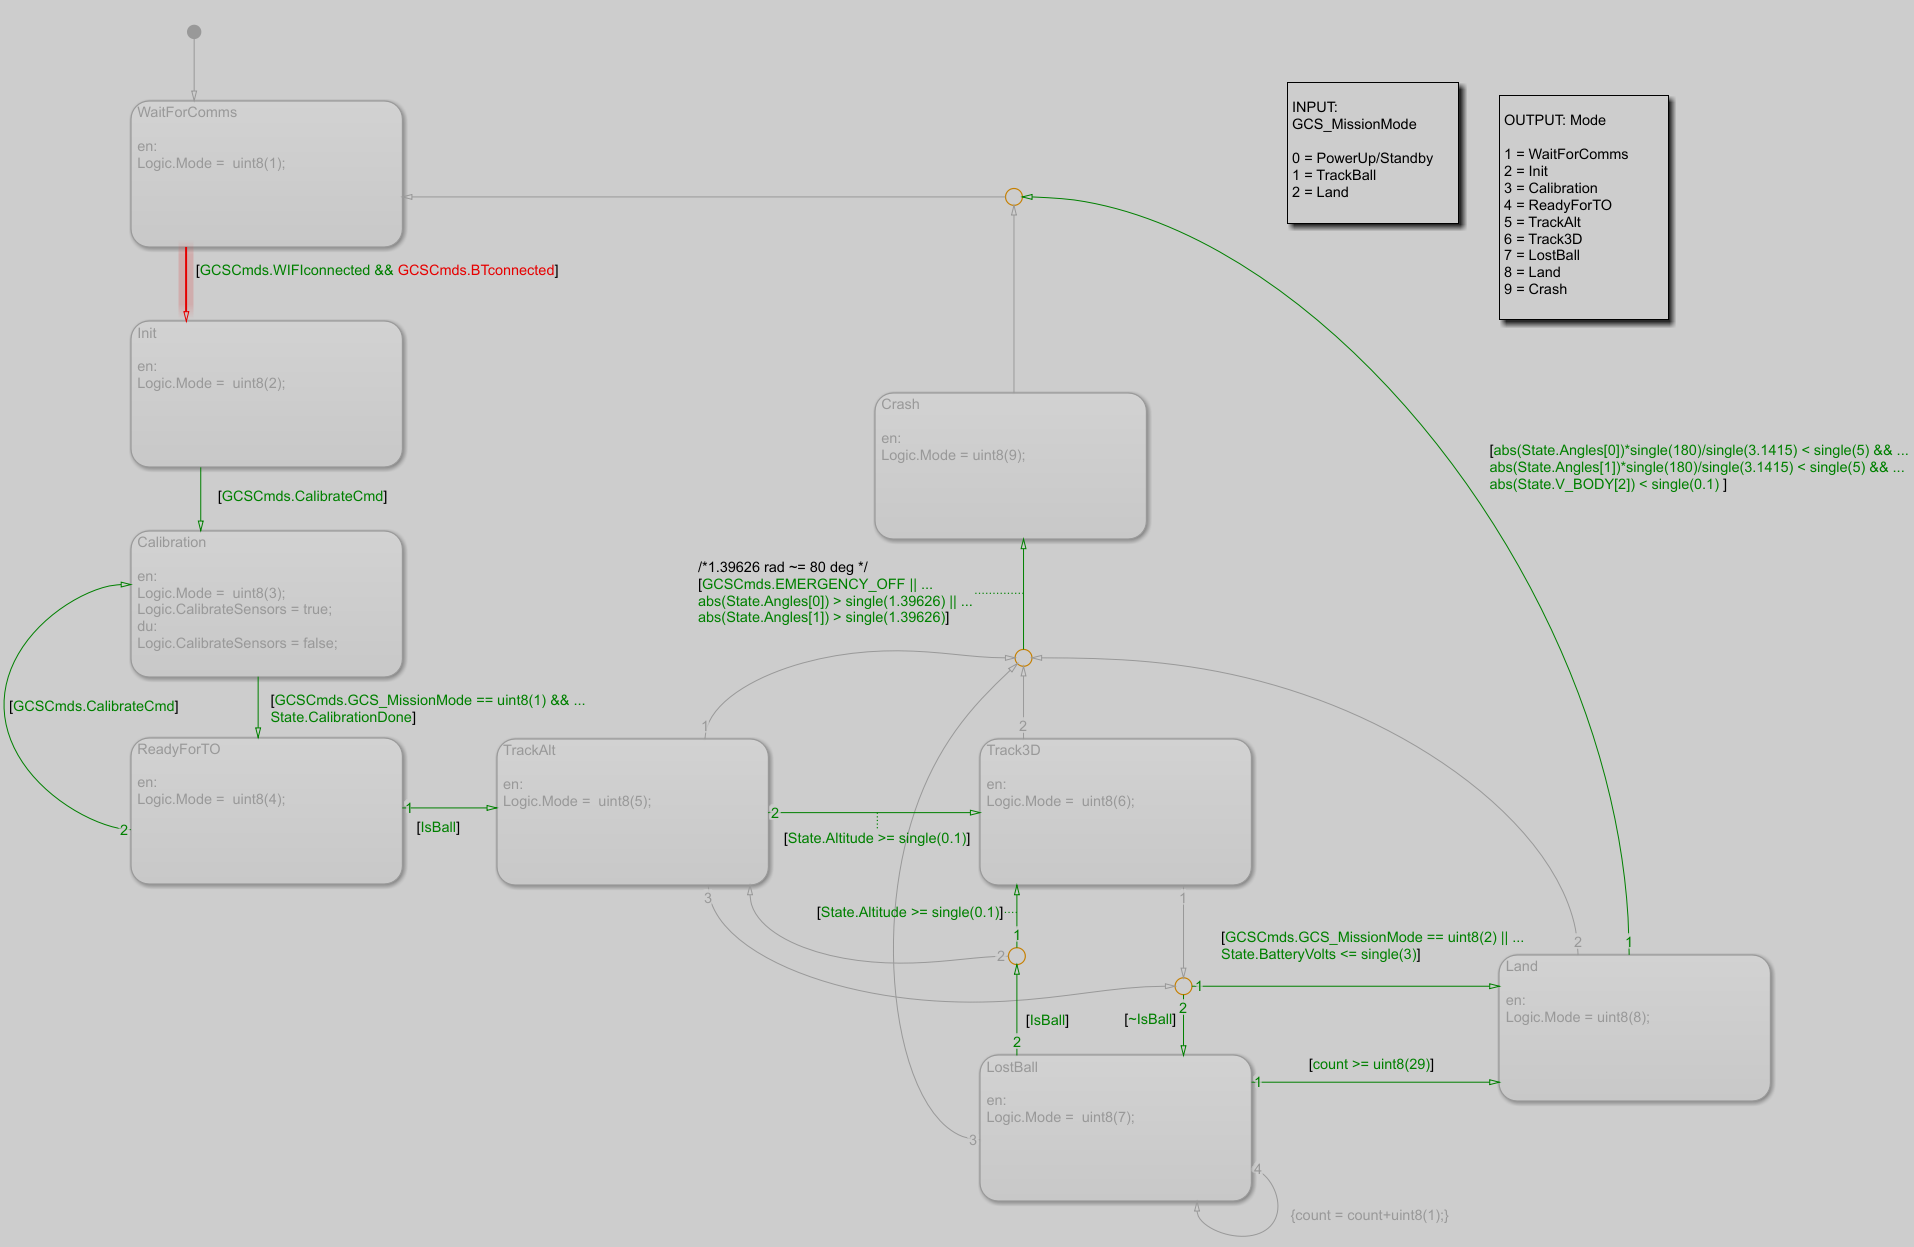  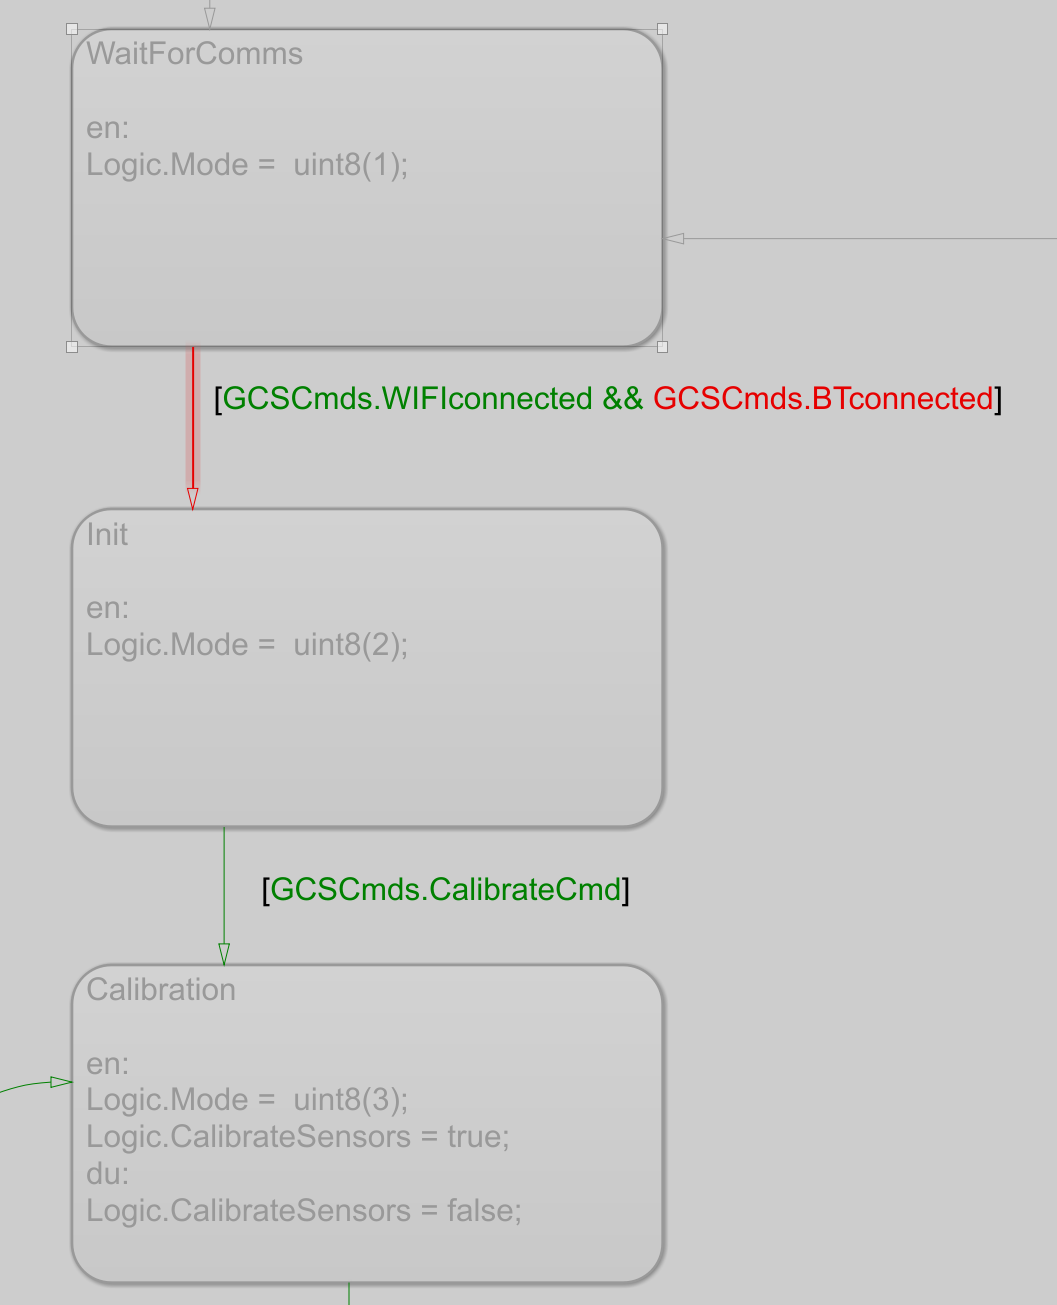

We can see that all of our test cases accounted for cases when both WiFi and Bluetooth connections are established, but we do not have a test case to account for scenarios when Bluetooth communication is not established, in which case we need to stay in Mode 1 and wait for both connections to establish.

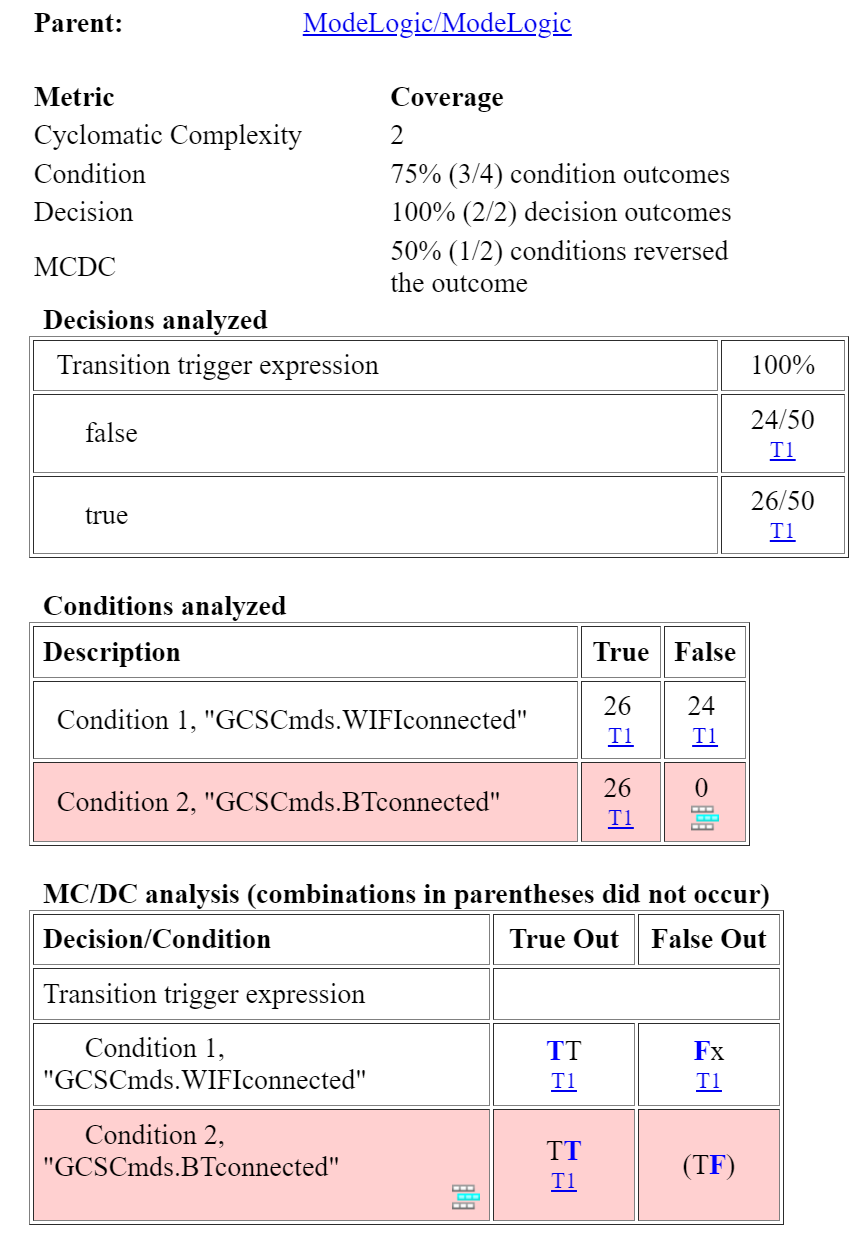

4) Now, let's add another test harness and test case to account for this missing test coverage. Following the same steps in Part 2, create a new test harness for the ModeLogic model called "HLR_03" and insert the following test sequence:

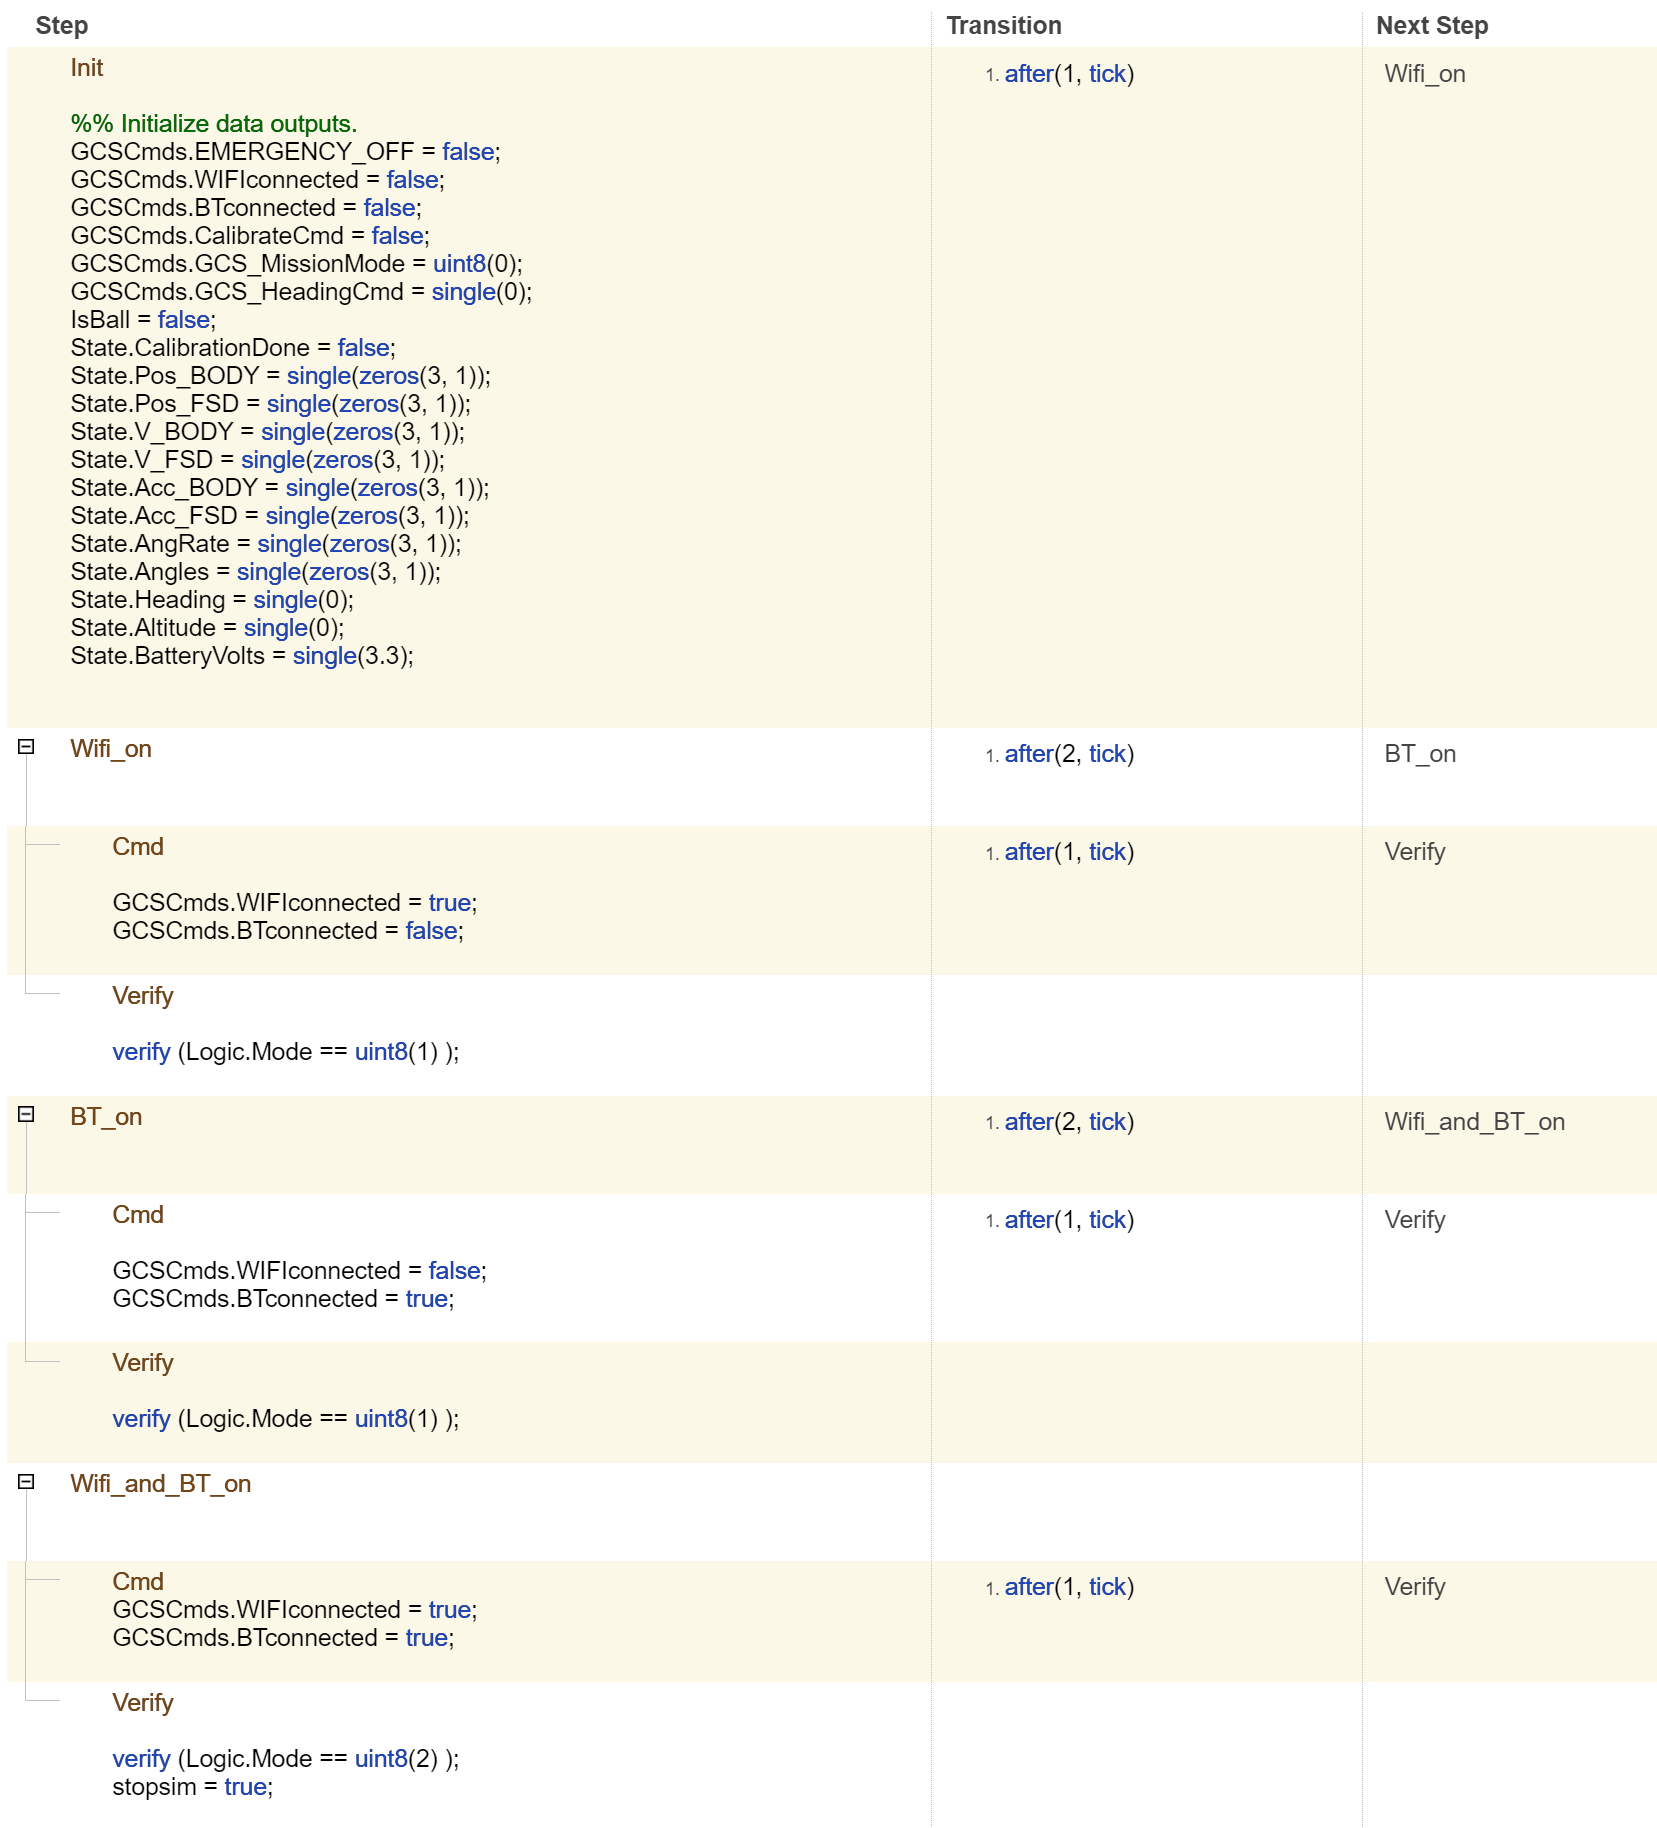     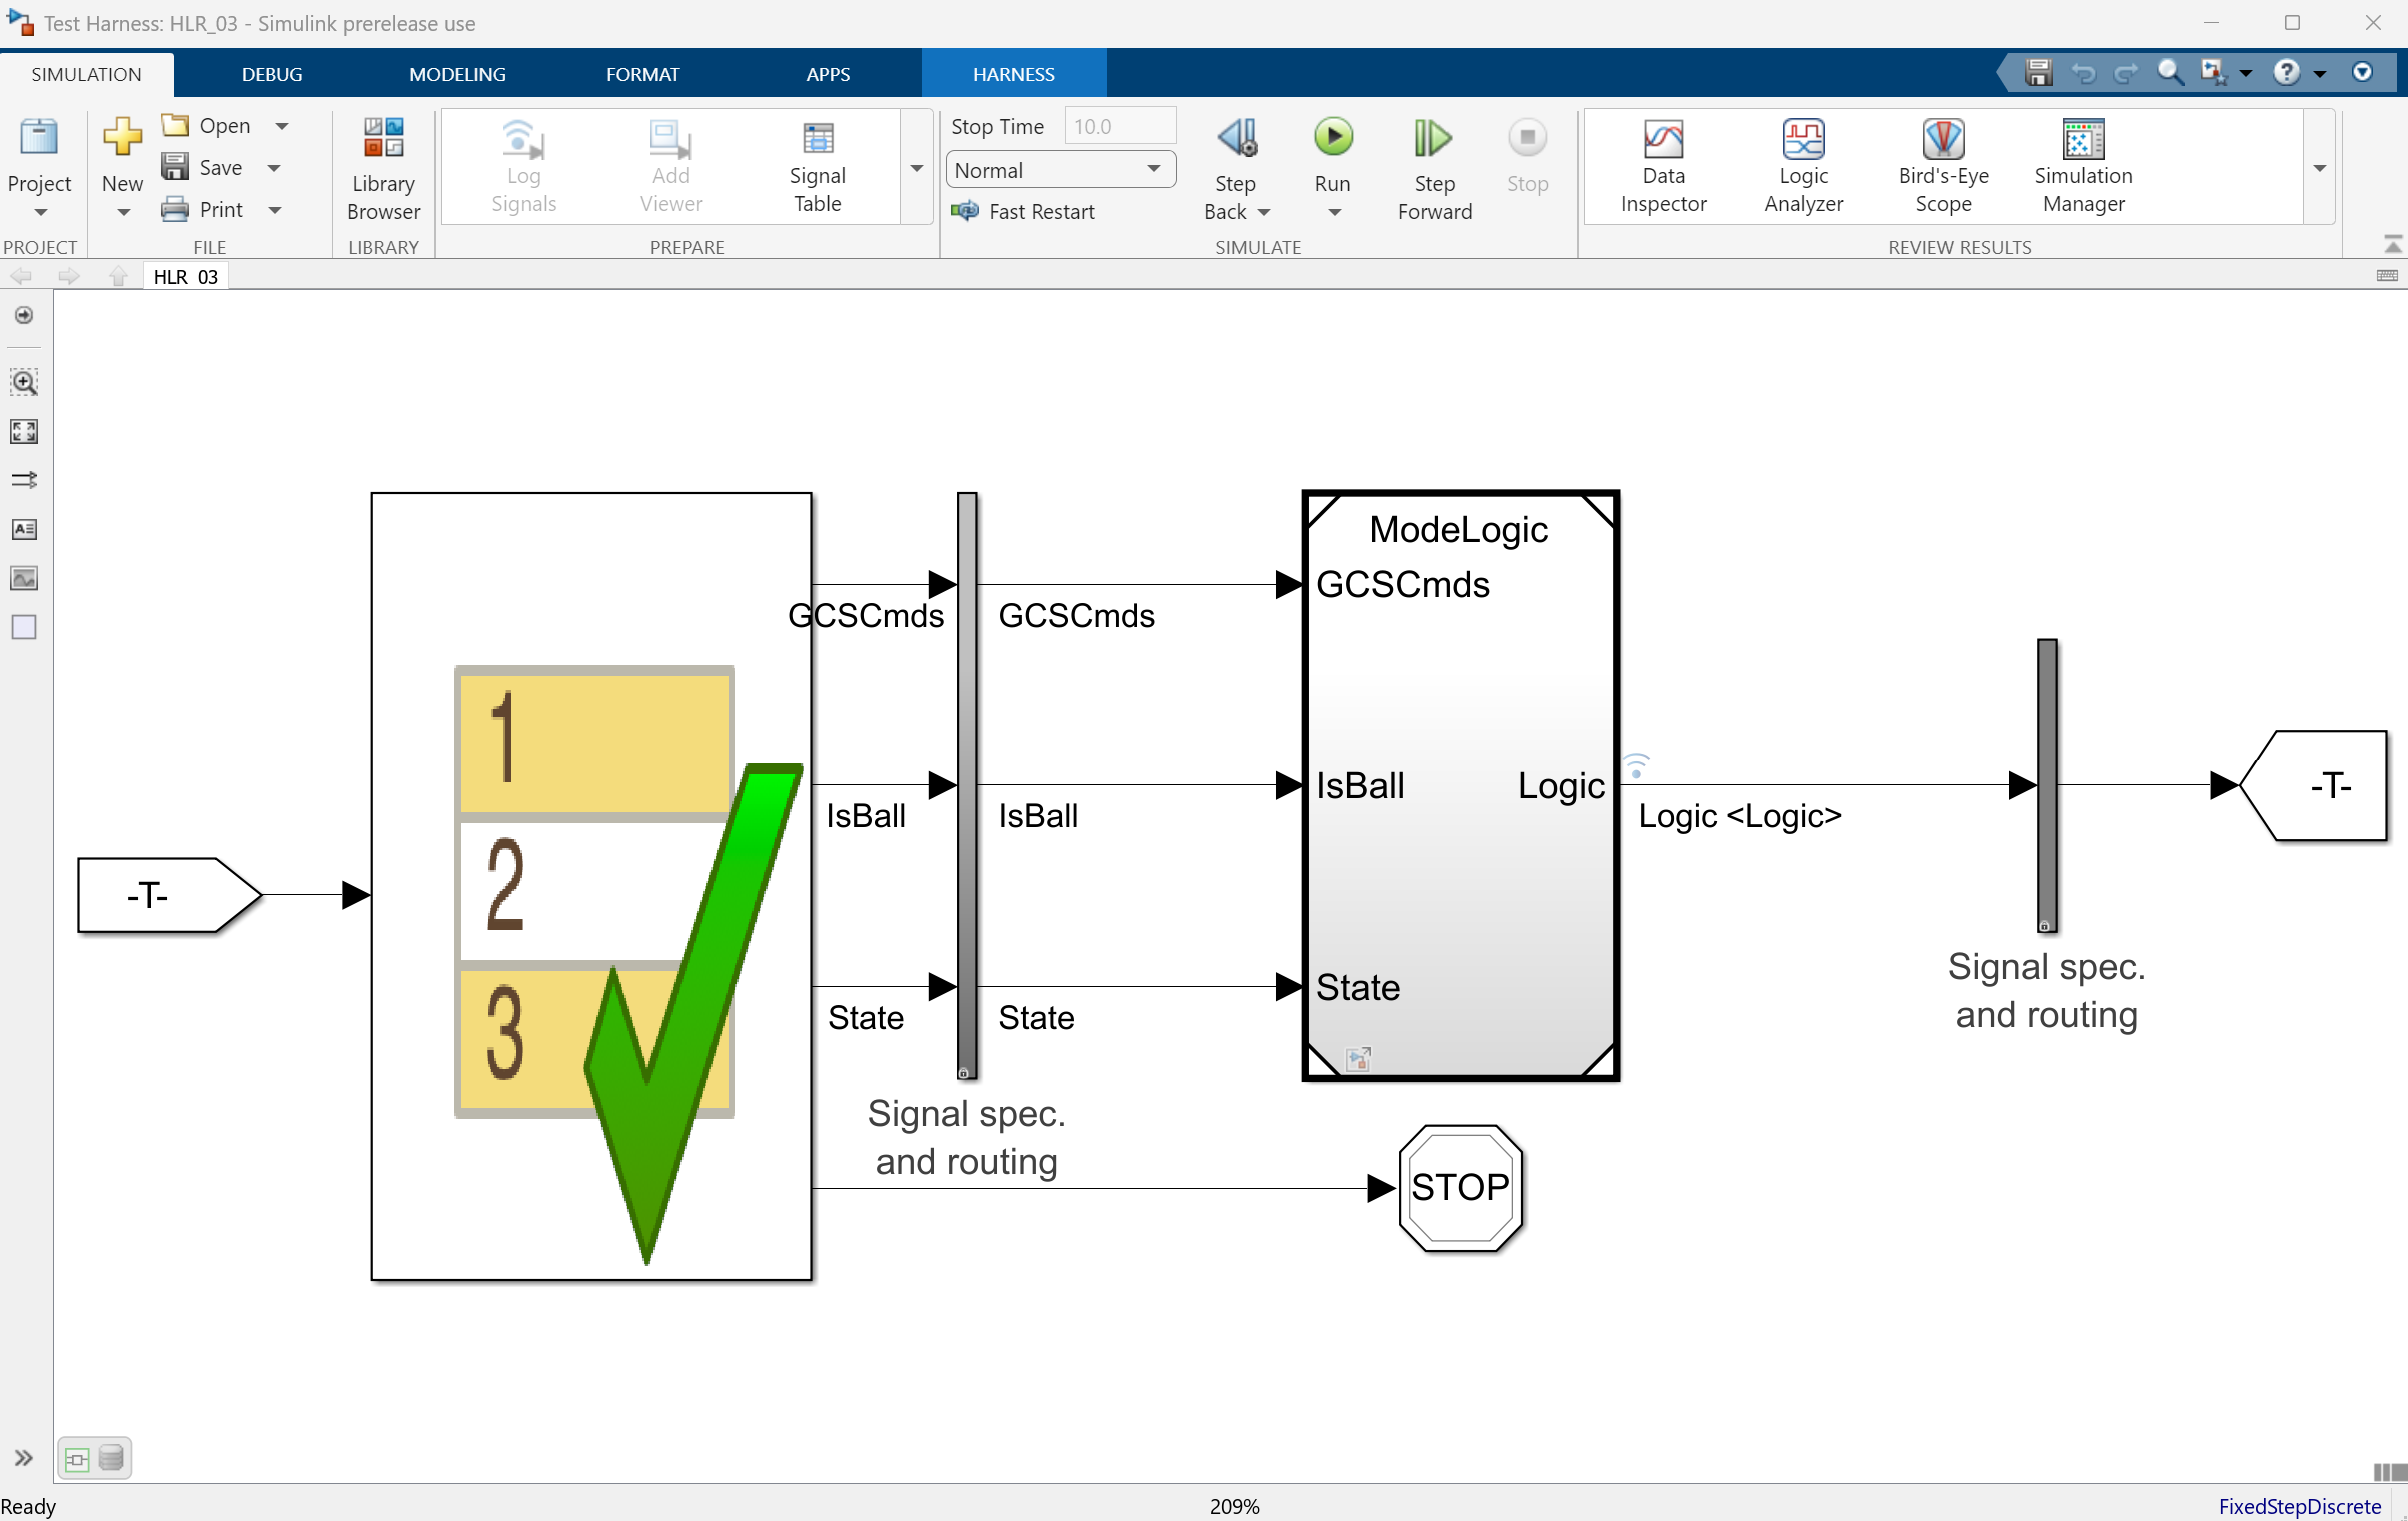

5) Save the test harness in the same folder as all other test cases: DO_03_Design/ModeLogic/test_cases/HLR.

6) Next, let's create a new test case with this test harness in ModeLogic_HLR_Tests suite:

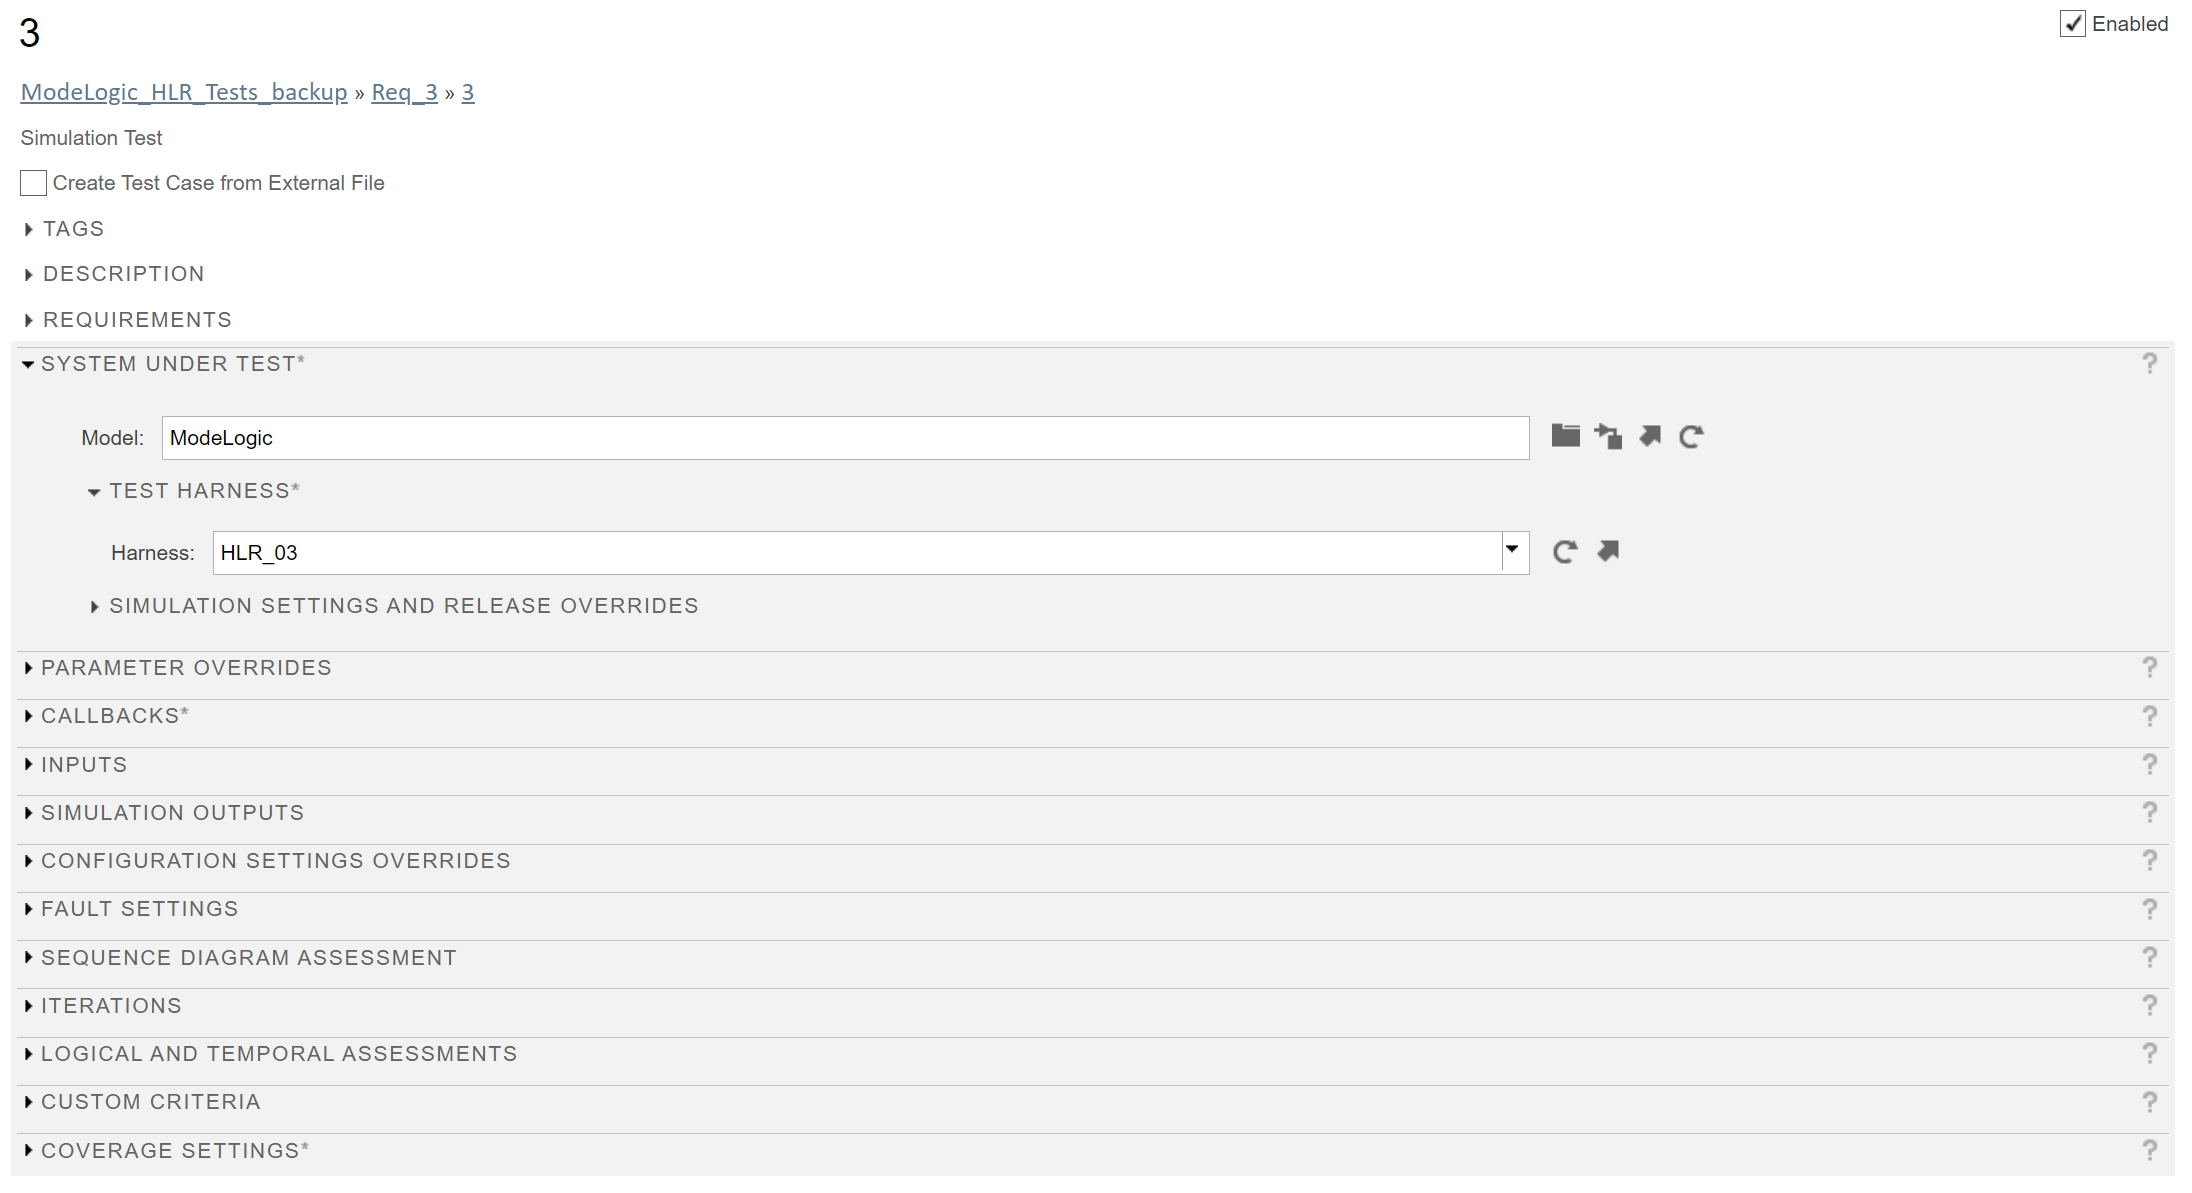

7) Save the test file and rerun the tests, now you should see 100% test coverage.

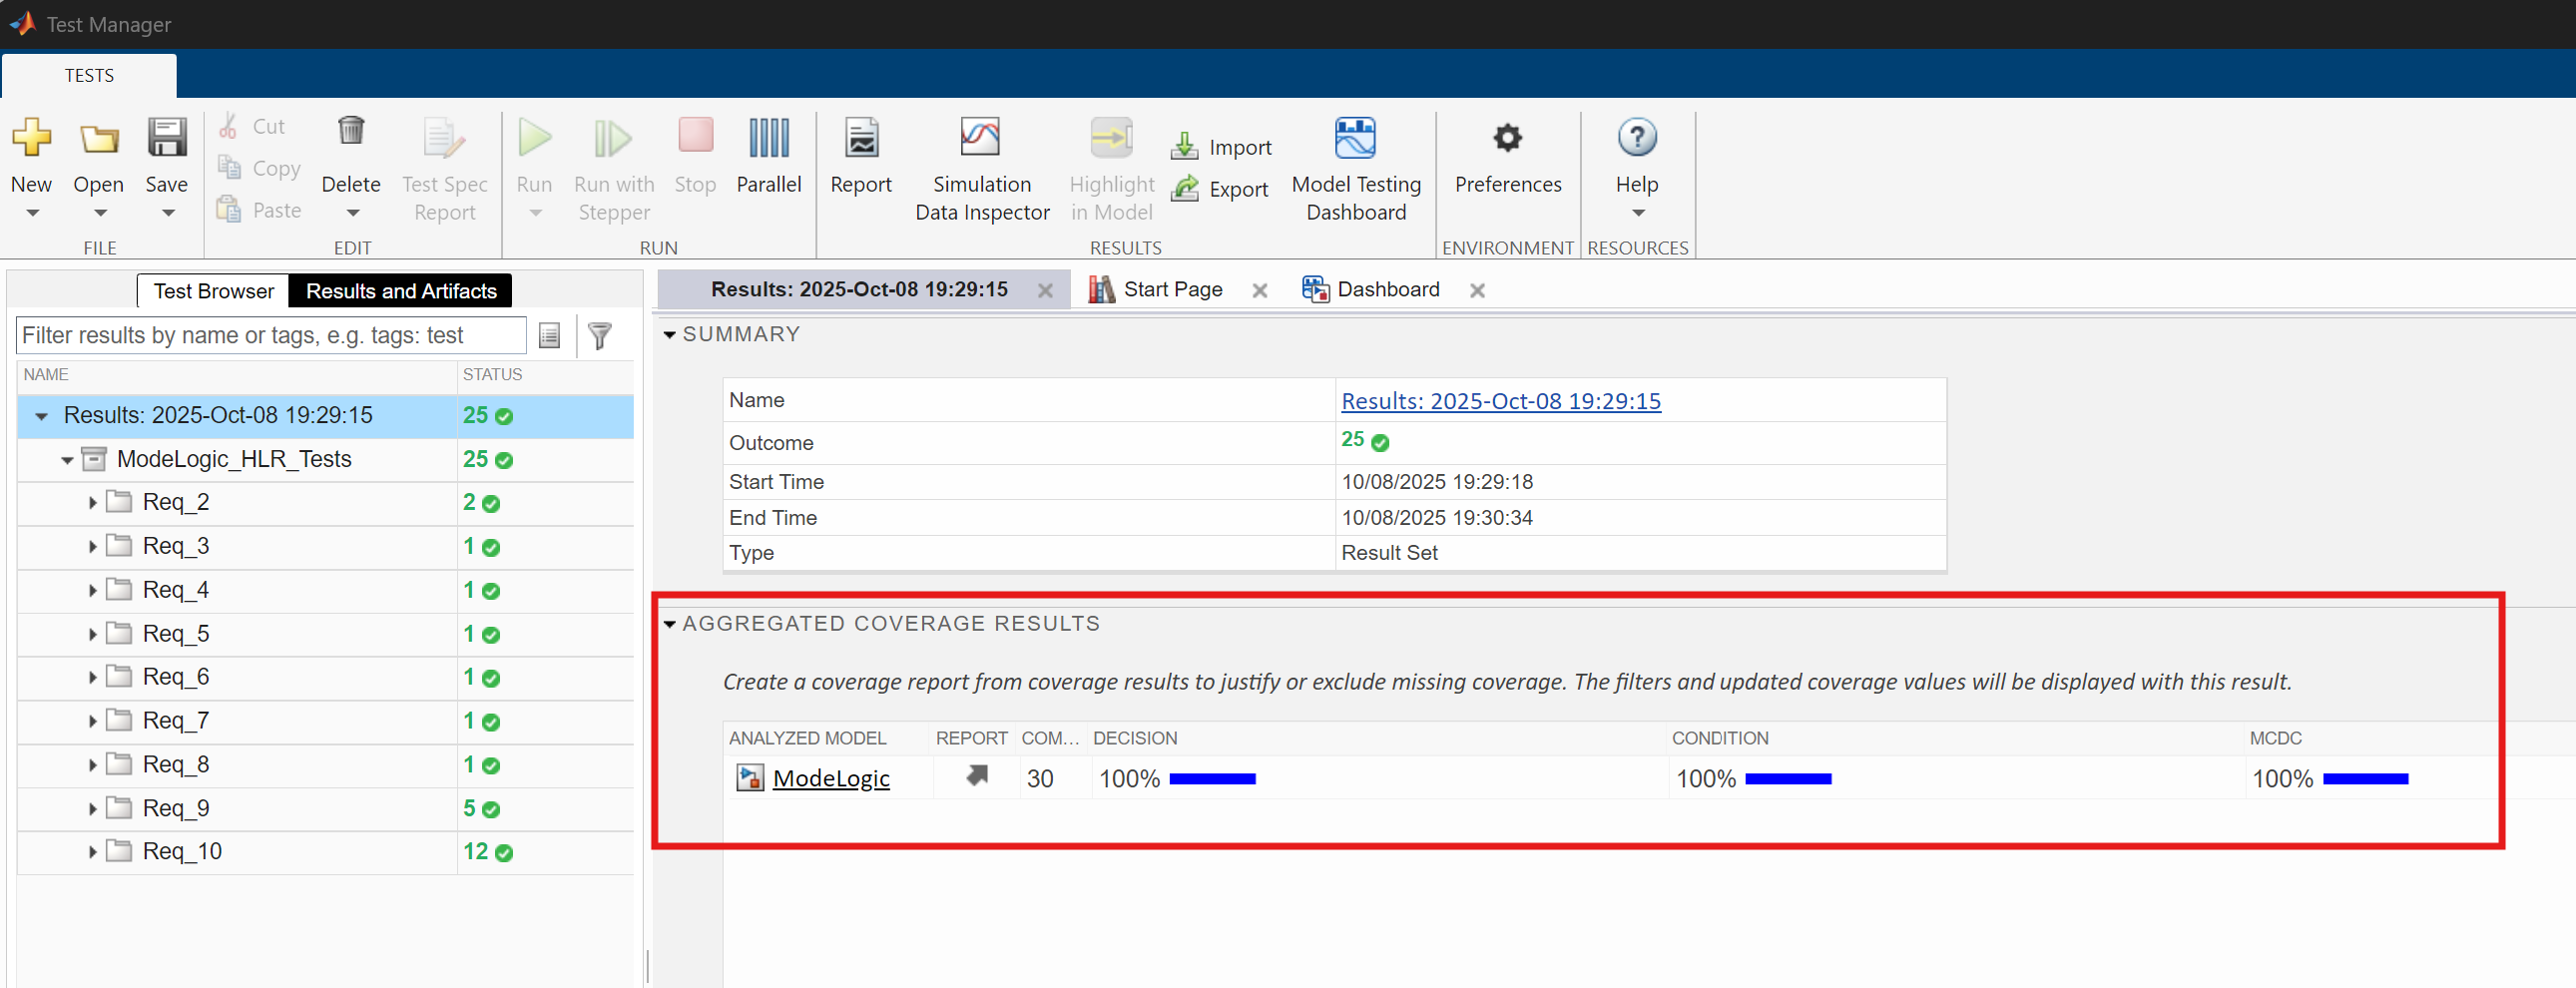

### **Bonus Task**

To which requirement should we link this new test case? 

Run the code below to find the Initialization-related requirements and display their Index and Description.

reqSet = slreq.open("HLR_ModeLogic.slreqx");
initRequirements = find(reqSet,"Type","Requirement","Description","~Initialization");
for req = initRequirements
    disp("Requirement " + string(req.Index) + ": " + getDescriptionAsText(req))
end

## Step 5: Scope Coverage Results to Requirements

DO-178C/DO-331 stipulates that coverage results be analyzed with respect to requirements. We can do this by "scoping" coverage results to requirements.

Scoping coverage results to requirements means that any coverage achieved for a given part of the design (a "coverage objective") should be achieved by a test case which shares the same requirement as the coverage objective. For example, if there is a requirement called "Requirement 1" which defines when to switch between Modes A and B, then Requirement 1 will be linked to the transition between Modes A and B in the design (e.g., Stateflow state chart). Let's say Test Case 1 verifies Requirement 1 and is therefore linked to Requirement 1. We should therefore expect to see Test Case 1 fully cover the transition between Modes A and B. If that is not the case, then any additional coverage achieved by other test cases is called "incidental" and should be filtered out for coverage analysis. Check out [**this video**](https://www.mathworks.com/videos/how-to-scope-model-coverage-to-requirements-based-tests-1585910927242.html) and [**the documentation**](https://www.mathworks.com/help/slcoverage/ug/assess-coverage-results-from-requirements-based-tests.html) explaining the concept to learn more.

We can scope coverage results to requirements *after* running tests by selecting "Scope coverage results to linked requirements" from the test file Results. 

This feature uses the traceability between the design, requirements, and test cases to filter out "incidental" coverage. Note again that scoping is done *after *running tests; we don't need to re-run them for this analysis.

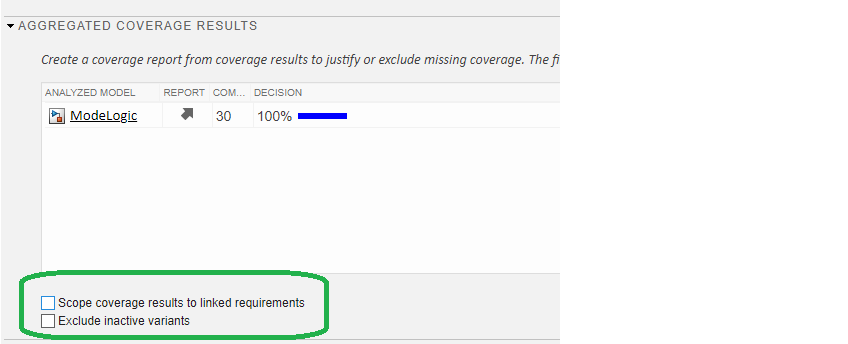

This will reduce the Decision coverage from 100% to 74%.

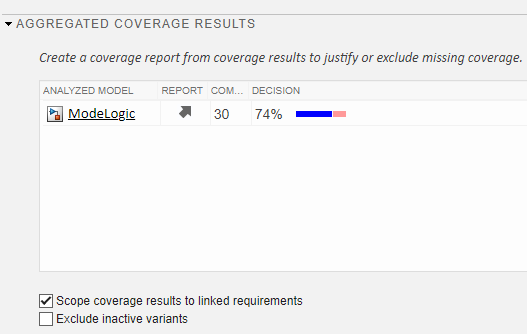

**Why did the Decision coverage drop?**

Let's find out by looking at the Coverage Report, which we can launch using the arrow icon under "REPORT" in AGGREGATED COVERAGE RESULTS.

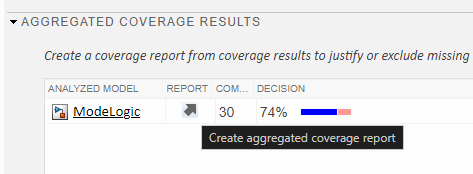

Note in the Coverage Options section in the Coverage Report header that scoping was enabled:

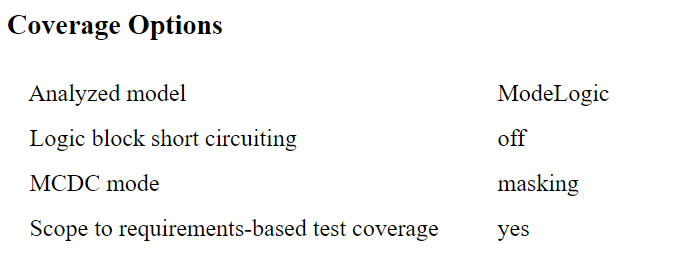

Scroll down to the Summary and click on "SF: ModeLogic"

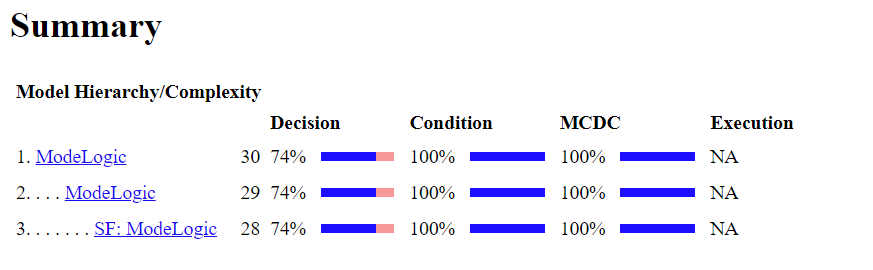

This will show the coverage results for the ModeLogic chart:

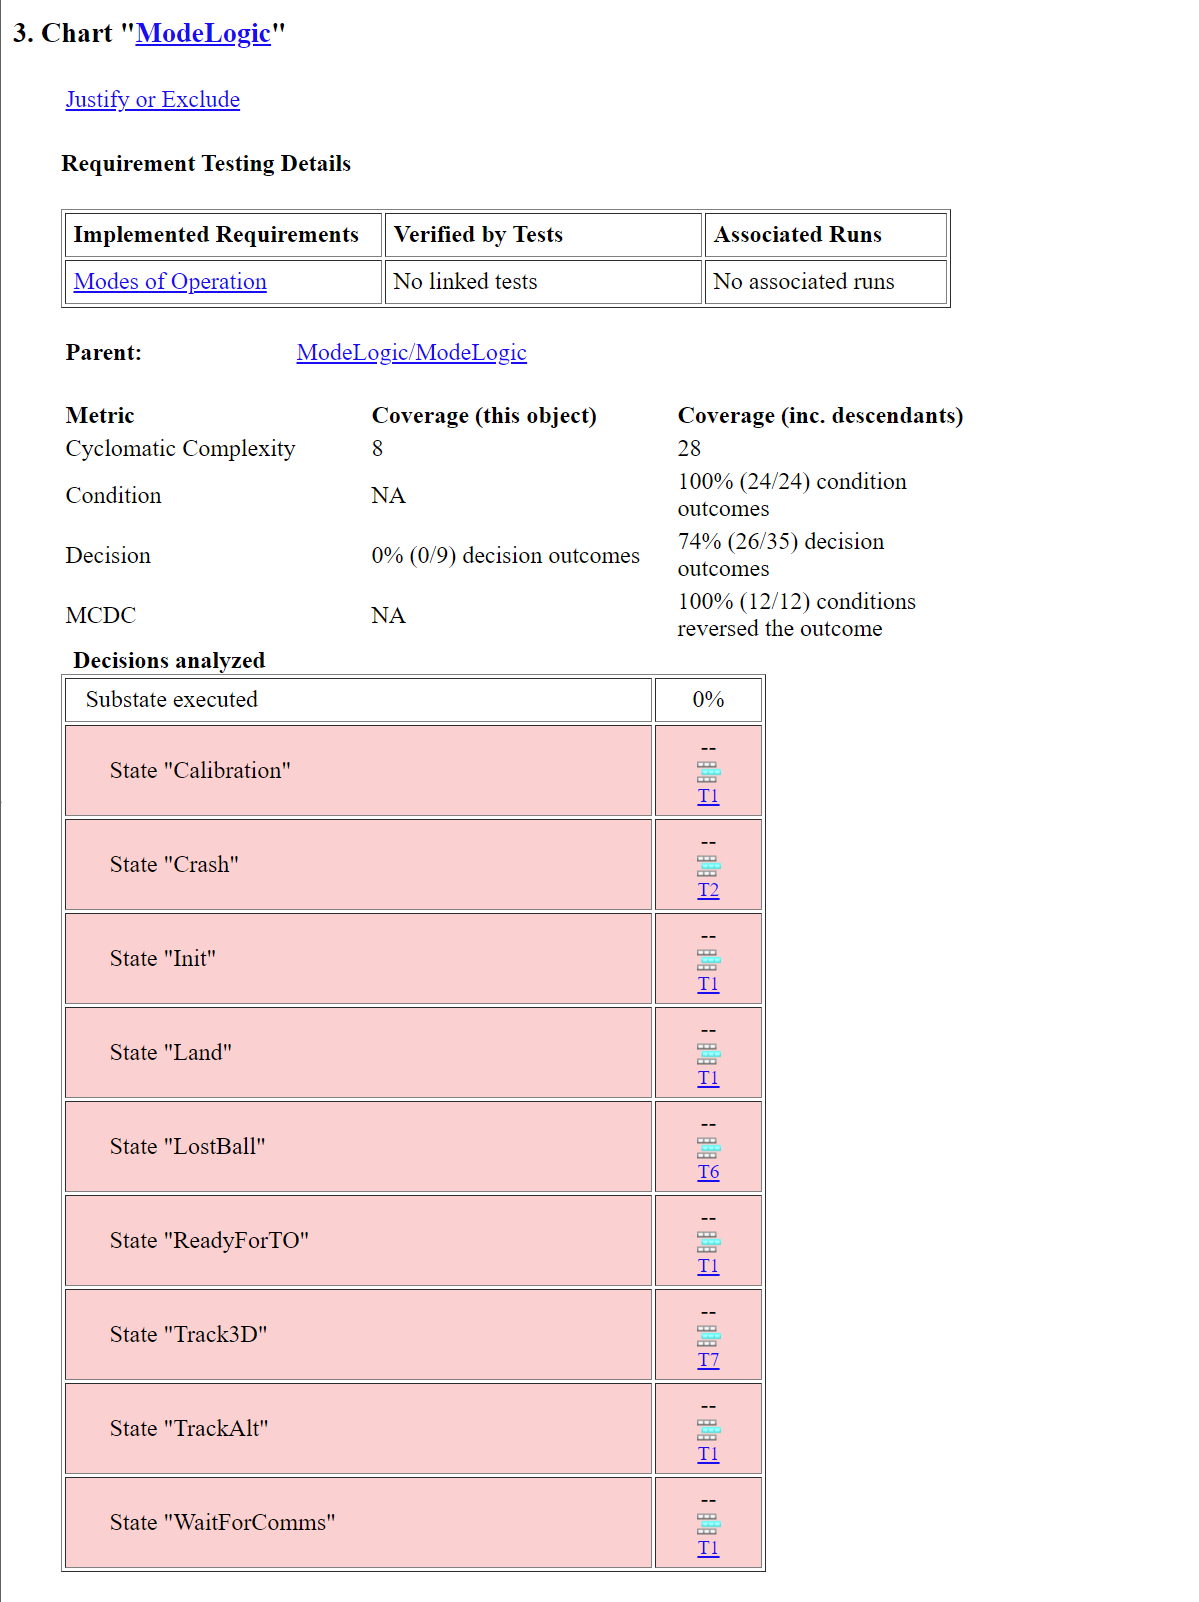

We can see that some test cases (e.g., T1, T2, etc.) were able to exercise those parts of the design ("substate executed"), but it looks like none of those test cases are traceable to the "Modes of Operation" requirement.

Let's focus on the "Requirements Testing Details".

We should expect to see something like this (using an example for another part of the design):

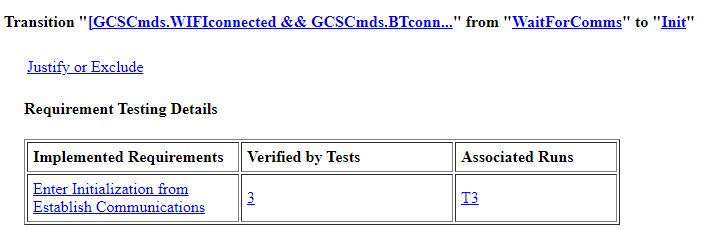

However, the ModeLogic Chart is missing linked tests and associated runs:

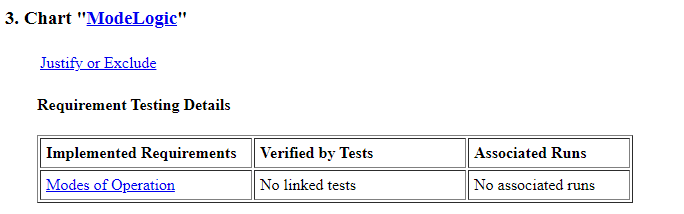

Click on the "Modes of Operation" hyperlink to navigate to that requirement.

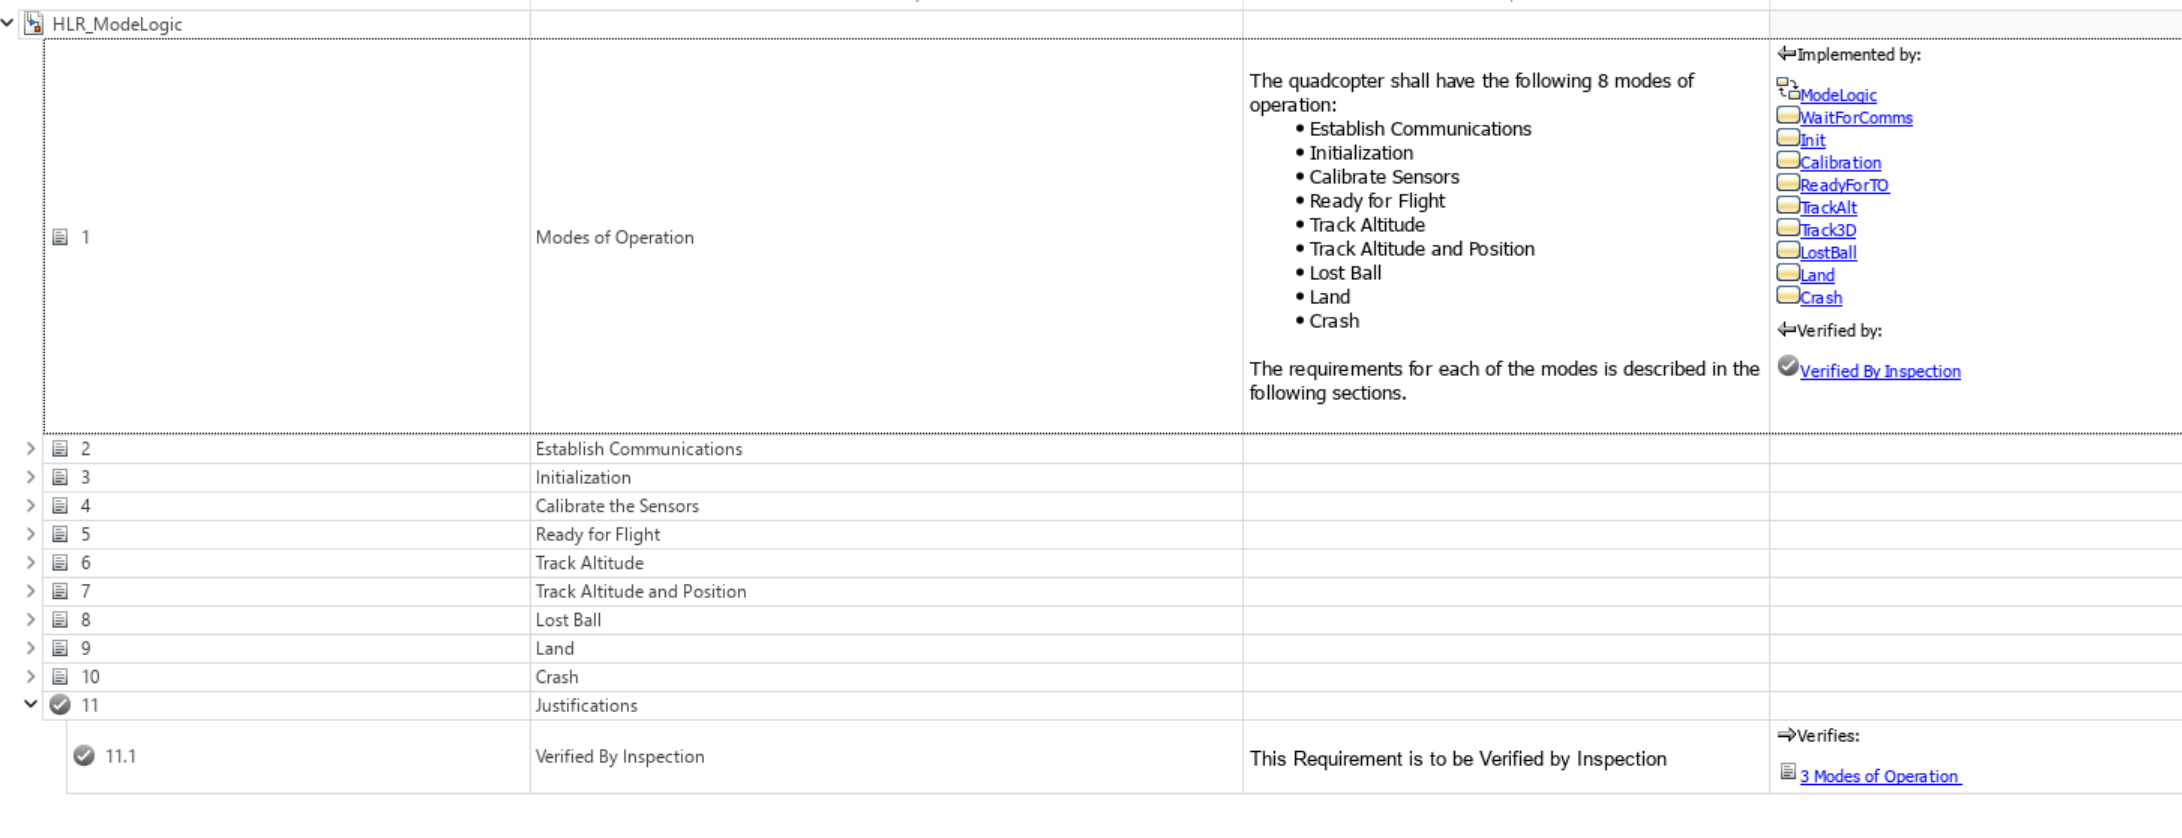

This requirement is documented as being verified "by inspection" instead of by simulation. The missing coverage is therefore justified.

**What if the requirement was meant to be verified by simulation?**

In many cases, missing "scoped" coverage can be addressed by filling in gaps in traceability via establishing requirements links (using, for instance, the interactive [Traceability Matrix](https://www.mathworks.com/help/slrequirements/ug/track-requirement-links-with-a-requirements-traceability-matrix.html) tool) or by augmenting test cases.

You can leverage data in the Coverage Report when performing this analysis.

Note that the "missing" coverage objectives were exercised by "unrelated" test cases (e.g., T1, T2):

We can click on the hyperlink for a given test run to learn more. For example, let's click on "T1", which corresponds to the first test run.

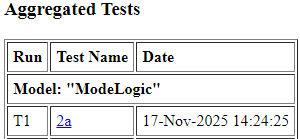

"T1" corresponds to Test Case "2a". We can open that test case in Simulink Test via the hyperlink.

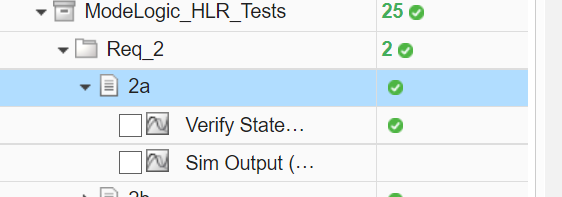

We can review this test case, and others, to understand how we could leverage it to exercise the missing "scoped" coverage, if appropriate.

# Part 4: DO Qualification Kit Overview

The [DO Qualification Kit (for DO-178 and DO-254)™](https://www.mathworks.com/products/do-178.html)  provides a set of tools and documentation to enable you to use and qualify Simulink® and Polyspace® verification tools for use on projects seeking compliance with DO-178, DO-278, DO-254 and related supplements (e.g., DO-331). The product includes tool qualification plans, tool operational requirements, test cases, and reference examples and templates. Tool qualification is enabled per guidance in DO-330. This example made use of a template folder structure similar to that provided in the DO Qualification Kit.

This example followed a recommended workflow when developing safety-critical systems. The DO Qualification Kit provides additional documentation to enable you to demonstrate compliance with DO standards. 

Tool qualification is an important consideration, which allows you to leverage the results of verification tools without manual review. MathWorks provides a means to qualify several verification tools, but it is up to the end user to qualify the tools used in your own environment. 

If you are planning on using Simulink and Polyspace verification tools on your projects, refer to the DO Qualification Kit documentation for guidance on how to qualify the tools. Make sure to consult the documentation such as the Tool Operational Requirements and Tool Qualification Plans for specific information on which features are "qualifiable" for each product supported in the DO Qualification Kit.